## Wing Design

cruise = AirCondition()

cruise =   AirCondition with properties:

      M: []
      V: []
      h: []
    rho: []
      T: []
      a: []
      P: []
     nu: []
     mu: []
     Re: []


cruise.M = 0.8;
cruise.h = convlength(39000, 'ft','m');

## 1.Design CL

CLdes = W0_Sref_cruise/(1/2*cruise.rho*cruise.V^2)

Unrecognized function or variable 'W0_Sref_cruise'.

## 2.Airfoil Selection

1.Choose a t/c ratio optimum for the cruise speed

2.Choose a CLopt (at L/D max or called drag-bucket) close to design CL

### Conclusion:

polarName = "xf-sc21010-il-1000000.csv";
shapeName = "sc21010.dat.txt";

## 3.Shape

1.Use MDO to get best geometry

    -Make sure it is applicable to double-tapered, swept wing

    -At each iteration inside MDO, calculate the optimum twist to give elliptical lift distribution

    -Use a validated wing weight estimation model

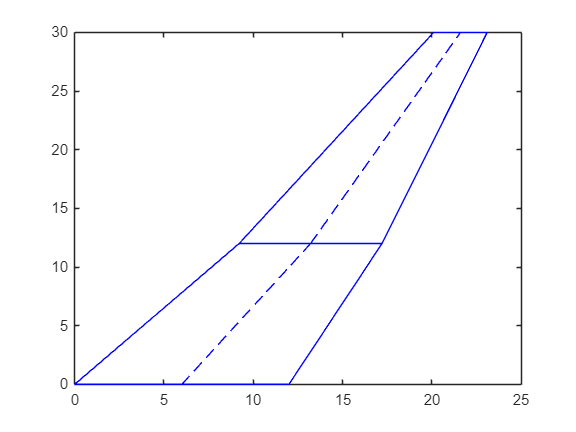

% Initial guess
x0 = [12, 8, 3, 30, 31*pi/180, 25*pi/180, 12];
% Design variables bounds
lb = x0.*0.5;
ub = x0.*2;
wing0 = x02wing(x0);

figure;
clf;
axis equal
wing0.plotWing()
hold on

% Optimization options
options = optimoptions('fmincon', 'Display', 'iter', 'Algorithm', 'sqp');
% Run the optimization
[x_opt, fval] = fmincon(@wingMDO, x0, [], [], [], [], lb, ub, @constraintFunction, options);

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010884"

    "CDW = "    "5.7474e-07"

    "CDi = "    "0.010168"

    "CDtotal = "    "0.021053"

    "CLclean = "    "0.73664"

L/D = 34.9899
    "Sref = "    "438"



W_f_0 = 0.2866

W_i =     0.9700    0.9850    0.7904    0.9900    0.9931    0.9853    0.9915    0.9954    0.9920


optIndex = 0.0351

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010884"

    "CDW = "    "5.7474e-07"

    "CDi = "    "0.010168"

    "CDtotal = "    "0.021053"

    "CLclean = "    "0.73664"

L/D = 34.9899
    "Sref = "    "438"



W_f_0 = 0.2866

W_i =     0.9700    0.9850    0.7904    0.9900    0.9931    0.9853    0.9915    0.9954    0.9920


optIndex = 0.0351

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010884"

    "CDW = "    "5.7474e-07"

    "CDi = "    "0.010168"

    "CDtotal = "    "0.021053"

    "CLclean = "    "0.73664"

L/D = 34.9899
    "Sref = "    "438"



W_f_0 = 0.2866

W_i =     0.9700    0.9850    0.7904    0.9900    0.9931    0.9853    0.9915    0.9954    0.9920


optIndex = 0.0351

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010884"

    "CDW = "    "5.7474e-07"

    "CDi = "    "0.010168"

    "CDtotal = "    "0.021053"

    "CLclean = "    "0.73664"

L/D = 34.9899
    "Sref = "    "438"



W_f_0 = 0.2866

W_i =     0.9700    0.9850    0.7904    0.9900    0.9931    0.9853    0.9915    0.9954    0.9920


optIndex = 0.0351

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010884"

    "CDW = "    "5.7474e-07"

    "CDi = "    "0.010168"

    "CDtotal = "    "0.021053"

    "CLclean = "    "0.73664"

L/D = 34.9899
    "Sref = "    "438"



W_f_0 = 0.2866

W_i =     0.9700    0.9850    0.7904    0.9900    0.9931    0.9853    0.9915    0.9954    0.9920


optIndex = 0.0351

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010884"

    "CDW = "    "5.7474e-07"

    "CDi = "    "0.010168"

    "CDtotal = "    "0.021053"

    "CLclean = "    "0.73664"

L/D = 34.9899
    "Sref = "    "438"



W_f_0 = 0.2866

W_i =     0.9700    0.9850    0.7904    0.9900    0.9931    0.9853    0.9915    0.9954    0.9920


optIndex = 0.0351

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010884"

    "CDW = "    "5.7474e-07"

    "CDi = "    "0.010168"

    "CDtotal = "    "0.021053"

    "CLclean = "    "0.73664"

L/D = 34.9899
    "Sref = "    "438"



W_f_0 = 0.2866

W_i =     0.9700    0.9850    0.7904    0.9900    0.9931    0.9853    0.9915    0.9954    0.9920


optIndex = 0.0351

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010884"

    "CDW = "    "5.7474e-07"

    "CDi = "    "0.010168"

    "CDtotal = "    "0.021053"

    "CLclean = "    "0.73664"

L/D = 34.9899
    "Sref = "    "438"



W_f_0 = 0.2866

W_i =     0.9700    0.9850    0.7904    0.9900    0.9931    0.9853    0.9915    0.9954    0.9920


optIndex = 0.0351

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010884"

    "CDW = "    "5.7474e-07"

    "CDi = "    "0.010168"

    "CDtotal = "    "0.021053"

    "CLclean = "    "0.73664"

L/D = 34.9899
    "Sref = "    "438"



W_f_0 = 0.2866

W_i =     0.9700    0.9850    0.7904    0.9900    0.9931    0.9853    0.9915    0.9954    0.9920


optIndex = 0.0351

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010884"

    "CDW = "    "5.7474e-07"

    "CDi = "    "0.010168"

    "CDtotal = "    "0.021053"

    "CLclean = "    "0.73664"

L/D = 34.9899
    "Sref = "    "438"



W_f_0 = 0.2866

W_i =     0.9700    0.9850    0.7904    0.9900    0.9931    0.9853    0.9915    0.9954    0.9920


optIndex = 0.0351

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010884"

    "CDW = "    "5.7474e-07"

    "CDi = "    "0.010168"

    "CDtotal = "    "0.021053"

    "CLclean = "    "0.73664"

L/D = 34.9899
    "Sref = "    "438"



W_f_0 = 0.2866

W_i =     0.9700    0.9850    0.7904    0.9900    0.9931    0.9853    0.9915    0.9954    0.9920


optIndex = 0.0351

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010884"

    "CDW = "    "5.7474e-07"

    "CDi = "    "0.010168"

    "CDtotal = "    "0.021053"

    "CLclean = "    "0.73664"

L/D = 34.9899
    "Sref = "    "438"



W_f_0 = 0.2866

W_i =     0.9700    0.9850    0.7904    0.9900    0.9931    0.9853    0.9915    0.9954    0.9920


optIndex = 0.0351

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010884"

    "CDW = "    "5.7474e-07"

    "CDi = "    "0.010168"

    "CDtotal = "    "0.021053"

    "CLclean = "    "0.73664"

L/D = 34.9899
    "Sref = "    "438"



W_f_0 = 0.2866

W_i =     0.9700    0.9850    0.7904    0.9900    0.9931    0.9853    0.9915    0.9954    0.9920


optIndex = 0.0351

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010884"

    "CDW = "    "5.7474e-07"

    "CDi = "    "0.010168"

    "CDtotal = "    "0.021053"

    "CLclean = "    "0.73664"

L/D = 34.9899
    "Sref = "    "438"



W_f_0 = 0.2866

W_i =     0.9700    0.9850    0.7904    0.9900    0.9931    0.9853    0.9915    0.9954    0.9920


optIndex = 0.0351

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010884"

    "CDW = "    "5.7474e-07"

    "CDi = "    "0.010168"

    "CDtotal = "    "0.021053"

    "CLclean = "    "0.73664"

L/D = 34.9899
    "Sref = "    "438"



W_f_0 = 0.2866

W_i =     0.9700    0.9850    0.7904    0.9900    0.9931    0.9853    0.9915    0.9954    0.9920


optIndex = 0.0351

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010884"

    "CDW = "    "5.7474e-07"

    "CDi = "    "0.010168"

    "CDtotal = "    "0.021053"

    "CLclean = "    "0.73664"

L/D = 34.9899
    "Sref = "    "438"



W_f_0 = 0.2866

W_i =     0.9700    0.9850    0.7904    0.9900    0.9931    0.9853    0.9915    0.9954    0.9920


optIndex = 0.0351

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           8    3.506411e-02     7.720e+01     1.000e+00     0.000e+00     1.177e-02  
Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010183"

    "CDW = "    "1.2176e-06"

    "CDi = "    "0.0098218"

    "CDtotal = "    "0.020006"

    "CLclean = "    "0.74184"

L/D = 37.0813
    "Sref = "    "516.3389"



W_f_0 = 0.2760

W_i =     0.9700    0.9850    0.8009    0.9900    0.9931    0.9862    0.9919    0.9954    0.9920


optIndex = 0.0304

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010183"

    "CDW = "    "1.2176e-06"

    "CDi = "    "0.0098218"

    "CDtotal = "    "0.020006"

    "CLclean = "    "0.74184"

L/D = 37.0813
    "Sref = "    "516.3389"



W_f_0 = 0.2760

W_i =     0.9700    0.9850    0.8009    0.9900    0.9931    0.9862    0.9919    0.9954    0.9920


optIndex = 0.0304

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010183"

    "CDW = "    "1.2176e-06"

    "CDi = "    "0.0098218"

    "CDtotal = "    "0.020006"

    "CLclean = "    "0.74184"

L/D = 37.0813
    "Sref = "    "516.3389"



W_f_0 = 0.2760

W_i =     0.9700    0.9850    0.8009    0.9900    0.9931    0.9862    0.9919    0.9954    0.9920


optIndex = 0.0304

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010183"

    "CDW = "    "1.2176e-06"

    "CDi = "    "0.0098218"

    "CDtotal = "    "0.020006"

    "CLclean = "    "0.74184"

L/D = 37.0813
    "Sref = "    "516.3389"



W_f_0 = 0.2760

W_i =     0.9700    0.9850    0.8009    0.9900    0.9931    0.9862    0.9919    0.9954    0.9920


optIndex = 0.0304

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010183"

    "CDW = "    "1.2176e-06"

    "CDi = "    "0.0098218"

    "CDtotal = "    "0.020006"

    "CLclean = "    "0.74184"

L/D = 37.0813
    "Sref = "    "516.3389"



W_f_0 = 0.2760

W_i =     0.9700    0.9850    0.8009    0.9900    0.9931    0.9862    0.9919    0.9954    0.9920


optIndex = 0.0304

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010183"

    "CDW = "    "1.2176e-06"

    "CDi = "    "0.0098218"

    "CDtotal = "    "0.020006"

    "CLclean = "    "0.74184"

L/D = 37.0813
    "Sref = "    "516.3389"



W_f_0 = 0.2760

W_i =     0.9700    0.9850    0.8009    0.9900    0.9931    0.9862    0.9919    0.9954    0.9920


optIndex = 0.0304

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010183"

    "CDW = "    "1.2176e-06"

    "CDi = "    "0.0098218"

    "CDtotal = "    "0.020006"

    "CLclean = "    "0.74184"

L/D = 37.0813
    "Sref = "    "516.3389"



W_f_0 = 0.2760

W_i =     0.9700    0.9850    0.8009    0.9900    0.9931    0.9862    0.9919    0.9954    0.9920


optIndex = 0.0304

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010183"

    "CDW = "    "1.2176e-06"

    "CDi = "    "0.0098218"

    "CDtotal = "    "0.020006"

    "CLclean = "    "0.74184"

L/D = 37.0813
    "Sref = "    "516.3389"



W_f_0 = 0.2760

W_i =     0.9700    0.9850    0.8009    0.9900    0.9931    0.9862    0.9919    0.9954    0.9920


optIndex = 0.0304

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010183"

    "CDW = "    "1.2176e-06"

    "CDi = "    "0.0098218"

    "CDtotal = "    "0.020006"

    "CLclean = "    "0.74184"

L/D = 37.0813
    "Sref = "    "516.3389"



W_f_0 = 0.2760

W_i =     0.9700    0.9850    0.8009    0.9900    0.9931    0.9862    0.9919    0.9954    0.9920


optIndex = 0.0304

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010183"

    "CDW = "    "1.2176e-06"

    "CDi = "    "0.0098218"

    "CDtotal = "    "0.020006"

    "CLclean = "    "0.74184"

L/D = 37.0813
    "Sref = "    "516.3389"



W_f_0 = 0.2760

W_i =     0.9700    0.9850    0.8009    0.9900    0.9931    0.9862    0.9919    0.9954    0.9920


optIndex = 0.0304

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010183"

    "CDW = "    "1.2176e-06"

    "CDi = "    "0.0098218"

    "CDtotal = "    "0.020006"

    "CLclean = "    "0.74184"

L/D = 37.0813
    "Sref = "    "516.3389"



W_f_0 = 0.2760

W_i =     0.9700    0.9850    0.8009    0.9900    0.9931    0.9862    0.9919    0.9954    0.9920


optIndex = 0.0304

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010183"

    "CDW = "    "1.2176e-06"

    "CDi = "    "0.0098218"

    "CDtotal = "    "0.020006"

    "CLclean = "    "0.74184"

L/D = 37.0813
    "Sref = "    "516.3389"



W_f_0 = 0.2760

W_i =     0.9700    0.9850    0.8009    0.9900    0.9931    0.9862    0.9919    0.9954    0.9920


optIndex = 0.0304

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010183"

    "CDW = "    "1.2176e-06"

    "CDi = "    "0.0098218"

    "CDtotal = "    "0.020006"

    "CLclean = "    "0.74184"

L/D = 37.0813
    "Sref = "    "516.3389"



W_f_0 = 0.2760

W_i =     0.9700    0.9850    0.8009    0.9900    0.9931    0.9862    0.9919    0.9954    0.9920


optIndex = 0.0304

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010183"

    "CDW = "    "1.2176e-06"

    "CDi = "    "0.0098218"

    "CDtotal = "    "0.020006"

    "CLclean = "    "0.74184"

L/D = 37.0813
    "Sref = "    "516.3389"



W_f_0 = 0.2760

W_i =     0.9700    0.9850    0.8009    0.9900    0.9931    0.9862    0.9919    0.9954    0.9920


optIndex = 0.0304

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010183"

    "CDW = "    "1.2176e-06"

    "CDi = "    "0.0098218"

    "CDtotal = "    "0.020006"

    "CLclean = "    "0.74184"

L/D = 37.0813
    "Sref = "    "516.3389"



W_f_0 = 0.2760

W_i =     0.9700    0.9850    0.8009    0.9900    0.9931    0.9862    0.9919    0.9954    0.9920


optIndex = 0.0304

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010183"

    "CDW = "    "1.2176e-06"

    "CDi = "    "0.0098218"

    "CDtotal = "    "0.020006"

    "CLclean = "    "0.74184"

L/D = 37.0813
    "Sref = "    "516.3389"



W_f_0 = 0.2760

W_i =     0.9700    0.9850    0.8009    0.9900    0.9931    0.9862    0.9919    0.9954    0.9920


optIndex = 0.0304

    1          16    3.042630e-02     1.139e+00     1.000e+00     1.948e+00     1.500e+00  
Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010192"

    "CDW = "    "2.0645e-06"

    "CDi = "    "0.0098209"

    "CDtotal = "    "0.020015"

    "CLclean = "    "0.74183"

L/D = 37.0631
    "Sref = "    "515.2004"



W_f_0 = 0.2761

W_i =     0.9700    0.9850    0.8009    0.9900    0.9931    0.9861    0.9919    0.9954    0.9920


optIndex = 0.0303

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010192"

    "CDW = "    "2.0645e-06"

    "CDi = "    "0.0098209"

    "CDtotal = "    "0.020015"

    "CLclean = "    "0.74183"

L/D = 37.0631
    "Sref = "    "515.2004"



W_f_0 = 0.2761

W_i =     0.9700    0.9850    0.8009    0.9900    0.9931    0.9861    0.9919    0.9954    0.9920


optIndex = 0.0303

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010192"

    "CDW = "    "2.0645e-06"

    "CDi = "    "0.0098209"

    "CDtotal = "    "0.020015"

    "CLclean = "    "0.74183"

L/D = 37.0631
    "Sref = "    "515.2004"



W_f_0 = 0.2761

W_i =     0.9700    0.9850    0.8009    0.9900    0.9931    0.9861    0.9919    0.9954    0.9920


optIndex = 0.0303

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010192"

    "CDW = "    "2.0645e-06"

    "CDi = "    "0.0098209"

    "CDtotal = "    "0.020015"

    "CLclean = "    "0.74183"

L/D = 37.0631
    "Sref = "    "515.2004"



W_f_0 = 0.2761

W_i =     0.9700    0.9850    0.8009    0.9900    0.9931    0.9861    0.9919    0.9954    0.9920


optIndex = 0.0303

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010192"

    "CDW = "    "2.0645e-06"

    "CDi = "    "0.0098209"

    "CDtotal = "    "0.020015"

    "CLclean = "    "0.74183"

L/D = 37.0631
    "Sref = "    "515.2004"



W_f_0 = 0.2761

W_i =     0.9700    0.9850    0.8009    0.9900    0.9931    0.9861    0.9919    0.9954    0.9920


optIndex = 0.0303

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010192"

    "CDW = "    "2.0645e-06"

    "CDi = "    "0.0098209"

    "CDtotal = "    "0.020015"

    "CLclean = "    "0.74183"

L/D = 37.0631
    "Sref = "    "515.2004"



W_f_0 = 0.2761

W_i =     0.9700    0.9850    0.8009    0.9900    0.9931    0.9861    0.9919    0.9954    0.9920


optIndex = 0.0303

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010192"

    "CDW = "    "2.0645e-06"

    "CDi = "    "0.0098209"

    "CDtotal = "    "0.020015"

    "CLclean = "    "0.74183"

L/D = 37.0631
    "Sref = "    "515.2004"



W_f_0 = 0.2761

W_i =     0.9700    0.9850    0.8009    0.9900    0.9931    0.9861    0.9919    0.9954    0.9920


optIndex = 0.0303

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010192"

    "CDW = "    "2.0645e-06"

    "CDi = "    "0.0098209"

    "CDtotal = "    "0.020015"

    "CLclean = "    "0.74183"

L/D = 37.0631
    "Sref = "    "515.2004"



W_f_0 = 0.2761

W_i =     0.9700    0.9850    0.8009    0.9900    0.9931    0.9861    0.9919    0.9954    0.9920


optIndex = 0.0303

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010192"

    "CDW = "    "2.0645e-06"

    "CDi = "    "0.0098209"

    "CDtotal = "    "0.020015"

    "CLclean = "    "0.74183"

L/D = 37.0631
    "Sref = "    "515.2004"



W_f_0 = 0.2761

W_i =     0.9700    0.9850    0.8009    0.9900    0.9931    0.9861    0.9919    0.9954    0.9920


optIndex = 0.0303

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010192"

    "CDW = "    "2.0645e-06"

    "CDi = "    "0.0098209"

    "CDtotal = "    "0.020015"

    "CLclean = "    "0.74183"

L/D = 37.0631
    "Sref = "    "515.2004"



W_f_0 = 0.2761

W_i =     0.9700    0.9850    0.8009    0.9900    0.9931    0.9861    0.9919    0.9954    0.9920


optIndex = 0.0303

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010192"

    "CDW = "    "2.0645e-06"

    "CDi = "    "0.0098209"

    "CDtotal = "    "0.020015"

    "CLclean = "    "0.74183"

L/D = 37.0631
    "Sref = "    "515.2004"



W_f_0 = 0.2761

W_i =     0.9700    0.9850    0.8009    0.9900    0.9931    0.9861    0.9919    0.9954    0.9920


optIndex = 0.0303

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010192"

    "CDW = "    "2.0645e-06"

    "CDi = "    "0.0098209"

    "CDtotal = "    "0.020015"

    "CLclean = "    "0.74183"

L/D = 37.0631
    "Sref = "    "515.2004"



W_f_0 = 0.2761

W_i =     0.9700    0.9850    0.8009    0.9900    0.9931    0.9861    0.9919    0.9954    0.9920


optIndex = 0.0303

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010192"

    "CDW = "    "2.0645e-06"

    "CDi = "    "0.0098209"

    "CDtotal = "    "0.020015"

    "CLclean = "    "0.74183"

L/D = 37.0631
    "Sref = "    "515.2004"



W_f_0 = 0.2761

W_i =     0.9700    0.9850    0.8009    0.9900    0.9931    0.9861    0.9919    0.9954    0.9920


optIndex = 0.0303

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010192"

    "CDW = "    "2.0645e-06"

    "CDi = "    "0.0098209"

    "CDtotal = "    "0.020015"

    "CLclean = "    "0.74183"

L/D = 37.0631
    "Sref = "    "515.2004"



W_f_0 = 0.2761

W_i =     0.9700    0.9850    0.8009    0.9900    0.9931    0.9861    0.9919    0.9954    0.9920


optIndex = 0.0303

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010192"

    "CDW = "    "2.0645e-06"

    "CDi = "    "0.0098209"

    "CDtotal = "    "0.020015"

    "CLclean = "    "0.74183"

L/D = 37.0631
    "Sref = "    "515.2004"



W_f_0 = 0.2761

W_i =     0.9700    0.9850    0.8009    0.9900    0.9931    0.9861    0.9919    0.9954    0.9920


optIndex = 0.0303

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010192"

    "CDW = "    "2.0645e-06"

    "CDi = "    "0.0098209"

    "CDtotal = "    "0.020015"

    "CLclean = "    "0.74183"

L/D = 37.0631
    "Sref = "    "515.2004"



W_f_0 = 0.2761

W_i =     0.9700    0.9850    0.8009    0.9900    0.9931    0.9861    0.9919    0.9954    0.9920


optIndex = 0.0303

    2          24    3.033153e-02     3.500e-04     1.000e+00     3.031e-02     9.390e-03  
Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010193"

    "CDW = "    "4.1606e-06"

    "CDi = "    "0.0098126"

    "CDtotal = "    "0.02001"

    "CLclean = "    "0.7419"

L/D = 37.0764
    "Sref = "    "515.2"



W_f_0 = 0.2760

W_i =     0.9700    0.9850    0.8009    0.9900    0.9931    0.9862    0.9919    0.9954    0.9920


optIndex = 0.0301

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010193"

    "CDW = "    "4.1606e-06"

    "CDi = "    "0.0098126"

    "CDtotal = "    "0.02001"

    "CLclean = "    "0.7419"

L/D = 37.0764
    "Sref = "    "515.2"



W_f_0 = 0.2760

W_i =     0.9700    0.9850    0.8009    0.9900    0.9931    0.9862    0.9919    0.9954    0.9920


optIndex = 0.0301

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010193"

    "CDW = "    "4.1606e-06"

    "CDi = "    "0.0098126"

    "CDtotal = "    "0.02001"

    "CLclean = "    "0.7419"

L/D = 37.0764
    "Sref = "    "515.2"



W_f_0 = 0.2760

W_i = 1×9
    0.9700    0.9850    0.8009    0.9900    0.9931    0.9862    0.9919    0.9954    0.9920


optIndex = 0.0301

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010193"

    "CDW = "    "4.1606e-06"

    "CDi = "    "0.0098126"

    "CDtotal = "    "0.02001"

    "CLclean = "    "0.7419"

L/D = 37.0764
    "Sref = "    "515.2"



W_f_0 = 0.2760

W_i = 1×9
    0.9700    0.9850    0.8009    0.9900    0.9931    0.9862    0.9919    0.9954    0.9920


optIndex = 0.0301

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010193"

    "CDW = "    "4.1606e-06"

    "CDi = "    "0.0098126"

    "CDtotal = "    "0.02001"

    "CLclean = "    "0.7419"

L/D = 37.0764
    "Sref = "    "515.2"



W_f_0 = 0.2760

W_i = 1×9
    0.9700    0.9850    0.8009    0.9900    0.9931    0.9862    0.9919    0.9954    0.9920


optIndex = 0.0301

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010193"

    "CDW = "    "4.1606e-06"

    "CDi = "    "0.0098126"

    "CDtotal = "    "0.02001"

    "CLclean = "    "0.7419"

L/D = 37.0764
    "Sref = "    "515.2"



W_f_0 = 0.2760

W_i = 1×9
    0.9700    0.9850    0.8009    0.9900    0.9931    0.9862    0.9919    0.9954    0.9920


optIndex = 0.0301

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010193"

    "CDW = "    "4.1606e-06"

    "CDi = "    "0.0098126"

    "CDtotal = "    "0.02001"

    "CLclean = "    "0.7419"

L/D = 37.0764
    "Sref = "    "515.2"



W_f_0 = 0.2760

W_i = 1×9
    0.9700    0.9850    0.8009    0.9900    0.9931    0.9862    0.9919    0.9954    0.9920


optIndex = 0.0301

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010193"

    "CDW = "    "4.1606e-06"

    "CDi = "    "0.0098126"

    "CDtotal = "    "0.02001"

    "CLclean = "    "0.7419"

L/D = 37.0764
    "Sref = "    "515.2"



W_f_0 = 0.2760

W_i = 1×9
    0.9700    0.9850    0.8009    0.9900    0.9931    0.9862    0.9919    0.9954    0.9920


optIndex = 0.0301

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010193"

    "CDW = "    "4.1606e-06"

    "CDi = "    "0.0098126"

    "CDtotal = "    "0.02001"

    "CLclean = "    "0.7419"

L/D = 37.0764
    "Sref = "    "515.2"



W_f_0 = 0.2760

W_i = 1×9
    0.9700    0.9850    0.8009    0.9900    0.9931    0.9862    0.9919    0.9954    0.9920


optIndex = 0.0301

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010193"

    "CDW = "    "4.1606e-06"

    "CDi = "    "0.0098126"

    "CDtotal = "    "0.02001"

    "CLclean = "    "0.7419"

L/D = 37.0764
    "Sref = "    "515.2"



W_f_0 = 0.2760

W_i = 1×9
    0.9700    0.9850    0.8009    0.9900    0.9931    0.9862    0.9919    0.9954    0.9920


optIndex = 0.0301

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010193"

    "CDW = "    "4.1606e-06"

    "CDi = "    "0.0098126"

    "CDtotal = "    "0.02001"

    "CLclean = "    "0.7419"

L/D = 37.0764
    "Sref = "    "515.2"



W_f_0 = 0.2760

W_i = 1×9
    0.9700    0.9850    0.8009    0.9900    0.9931    0.9862    0.9919    0.9954    0.9920


optIndex = 0.0301

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010193"

    "CDW = "    "4.1606e-06"

    "CDi = "    "0.0098126"

    "CDtotal = "    "0.02001"

    "CLclean = "    "0.7419"

L/D = 37.0764
    "Sref = "    "515.2"



W_f_0 = 0.2760

W_i = 1×9
    0.9700    0.9850    0.8009    0.9900    0.9931    0.9862    0.9919    0.9954    0.9920


optIndex = 0.0301

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010193"

    "CDW = "    "4.1606e-06"

    "CDi = "    "0.0098126"

    "CDtotal = "    "0.02001"

    "CLclean = "    "0.7419"

L/D = 37.0764
    "Sref = "    "515.2"



W_f_0 = 0.2760

W_i = 1×9
    0.9700    0.9850    0.8009    0.9900    0.9931    0.9862    0.9919    0.9954    0.9920


optIndex = 0.0301

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010193"

    "CDW = "    "4.1606e-06"

    "CDi = "    "0.0098126"

    "CDtotal = "    "0.02001"

    "CLclean = "    "0.7419"

L/D = 37.0764
    "Sref = "    "515.2"



W_f_0 = 0.2760

W_i = 1×9
    0.9700    0.9850    0.8009    0.9900    0.9931    0.9862    0.9919    0.9954    0.9920


optIndex = 0.0301

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010193"

    "CDW = "    "4.1606e-06"

    "CDi = "    "0.0098126"

    "CDtotal = "    "0.02001"

    "CLclean = "    "0.7419"

L/D = 37.0764
    "Sref = "    "515.2"



W_f_0 = 0.2760

W_i = 1×9
    0.9700    0.9850    0.8009    0.9900    0.9931    0.9862    0.9919    0.9954    0.9920


optIndex = 0.0301

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010193"

    "CDW = "    "4.1606e-06"

    "CDi = "    "0.0098126"

    "CDtotal = "    "0.02001"

    "CLclean = "    "0.7419"

L/D = 37.0764
    "Sref = "    "515.2"



W_f_0 = 0.2760

W_i = 1×9
    0.9700    0.9850    0.8009    0.9900    0.9931    0.9862    0.9919    0.9954    0.9920


optIndex = 0.0301

    3          32    3.011361e-02     1.308e-05     1.000e+00     1.892e-02     8.980e-03  
Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010196"

    "CDW = "    "3.5102e-05"

    "CDi = "    "0.0097724"

    "CDtotal = "    "0.020004"

    "CLclean = "    "0.74224"

L/D = 37.1044
    "Sref = "    "515.1997"



W_f_0 = 0.2759

W_i = 1×9
    0.9700    0.9850    0.8011    0.9900    0.9931    0.9862    0.9919    0.9954    0.9920


optIndex = 0.0292

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010196"

    "CDW = "    "3.5102e-05"

    "CDi = "    "0.0097724"

    "CDtotal = "    "0.020004"

    "CLclean = "    "0.74224"

L/D = 37.1044
    "Sref = "    "515.1997"



W_f_0 = 0.2759

W_i = 1×9
    0.9700    0.9850    0.8011    0.9900    0.9931    0.9862    0.9919    0.9954    0.9920


optIndex = 0.0292

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010196"

    "CDW = "    "3.5102e-05"

    "CDi = "    "0.0097724"

    "CDtotal = "    "0.020004"

    "CLclean = "    "0.74224"

L/D = 37.1044
    "Sref = "    "515.1997"



W_f_0 = 0.2759

W_i = 1×9
    0.9700    0.9850    0.8011    0.9900    0.9931    0.9862    0.9919    0.9954    0.9920


optIndex = 0.0292

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010196"

    "CDW = "    "3.5102e-05"

    "CDi = "    "0.0097724"

    "CDtotal = "    "0.020004"

    "CLclean = "    "0.74224"

L/D = 37.1044
    "Sref = "    "515.1997"



W_f_0 = 0.2759

W_i = 1×9
    0.9700    0.9850    0.8011    0.9900    0.9931    0.9862    0.9919    0.9954    0.9920


optIndex = 0.0292

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010196"

    "CDW = "    "3.5102e-05"

    "CDi = "    "0.0097724"

    "CDtotal = "    "0.020004"

    "CLclean = "    "0.74224"

L/D = 37.1044
    "Sref = "    "515.1997"



W_f_0 = 0.2759

W_i = 1×9
    0.9700    0.9850    0.8011    0.9900    0.9931    0.9862    0.9919    0.9954    0.9920


optIndex = 0.0292

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010196"

    "CDW = "    "3.5102e-05"

    "CDi = "    "0.0097724"

    "CDtotal = "    "0.020004"

    "CLclean = "    "0.74224"

L/D = 37.1044
    "Sref = "    "515.1997"



W_f_0 = 0.2759

W_i = 1×9
    0.9700    0.9850    0.8011    0.9900    0.9931    0.9862    0.9919    0.9954    0.9920


optIndex = 0.0292

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010196"

    "CDW = "    "3.5102e-05"

    "CDi = "    "0.0097724"

    "CDtotal = "    "0.020004"

    "CLclean = "    "0.74224"

L/D = 37.1044
    "Sref = "    "515.1997"



W_f_0 = 0.2759

W_i = 1×9
    0.9700    0.9850    0.8011    0.9900    0.9931    0.9862    0.9919    0.9954    0.9920


optIndex = 0.0292

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010196"

    "CDW = "    "3.5102e-05"

    "CDi = "    "0.0097724"

    "CDtotal = "    "0.020004"

    "CLclean = "    "0.74224"

L/D = 37.1044
    "Sref = "    "515.1997"



W_f_0 = 0.2759

W_i = 1×9
    0.9700    0.9850    0.8011    0.9900    0.9931    0.9862    0.9919    0.9954    0.9920


optIndex = 0.0292

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010196"

    "CDW = "    "3.5102e-05"

    "CDi = "    "0.0097724"

    "CDtotal = "    "0.020004"

    "CLclean = "    "0.74224"

L/D = 37.1044
    "Sref = "    "515.1997"



W_f_0 = 0.2759

W_i = 1×9
    0.9700    0.9850    0.8011    0.9900    0.9931    0.9862    0.9919    0.9954    0.9920


optIndex = 0.0292

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010196"

    "CDW = "    "3.5102e-05"

    "CDi = "    "0.0097724"

    "CDtotal = "    "0.020004"

    "CLclean = "    "0.74224"

L/D = 37.1044
    "Sref = "    "515.1997"



W_f_0 = 0.2759

W_i = 1×9
    0.9700    0.9850    0.8011    0.9900    0.9931    0.9862    0.9919    0.9954    0.9920


optIndex = 0.0292

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010196"

    "CDW = "    "3.5102e-05"

    "CDi = "    "0.0097724"

    "CDtotal = "    "0.020004"

    "CLclean = "    "0.74224"

L/D = 37.1044
    "Sref = "    "515.1997"



W_f_0 = 0.2759

W_i = 1×9
    0.9700    0.9850    0.8011    0.9900    0.9931    0.9862    0.9919    0.9954    0.9920


optIndex = 0.0292

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010196"

    "CDW = "    "3.5102e-05"

    "CDi = "    "0.0097724"

    "CDtotal = "    "0.020004"

    "CLclean = "    "0.74224"

L/D = 37.1044
    "Sref = "    "515.1997"



W_f_0 = 0.2759

W_i = 1×9
    0.9700    0.9850    0.8011    0.9900    0.9931    0.9862    0.9919    0.9954    0.9920


optIndex = 0.0292

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010196"

    "CDW = "    "3.5102e-05"

    "CDi = "    "0.0097724"

    "CDtotal = "    "0.020004"

    "CLclean = "    "0.74224"

L/D = 37.1044
    "Sref = "    "515.1997"



W_f_0 = 0.2759

W_i = 1×9
    0.9700    0.9850    0.8011    0.9900    0.9931    0.9862    0.9919    0.9954    0.9920


optIndex = 0.0292

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010196"

    "CDW = "    "3.5102e-05"

    "CDi = "    "0.0097724"

    "CDtotal = "    "0.020004"

    "CLclean = "    "0.74224"

L/D = 37.1044
    "Sref = "    "515.1997"



W_f_0 = 0.2759

W_i = 1×9
    0.9700    0.9850    0.8011    0.9900    0.9931    0.9862    0.9919    0.9954    0.9920


optIndex = 0.0292

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010196"

    "CDW = "    "3.5102e-05"

    "CDi = "    "0.0097724"

    "CDtotal = "    "0.020004"

    "CLclean = "    "0.74224"

L/D = 37.1044
    "Sref = "    "515.1997"



W_f_0 = 0.2759

W_i = 1×9
    0.9700    0.9850    0.8011    0.9900    0.9931    0.9862    0.9919    0.9954    0.9920


optIndex = 0.0292

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010196"

    "CDW = "    "3.5102e-05"

    "CDi = "    "0.0097724"

    "CDtotal = "    "0.020004"

    "CLclean = "    "0.74224"

L/D = 37.1044
    "Sref = "    "515.1997"



W_f_0 = 0.2759

W_i = 1×9
    0.9700    0.9850    0.8011    0.9900    0.9931    0.9862    0.9919    0.9954    0.9920


optIndex = 0.0292

    4          40    2.919564e-02     3.155e-04     1.000e+00     9.073e-02     7.209e-03  
Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010201"

    "CDW = "    "0.00031187"

    "CDi = "    "0.009677"

    "CDtotal = "    "0.02019"

    "CLclean = "    "0.74303"

L/D = 36.8019
    "Sref = "    "515.1982"



W_f_0 = 0.2774

W_i = 1×9
    0.9700    0.9850    0.7996    0.9900    0.9931    0.9861    0.9919    0.9954    0.9920


optIndex = 0.0279

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010201"

    "CDW = "    "0.00031187"

    "CDi = "    "0.009677"

    "CDtotal = "    "0.02019"

    "CLclean = "    "0.74303"

L/D = 36.8019
    "Sref = "    "515.1982"



W_f_0 = 0.2774

W_i = 1×9
    0.9700    0.9850    0.7996    0.9900    0.9931    0.9861    0.9919    0.9954    0.9920


optIndex = 0.0279

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010201"

    "CDW = "    "0.00031187"

    "CDi = "    "0.009677"

    "CDtotal = "    "0.02019"

    "CLclean = "    "0.74303"

L/D = 36.8019
    "Sref = "    "515.1982"



W_f_0 = 0.2774

W_i = 1×9
    0.9700    0.9850    0.7996    0.9900    0.9931    0.9861    0.9919    0.9954    0.9920


optIndex = 0.0279

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010201"

    "CDW = "    "0.00031187"

    "CDi = "    "0.009677"

    "CDtotal = "    "0.02019"

    "CLclean = "    "0.74303"

L/D = 36.8019
    "Sref = "    "515.1982"



W_f_0 = 0.2774

W_i = 1×9
    0.9700    0.9850    0.7996    0.9900    0.9931    0.9861    0.9919    0.9954    0.9920


optIndex = 0.0279

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010201"

    "CDW = "    "0.00031187"

    "CDi = "    "0.009677"

    "CDtotal = "    "0.02019"

    "CLclean = "    "0.74303"

L/D = 36.8019
    "Sref = "    "515.1982"



W_f_0 = 0.2774

W_i = 1×9
    0.9700    0.9850    0.7996    0.9900    0.9931    0.9861    0.9919    0.9954    0.9920


optIndex = 0.0279

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010201"

    "CDW = "    "0.00031187"

    "CDi = "    "0.009677"

    "CDtotal = "    "0.02019"

    "CLclean = "    "0.74303"

L/D = 36.8019
    "Sref = "    "515.1982"



W_f_0 = 0.2774

W_i = 1×9
    0.9700    0.9850    0.7996    0.9900    0.9931    0.9861    0.9919    0.9954    0.9920


optIndex = 0.0279

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010201"

    "CDW = "    "0.00031187"

    "CDi = "    "0.009677"

    "CDtotal = "    "0.02019"

    "CLclean = "    "0.74303"

L/D = 36.8019
    "Sref = "    "515.1982"



W_f_0 = 0.2774

W_i = 1×9
    0.9700    0.9850    0.7996    0.9900    0.9931    0.9861    0.9919    0.9954    0.9920


optIndex = 0.0279

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010201"

    "CDW = "    "0.00031187"

    "CDi = "    "0.009677"

    "CDtotal = "    "0.02019"

    "CLclean = "    "0.74303"

L/D = 36.8019
    "Sref = "    "515.1982"



W_f_0 = 0.2774

W_i = 1×9
    0.9700    0.9850    0.7996    0.9900    0.9931    0.9861    0.9919    0.9954    0.9920


optIndex = 0.0279

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010201"

    "CDW = "    "0.00031187"

    "CDi = "    "0.009677"

    "CDtotal = "    "0.02019"

    "CLclean = "    "0.74303"

L/D = 36.8019
    "Sref = "    "515.1982"



W_f_0 = 0.2774

W_i = 1×9
    0.9700    0.9850    0.7996    0.9900    0.9931    0.9861    0.9919    0.9954    0.9920


optIndex = 0.0279

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010201"

    "CDW = "    "0.00031187"

    "CDi = "    "0.009677"

    "CDtotal = "    "0.02019"

    "CLclean = "    "0.74303"

L/D = 36.8019
    "Sref = "    "515.1982"



W_f_0 = 0.2774

W_i = 1×9
    0.9700    0.9850    0.7996    0.9900    0.9931    0.9861    0.9919    0.9954    0.9920


optIndex = 0.0279

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010201"

    "CDW = "    "0.00031187"

    "CDi = "    "0.009677"

    "CDtotal = "    "0.02019"

    "CLclean = "    "0.74303"

L/D = 36.8019
    "Sref = "    "515.1982"



W_f_0 = 0.2774

W_i = 1×9
    0.9700    0.9850    0.7996    0.9900    0.9931    0.9861    0.9919    0.9954    0.9920


optIndex = 0.0279

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010201"

    "CDW = "    "0.00031187"

    "CDi = "    "0.009677"

    "CDtotal = "    "0.02019"

    "CLclean = "    "0.74303"

L/D = 36.8019
    "Sref = "    "515.1982"



W_f_0 = 0.2774

W_i = 1×9
    0.9700    0.9850    0.7996    0.9900    0.9931    0.9861    0.9919    0.9954    0.9920


optIndex = 0.0279

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010201"

    "CDW = "    "0.00031187"

    "CDi = "    "0.009677"

    "CDtotal = "    "0.02019"

    "CLclean = "    "0.74303"

L/D = 36.8019
    "Sref = "    "515.1982"



W_f_0 = 0.2774

W_i = 1×9
    0.9700    0.9850    0.7996    0.9900    0.9931    0.9861    0.9919    0.9954    0.9920


optIndex = 0.0279

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010201"

    "CDW = "    "0.00031187"

    "CDi = "    "0.009677"

    "CDtotal = "    "0.02019"

    "CLclean = "    "0.74303"

L/D = 36.8019
    "Sref = "    "515.1982"



W_f_0 = 0.2774

W_i = 1×9
    0.9700    0.9850    0.7996    0.9900    0.9931    0.9861    0.9919    0.9954    0.9920


optIndex = 0.0279

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010201"

    "CDW = "    "0.00031187"

    "CDi = "    "0.009677"

    "CDtotal = "    "0.02019"

    "CLclean = "    "0.74303"

L/D = 36.8019
    "Sref = "    "515.1982"



W_f_0 = 0.2774

W_i = 1×9
    0.9700    0.9850    0.7996    0.9900    0.9931    0.9861    0.9919    0.9954    0.9920


optIndex = 0.0279

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010201"

    "CDW = "    "0.00031187"

    "CDi = "    "0.009677"

    "CDtotal = "    "0.02019"

    "CLclean = "    "0.74303"

L/D = 36.8019
    "Sref = "    "515.1982"



W_f_0 = 0.2774

W_i = 1×9
    0.9700    0.9850    0.7996    0.9900    0.9931    0.9861    0.9919    0.9954    0.9920


optIndex = 0.0279

    5          48    2.785922e-02     1.775e-03     1.000e+00     2.046e-01     2.481e-03  
Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010201"

    "CDW = "    "0.0003147"

    "CDi = "    "0.0096716"

    "CDtotal = "    "0.020187"

    "CLclean = "    "0.74308"

L/D = 36.8092
    "Sref = "    "515.2"



W_f_0 = 0.2773

W_i = 1×9
    0.9700    0.9850    0.7996    0.9900    0.9931    0.9861    0.9919    0.9954    0.9920


optIndex = 0.0278

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010201"

    "CDW = "    "0.0003147"

    "CDi = "    "0.0096716"

    "CDtotal = "    "0.020187"

    "CLclean = "    "0.74308"

L/D = 36.8092
    "Sref = "    "515.2"



W_f_0 = 0.2773

W_i = 1×9
    0.9700    0.9850    0.7996    0.9900    0.9931    0.9861    0.9919    0.9954    0.9920


optIndex = 0.0278

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010201"

    "CDW = "    "0.0003147"

    "CDi = "    "0.0096716"

    "CDtotal = "    "0.020187"

    "CLclean = "    "0.74308"

L/D = 36.8092
    "Sref = "    "515.2"



W_f_0 = 0.2773

W_i = 1×9
    0.9700    0.9850    0.7996    0.9900    0.9931    0.9861    0.9919    0.9954    0.9920


optIndex = 0.0278

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010201"

    "CDW = "    "0.0003147"

    "CDi = "    "0.0096716"

    "CDtotal = "    "0.020187"

    "CLclean = "    "0.74308"

L/D = 36.8092
    "Sref = "    "515.2"



W_f_0 = 0.2773

W_i = 1×9
    0.9700    0.9850    0.7996    0.9900    0.9931    0.9861    0.9919    0.9954    0.9920


optIndex = 0.0278

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010201"

    "CDW = "    "0.0003147"

    "CDi = "    "0.0096716"

    "CDtotal = "    "0.020187"

    "CLclean = "    "0.74308"

L/D = 36.8092
    "Sref = "    "515.2"



W_f_0 = 0.2773

W_i = 1×9
    0.9700    0.9850    0.7996    0.9900    0.9931    0.9861    0.9919    0.9954    0.9920


optIndex = 0.0278

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010201"

    "CDW = "    "0.0003147"

    "CDi = "    "0.0096716"

    "CDtotal = "    "0.020187"

    "CLclean = "    "0.74308"

L/D = 36.8092
    "Sref = "    "515.2"



W_f_0 = 0.2773

W_i = 1×9
    0.9700    0.9850    0.7996    0.9900    0.9931    0.9861    0.9919    0.9954    0.9920


optIndex = 0.0278

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010201"

    "CDW = "    "0.0003147"

    "CDi = "    "0.0096716"

    "CDtotal = "    "0.020187"

    "CLclean = "    "0.74308"

L/D = 36.8092
    "Sref = "    "515.2"



W_f_0 = 0.2773

W_i = 1×9
    0.9700    0.9850    0.7996    0.9900    0.9931    0.9861    0.9919    0.9954    0.9920


optIndex = 0.0278

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010201"

    "CDW = "    "0.0003147"

    "CDi = "    "0.0096716"

    "CDtotal = "    "0.020187"

    "CLclean = "    "0.74308"

L/D = 36.8092
    "Sref = "    "515.2"



W_f_0 = 0.2773

W_i = 1×9
    0.9700    0.9850    0.7996    0.9900    0.9931    0.9861    0.9919    0.9954    0.9920


optIndex = 0.0278

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010201"

    "CDW = "    "0.0003147"

    "CDi = "    "0.0096716"

    "CDtotal = "    "0.020187"

    "CLclean = "    "0.74308"

L/D = 36.8092
    "Sref = "    "515.2"



W_f_0 = 0.2773

W_i = 1×9
    0.9700    0.9850    0.7996    0.9900    0.9931    0.9861    0.9919    0.9954    0.9920


optIndex = 0.0278

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010201"

    "CDW = "    "0.0003147"

    "CDi = "    "0.0096716"

    "CDtotal = "    "0.020187"

    "CLclean = "    "0.74308"

L/D = 36.8092
    "Sref = "    "515.2"



W_f_0 = 0.2773

W_i = 1×9
    0.9700    0.9850    0.7996    0.9900    0.9931    0.9861    0.9919    0.9954    0.9920


optIndex = 0.0278

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010201"

    "CDW = "    "0.0003147"

    "CDi = "    "0.0096716"

    "CDtotal = "    "0.020187"

    "CLclean = "    "0.74308"

L/D = 36.8092
    "Sref = "    "515.2"



W_f_0 = 0.2773

W_i = 1×9
    0.9700    0.9850    0.7996    0.9900    0.9931    0.9861    0.9919    0.9954    0.9920


optIndex = 0.0278

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010201"

    "CDW = "    "0.0003147"

    "CDi = "    "0.0096716"

    "CDtotal = "    "0.020187"

    "CLclean = "    "0.74308"

L/D = 36.8092
    "Sref = "    "515.2"



W_f_0 = 0.2773

W_i = 1×9
    0.9700    0.9850    0.7996    0.9900    0.9931    0.9861    0.9919    0.9954    0.9920


optIndex = 0.0278

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010201"

    "CDW = "    "0.0003147"

    "CDi = "    "0.0096716"

    "CDtotal = "    "0.020187"

    "CLclean = "    "0.74308"

L/D = 36.8092
    "Sref = "    "515.2"



W_f_0 = 0.2773

W_i = 1×9
    0.9700    0.9850    0.7996    0.9900    0.9931    0.9861    0.9919    0.9954    0.9920


optIndex = 0.0278

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010201"

    "CDW = "    "0.0003147"

    "CDi = "    "0.0096716"

    "CDtotal = "    "0.020187"

    "CLclean = "    "0.74308"

L/D = 36.8092
    "Sref = "    "515.2"



W_f_0 = 0.2773

W_i = 1×9
    0.9700    0.9850    0.7996    0.9900    0.9931    0.9861    0.9919    0.9954    0.9920


optIndex = 0.0278

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010201"

    "CDW = "    "0.0003147"

    "CDi = "    "0.0096716"

    "CDtotal = "    "0.020187"

    "CLclean = "    "0.74308"

L/D = 36.8092
    "Sref = "    "515.2"



W_f_0 = 0.2773

W_i = 1×9
    0.9700    0.9850    0.7996    0.9900    0.9931    0.9861    0.9919    0.9954    0.9920


optIndex = 0.0278

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010201"

    "CDW = "    "0.0003147"

    "CDi = "    "0.0096716"

    "CDtotal = "    "0.020187"

    "CLclean = "    "0.74308"

L/D = 36.8092
    "Sref = "    "515.2"



W_f_0 = 0.2773

W_i = 1×9
    0.9700    0.9850    0.7996    0.9900    0.9931    0.9861    0.9919    0.9954    0.9920


optIndex = 0.0278

    6          56    2.784590e-02     6.147e-06     1.000e+00     4.007e-03     2.461e-03  
Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0102"

    "CDW = "    "0.00032831"

    "CDi = "    "0.0096448"

    "CDtotal = "    "0.020173"

    "CLclean = "    "0.7433"

L/D = 36.8466
    "Sref = "    "515.1999"



W_f_0 = 0.2772

W_i = 1×9
    0.9700    0.9850    0.7998    0.9900    0.9931    0.9861    0.9919    0.9954    0.9920


optIndex = 0.0278

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0102"

    "CDW = "    "0.00032831"

    "CDi = "    "0.0096448"

    "CDtotal = "    "0.020173"

    "CLclean = "    "0.7433"

L/D = 36.8466
    "Sref = "    "515.1999"



W_f_0 = 0.2772

W_i = 1×9
    0.9700    0.9850    0.7998    0.9900    0.9931    0.9861    0.9919    0.9954    0.9920


optIndex = 0.0278

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0102"

    "CDW = "    "0.00032831"

    "CDi = "    "0.0096448"

    "CDtotal = "    "0.020173"

    "CLclean = "    "0.7433"

L/D = 36.8466
    "Sref = "    "515.1999"



W_f_0 = 0.2772

W_i = 1×9
    0.9700    0.9850    0.7998    0.9900    0.9931    0.9861    0.9919    0.9954    0.9920


optIndex = 0.0278

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0102"

    "CDW = "    "0.00032831"

    "CDi = "    "0.0096448"

    "CDtotal = "    "0.020173"

    "CLclean = "    "0.7433"

L/D = 36.8466
    "Sref = "    "515.1999"



W_f_0 = 0.2772

W_i = 1×9
    0.9700    0.9850    0.7998    0.9900    0.9931    0.9861    0.9919    0.9954    0.9920


optIndex = 0.0278

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0102"

    "CDW = "    "0.00032831"

    "CDi = "    "0.0096448"

    "CDtotal = "    "0.020173"

    "CLclean = "    "0.7433"

L/D = 36.8466
    "Sref = "    "515.1999"



W_f_0 = 0.2772

W_i = 1×9
    0.9700    0.9850    0.7998    0.9900    0.9931    0.9861    0.9919    0.9954    0.9920


optIndex = 0.0278

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0102"

    "CDW = "    "0.00032831"

    "CDi = "    "0.0096448"

    "CDtotal = "    "0.020173"

    "CLclean = "    "0.7433"

L/D = 36.8466
    "Sref = "    "515.1999"



W_f_0 = 0.2772

W_i = 1×9
    0.9700    0.9850    0.7998    0.9900    0.9931    0.9861    0.9919    0.9954    0.9920


optIndex = 0.0278

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0102"

    "CDW = "    "0.00032831"

    "CDi = "    "0.0096448"

    "CDtotal = "    "0.020173"

    "CLclean = "    "0.7433"

L/D = 36.8466
    "Sref = "    "515.1999"



W_f_0 = 0.2772

W_i = 1×9
    0.9700    0.9850    0.7998    0.9900    0.9931    0.9861    0.9919    0.9954    0.9920


optIndex = 0.0278

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0102"

    "CDW = "    "0.00032831"

    "CDi = "    "0.0096448"

    "CDtotal = "    "0.020173"

    "CLclean = "    "0.7433"

L/D = 36.8466
    "Sref = "    "515.1999"



W_f_0 = 0.2772

W_i = 1×9
    0.9700    0.9850    0.7998    0.9900    0.9931    0.9861    0.9919    0.9954    0.9920


optIndex = 0.0278

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0102"

    "CDW = "    "0.00032831"

    "CDi = "    "0.0096448"

    "CDtotal = "    "0.020173"

    "CLclean = "    "0.7433"

L/D = 36.8466
    "Sref = "    "515.1999"



W_f_0 = 0.2772

W_i = 1×9
    0.9700    0.9850    0.7998    0.9900    0.9931    0.9861    0.9919    0.9954    0.9920


optIndex = 0.0278

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0102"

    "CDW = "    "0.00032831"

    "CDi = "    "0.0096448"

    "CDtotal = "    "0.020173"

    "CLclean = "    "0.7433"

L/D = 36.8466
    "Sref = "    "515.1999"



W_f_0 = 0.2772

W_i = 1×9
    0.9700    0.9850    0.7998    0.9900    0.9931    0.9861    0.9919    0.9954    0.9920


optIndex = 0.0278

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0102"

    "CDW = "    "0.00032831"

    "CDi = "    "0.0096448"

    "CDtotal = "    "0.020173"

    "CLclean = "    "0.7433"

L/D = 36.8466
    "Sref = "    "515.1999"



W_f_0 = 0.2772

W_i = 1×9
    0.9700    0.9850    0.7998    0.9900    0.9931    0.9861    0.9919    0.9954    0.9920


optIndex = 0.0278

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0102"

    "CDW = "    "0.00032831"

    "CDi = "    "0.0096448"

    "CDtotal = "    "0.020173"

    "CLclean = "    "0.7433"

L/D = 36.8466
    "Sref = "    "515.1999"



W_f_0 = 0.2772

W_i = 1×9
    0.9700    0.9850    0.7998    0.9900    0.9931    0.9861    0.9919    0.9954    0.9920


optIndex = 0.0278

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0102"

    "CDW = "    "0.00032831"

    "CDi = "    "0.0096448"

    "CDtotal = "    "0.020173"

    "CLclean = "    "0.7433"

L/D = 36.8466
    "Sref = "    "515.1999"



W_f_0 = 0.2772

W_i = 1×9
    0.9700    0.9850    0.7998    0.9900    0.9931    0.9861    0.9919    0.9954    0.9920


optIndex = 0.0278

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0102"

    "CDW = "    "0.00032831"

    "CDi = "    "0.0096448"

    "CDtotal = "    "0.020173"

    "CLclean = "    "0.7433"

L/D = 36.8466
    "Sref = "    "515.1999"



W_f_0 = 0.2772

W_i = 1×9
    0.9700    0.9850    0.7998    0.9900    0.9931    0.9861    0.9919    0.9954    0.9920


optIndex = 0.0278

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0102"

    "CDW = "    "0.00032831"

    "CDi = "    "0.0096448"

    "CDtotal = "    "0.020173"

    "CLclean = "    "0.7433"

L/D = 36.8466
    "Sref = "    "515.1999"



W_f_0 = 0.2772

W_i = 1×9
    0.9700    0.9850    0.7998    0.9900    0.9931    0.9861    0.9919    0.9954    0.9920


optIndex = 0.0278

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0102"

    "CDW = "    "0.00032831"

    "CDi = "    "0.0096448"

    "CDtotal = "    "0.020173"

    "CLclean = "    "0.7433"

L/D = 36.8466
    "Sref = "    "515.1999"



W_f_0 = 0.2772

W_i = 1×9
    0.9700    0.9850    0.7998    0.9900    0.9931    0.9861    0.9919    0.9954    0.9920


optIndex = 0.0278

    7          64    2.778004e-02     1.499e-04     1.000e+00     1.997e-02     2.449e-03  
Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010194"

    "CDW = "    "0.00039579"

    "CDi = "    "0.009512"

    "CDtotal = "    "0.020101"

    "CLclean = "    "0.7444"

L/D = 37.0326
    "Sref = "    "515.1963"



W_f_0 = 0.2763

W_i = 1×9
    0.9700    0.9850    0.8007    0.9900    0.9931    0.9861    0.9919    0.9954    0.9920


optIndex = 0.0275

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010194"

    "CDW = "    "0.00039579"

    "CDi = "    "0.009512"

    "CDtotal = "    "0.020101"

    "CLclean = "    "0.7444"

L/D = 37.0326
    "Sref = "    "515.1963"



W_f_0 = 0.2763

W_i = 1×9
    0.9700    0.9850    0.8007    0.9900    0.9931    0.9861    0.9919    0.9954    0.9920


optIndex = 0.0275

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010194"

    "CDW = "    "0.00039579"

    "CDi = "    "0.009512"

    "CDtotal = "    "0.020101"

    "CLclean = "    "0.7444"

L/D = 37.0326
    "Sref = "    "515.1963"



W_f_0 = 0.2763

W_i = 1×9
    0.9700    0.9850    0.8007    0.9900    0.9931    0.9861    0.9919    0.9954    0.9920


optIndex = 0.0275

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010194"

    "CDW = "    "0.00039579"

    "CDi = "    "0.009512"

    "CDtotal = "    "0.020101"

    "CLclean = "    "0.7444"

L/D = 37.0326
    "Sref = "    "515.1963"



W_f_0 = 0.2763

W_i = 1×9
    0.9700    0.9850    0.8007    0.9900    0.9931    0.9861    0.9919    0.9954    0.9920


optIndex = 0.0275

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010194"

    "CDW = "    "0.00039579"

    "CDi = "    "0.009512"

    "CDtotal = "    "0.020101"

    "CLclean = "    "0.7444"

L/D = 37.0326
    "Sref = "    "515.1963"



W_f_0 = 0.2763

W_i = 1×9
    0.9700    0.9850    0.8007    0.9900    0.9931    0.9861    0.9919    0.9954    0.9920


optIndex = 0.0275

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010194"

    "CDW = "    "0.00039579"

    "CDi = "    "0.009512"

    "CDtotal = "    "0.020101"

    "CLclean = "    "0.7444"

L/D = 37.0326
    "Sref = "    "515.1963"



W_f_0 = 0.2763

W_i = 1×9
    0.9700    0.9850    0.8007    0.9900    0.9931    0.9861    0.9919    0.9954    0.9920


optIndex = 0.0275

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010194"

    "CDW = "    "0.00039579"

    "CDi = "    "0.009512"

    "CDtotal = "    "0.020101"

    "CLclean = "    "0.7444"

L/D = 37.0326
    "Sref = "    "515.1963"



W_f_0 = 0.2763

W_i = 1×9
    0.9700    0.9850    0.8007    0.9900    0.9931    0.9861    0.9919    0.9954    0.9920


optIndex = 0.0275

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010194"

    "CDW = "    "0.00039579"

    "CDi = "    "0.009512"

    "CDtotal = "    "0.020101"

    "CLclean = "    "0.7444"

L/D = 37.0326
    "Sref = "    "515.1963"



W_f_0 = 0.2763

W_i = 1×9
    0.9700    0.9850    0.8007    0.9900    0.9931    0.9861    0.9919    0.9954    0.9920


optIndex = 0.0275

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010194"

    "CDW = "    "0.00039579"

    "CDi = "    "0.009512"

    "CDtotal = "    "0.020101"

    "CLclean = "    "0.7444"

L/D = 37.0326
    "Sref = "    "515.1963"



W_f_0 = 0.2763

W_i = 1×9
    0.9700    0.9850    0.8007    0.9900    0.9931    0.9861    0.9919    0.9954    0.9920


optIndex = 0.0275

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010194"

    "CDW = "    "0.00039579"

    "CDi = "    "0.009512"

    "CDtotal = "    "0.020101"

    "CLclean = "    "0.7444"

L/D = 37.0326
    "Sref = "    "515.1963"



W_f_0 = 0.2763

W_i = 1×9
    0.9700    0.9850    0.8007    0.9900    0.9931    0.9861    0.9919    0.9954    0.9920


optIndex = 0.0275

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010194"

    "CDW = "    "0.00039579"

    "CDi = "    "0.009512"

    "CDtotal = "    "0.020101"

    "CLclean = "    "0.7444"

L/D = 37.0326
    "Sref = "    "515.1963"



W_f_0 = 0.2763

W_i = 1×9
    0.9700    0.9850    0.8007    0.9900    0.9931    0.9861    0.9919    0.9954    0.9920


optIndex = 0.0275

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010194"

    "CDW = "    "0.00039579"

    "CDi = "    "0.009512"

    "CDtotal = "    "0.020101"

    "CLclean = "    "0.7444"

L/D = 37.0326
    "Sref = "    "515.1963"



W_f_0 = 0.2763

W_i = 1×9
    0.9700    0.9850    0.8007    0.9900    0.9931    0.9861    0.9919    0.9954    0.9920


optIndex = 0.0275

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010194"

    "CDW = "    "0.00039579"

    "CDi = "    "0.009512"

    "CDtotal = "    "0.020101"

    "CLclean = "    "0.7444"

L/D = 37.0326
    "Sref = "    "515.1963"



W_f_0 = 0.2763

W_i = 1×9
    0.9700    0.9850    0.8007    0.9900    0.9931    0.9861    0.9919    0.9954    0.9920


optIndex = 0.0275

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010194"

    "CDW = "    "0.00039579"

    "CDi = "    "0.009512"

    "CDtotal = "    "0.020101"

    "CLclean = "    "0.7444"

L/D = 37.0326
    "Sref = "    "515.1963"



W_f_0 = 0.2763

W_i = 1×9
    0.9700    0.9850    0.8007    0.9900    0.9931    0.9861    0.9919    0.9954    0.9920


optIndex = 0.0275

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010194"

    "CDW = "    "0.00039579"

    "CDi = "    "0.009512"

    "CDtotal = "    "0.020101"

    "CLclean = "    "0.7444"

L/D = 37.0326
    "Sref = "    "515.1963"



W_f_0 = 0.2763

W_i = 1×9
    0.9700    0.9850    0.8007    0.9900    0.9931    0.9861    0.9919    0.9954    0.9920


optIndex = 0.0275

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010194"

    "CDW = "    "0.00039579"

    "CDi = "    "0.009512"

    "CDtotal = "    "0.020101"

    "CLclean = "    "0.7444"

L/D = 37.0326
    "Sref = "    "515.1963"



W_f_0 = 0.2763

W_i = 1×9
    0.9700    0.9850    0.8007    0.9900    0.9931    0.9861    0.9919    0.9954    0.9920


optIndex = 0.0275

    8          72    2.746015e-02     3.696e-03     1.000e+00     9.897e-02     2.409e-03  
Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010173"

    "CDW = "    "0.00051317"

    "CDi = "    "0.0090983"

    "CDtotal = "    "0.019784"

    "CLclean = "    "0.74785"

L/D = 37.8008
    "Sref = "    "515.1633"



W_f_0 = 0.2726

W_i = 1×9
    0.9700    0.9850    0.8043    0.9900    0.9931    0.9864    0.9921    0.9954    0.9920


optIndex = 0.0266

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010173"

    "CDW = "    "0.00051317"

    "CDi = "    "0.0090983"

    "CDtotal = "    "0.019784"

    "CLclean = "    "0.74785"

L/D = 37.8008
    "Sref = "    "515.1633"



W_f_0 = 0.2726

W_i = 1×9
    0.9700    0.9850    0.8043    0.9900    0.9931    0.9864    0.9921    0.9954    0.9920


optIndex = 0.0266

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010173"

    "CDW = "    "0.00051317"

    "CDi = "    "0.0090983"

    "CDtotal = "    "0.019784"

    "CLclean = "    "0.74785"

L/D = 37.8008
    "Sref = "    "515.1633"



W_f_0 = 0.2726

W_i = 1×9
    0.9700    0.9850    0.8043    0.9900    0.9931    0.9864    0.9921    0.9954    0.9920


optIndex = 0.0266

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010173"

    "CDW = "    "0.00051317"

    "CDi = "    "0.0090983"

    "CDtotal = "    "0.019784"

    "CLclean = "    "0.74785"

L/D = 37.8008
    "Sref = "    "515.1633"



W_f_0 = 0.2726

W_i = 1×9
    0.9700    0.9850    0.8043    0.9900    0.9931    0.9864    0.9921    0.9954    0.9920


optIndex = 0.0266

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010173"

    "CDW = "    "0.00051317"

    "CDi = "    "0.0090983"

    "CDtotal = "    "0.019784"

    "CLclean = "    "0.74785"

L/D = 37.8008
    "Sref = "    "515.1633"



W_f_0 = 0.2726

W_i = 1×9
    0.9700    0.9850    0.8043    0.9900    0.9931    0.9864    0.9921    0.9954    0.9920


optIndex = 0.0266

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010173"

    "CDW = "    "0.00051317"

    "CDi = "    "0.0090983"

    "CDtotal = "    "0.019784"

    "CLclean = "    "0.74785"

L/D = 37.8008
    "Sref = "    "515.1633"



W_f_0 = 0.2726

W_i = 1×9
    0.9700    0.9850    0.8043    0.9900    0.9931    0.9864    0.9921    0.9954    0.9920


optIndex = 0.0266

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010173"

    "CDW = "    "0.00051317"

    "CDi = "    "0.0090983"

    "CDtotal = "    "0.019784"

    "CLclean = "    "0.74785"

L/D = 37.8008
    "Sref = "    "515.1633"



W_f_0 = 0.2726

W_i = 1×9
    0.9700    0.9850    0.8043    0.9900    0.9931    0.9864    0.9921    0.9954    0.9920


optIndex = 0.0266

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010173"

    "CDW = "    "0.00051317"

    "CDi = "    "0.0090983"

    "CDtotal = "    "0.019784"

    "CLclean = "    "0.74785"

L/D = 37.8008
    "Sref = "    "515.1633"



W_f_0 = 0.2726

W_i = 1×9
    0.9700    0.9850    0.8043    0.9900    0.9931    0.9864    0.9921    0.9954    0.9920


optIndex = 0.0266

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010173"

    "CDW = "    "0.00051317"

    "CDi = "    "0.0090983"

    "CDtotal = "    "0.019784"

    "CLclean = "    "0.74785"

L/D = 37.8008
    "Sref = "    "515.1633"



W_f_0 = 0.2726

W_i = 1×9
    0.9700    0.9850    0.8043    0.9900    0.9931    0.9864    0.9921    0.9954    0.9920


optIndex = 0.0266

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010173"

    "CDW = "    "0.00051317"

    "CDi = "    "0.0090983"

    "CDtotal = "    "0.019784"

    "CLclean = "    "0.74785"

L/D = 37.8008
    "Sref = "    "515.1633"



W_f_0 = 0.2726

W_i = 1×9
    0.9700    0.9850    0.8043    0.9900    0.9931    0.9864    0.9921    0.9954    0.9920


optIndex = 0.0266

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010173"

    "CDW = "    "0.00051317"

    "CDi = "    "0.0090983"

    "CDtotal = "    "0.019784"

    "CLclean = "    "0.74785"

L/D = 37.8008
    "Sref = "    "515.1633"



W_f_0 = 0.2726

W_i = 1×9
    0.9700    0.9850    0.8043    0.9900    0.9931    0.9864    0.9921    0.9954    0.9920


optIndex = 0.0266

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010173"

    "CDW = "    "0.00051317"

    "CDi = "    "0.0090983"

    "CDtotal = "    "0.019784"

    "CLclean = "    "0.74785"

L/D = 37.8008
    "Sref = "    "515.1633"



W_f_0 = 0.2726

W_i = 1×9
    0.9700    0.9850    0.8043    0.9900    0.9931    0.9864    0.9921    0.9954    0.9920


optIndex = 0.0266

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010173"

    "CDW = "    "0.00051317"

    "CDi = "    "0.0090983"

    "CDtotal = "    "0.019784"

    "CLclean = "    "0.74785"

L/D = 37.8008
    "Sref = "    "515.1633"



W_f_0 = 0.2726

W_i = 1×9
    0.9700    0.9850    0.8043    0.9900    0.9931    0.9864    0.9921    0.9954    0.9920


optIndex = 0.0266

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010173"

    "CDW = "    "0.00051317"

    "CDi = "    "0.0090983"

    "CDtotal = "    "0.019784"

    "CLclean = "    "0.74785"

L/D = 37.8008
    "Sref = "    "515.1633"



W_f_0 = 0.2726

W_i = 1×9
    0.9700    0.9850    0.8043    0.9900    0.9931    0.9864    0.9921    0.9954    0.9920


optIndex = 0.0266

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010173"

    "CDW = "    "0.00051317"

    "CDi = "    "0.0090983"

    "CDtotal = "    "0.019784"

    "CLclean = "    "0.74785"

L/D = 37.8008
    "Sref = "    "515.1633"



W_f_0 = 0.2726

W_i = 1×9
    0.9700    0.9850    0.8043    0.9900    0.9931    0.9864    0.9921    0.9954    0.9920


optIndex = 0.0266

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010173"

    "CDW = "    "0.00051317"

    "CDi = "    "0.0090983"

    "CDtotal = "    "0.019784"

    "CLclean = "    "0.74785"

L/D = 37.8008
    "Sref = "    "515.1633"



W_f_0 = 0.2726

W_i = 1×9
    0.9700    0.9850    0.8043    0.9900    0.9931    0.9864    0.9921    0.9954    0.9920


optIndex = 0.0266

    9          80    2.656503e-02     3.674e-02     1.000e+00     3.091e-01     8.963e-03  
Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010089"

    "CDW = "    "0.0005171"

    "CDi = "    "0.0076583"

    "CDtotal = "    "0.018264"

    "CLclean = "    "0.75974"

L/D = 41.5973
    "Sref = "    "514.7258"



W_f_0 = 0.2563

W_i = 1×9
    0.9700    0.9850    0.8205    0.9900    0.9931    0.9876    0.9928    0.9954    0.9920


optIndex = 0.0243

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010089"

    "CDW = "    "0.0005171"

    "CDi = "    "0.0076583"

    "CDtotal = "    "0.018264"

    "CLclean = "    "0.75974"

L/D = 41.5973
    "Sref = "    "514.7258"



W_f_0 = 0.2563

W_i = 1×9
    0.9700    0.9850    0.8205    0.9900    0.9931    0.9876    0.9928    0.9954    0.9920


optIndex = 0.0243

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010089"

    "CDW = "    "0.0005171"

    "CDi = "    "0.0076583"

    "CDtotal = "    "0.018264"

    "CLclean = "    "0.75974"

L/D = 41.5973
    "Sref = "    "514.7258"



W_f_0 = 0.2563

W_i = 1×9
    0.9700    0.9850    0.8205    0.9900    0.9931    0.9876    0.9928    0.9954    0.9920


optIndex = 0.0243

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010089"

    "CDW = "    "0.0005171"

    "CDi = "    "0.0076583"

    "CDtotal = "    "0.018264"

    "CLclean = "    "0.75974"

L/D = 41.5973
    "Sref = "    "514.7258"



W_f_0 = 0.2563

W_i = 1×9
    0.9700    0.9850    0.8205    0.9900    0.9931    0.9876    0.9928    0.9954    0.9920


optIndex = 0.0243

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010089"

    "CDW = "    "0.0005171"

    "CDi = "    "0.0076583"

    "CDtotal = "    "0.018264"

    "CLclean = "    "0.75974"

L/D = 41.5973
    "Sref = "    "514.7258"



W_f_0 = 0.2563

W_i = 1×9
    0.9700    0.9850    0.8205    0.9900    0.9931    0.9876    0.9928    0.9954    0.9920


optIndex = 0.0243

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010089"

    "CDW = "    "0.0005171"

    "CDi = "    "0.0076583"

    "CDtotal = "    "0.018264"

    "CLclean = "    "0.75974"

L/D = 41.5973
    "Sref = "    "514.7258"



W_f_0 = 0.2563

W_i = 1×9
    0.9700    0.9850    0.8205    0.9900    0.9931    0.9876    0.9928    0.9954    0.9920


optIndex = 0.0243

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010089"

    "CDW = "    "0.0005171"

    "CDi = "    "0.0076583"

    "CDtotal = "    "0.018264"

    "CLclean = "    "0.75974"

L/D = 41.5973
    "Sref = "    "514.7258"



W_f_0 = 0.2563

W_i = 1×9
    0.9700    0.9850    0.8205    0.9900    0.9931    0.9876    0.9928    0.9954    0.9920


optIndex = 0.0243

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010089"

    "CDW = "    "0.0005171"

    "CDi = "    "0.0076583"

    "CDtotal = "    "0.018264"

    "CLclean = "    "0.75974"

L/D = 41.5973
    "Sref = "    "514.7258"



W_f_0 = 0.2563

W_i = 1×9
    0.9700    0.9850    0.8205    0.9900    0.9931    0.9876    0.9928    0.9954    0.9920


optIndex = 0.0243

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010089"

    "CDW = "    "0.0005171"

    "CDi = "    "0.0076583"

    "CDtotal = "    "0.018264"

    "CLclean = "    "0.75974"

L/D = 41.5973
    "Sref = "    "514.7258"



W_f_0 = 0.2563

W_i = 1×9
    0.9700    0.9850    0.8205    0.9900    0.9931    0.9876    0.9928    0.9954    0.9920


optIndex = 0.0243

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010089"

    "CDW = "    "0.0005171"

    "CDi = "    "0.0076583"

    "CDtotal = "    "0.018264"

    "CLclean = "    "0.75974"

L/D = 41.5973
    "Sref = "    "514.7258"



W_f_0 = 0.2563

W_i = 1×9
    0.9700    0.9850    0.8205    0.9900    0.9931    0.9876    0.9928    0.9954    0.9920


optIndex = 0.0243

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010089"

    "CDW = "    "0.0005171"

    "CDi = "    "0.0076583"

    "CDtotal = "    "0.018264"

    "CLclean = "    "0.75974"

L/D = 41.5973
    "Sref = "    "514.7258"



W_f_0 = 0.2563

W_i = 1×9
    0.9700    0.9850    0.8205    0.9900    0.9931    0.9876    0.9928    0.9954    0.9920


optIndex = 0.0243

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010089"

    "CDW = "    "0.0005171"

    "CDi = "    "0.0076583"

    "CDtotal = "    "0.018264"

    "CLclean = "    "0.75974"

L/D = 41.5973
    "Sref = "    "514.7258"



W_f_0 = 0.2563

W_i = 1×9
    0.9700    0.9850    0.8205    0.9900    0.9931    0.9876    0.9928    0.9954    0.9920


optIndex = 0.0243

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010089"

    "CDW = "    "0.0005171"

    "CDi = "    "0.0076583"

    "CDtotal = "    "0.018264"

    "CLclean = "    "0.75974"

L/D = 41.5973
    "Sref = "    "514.7258"



W_f_0 = 0.2563

W_i = 1×9
    0.9700    0.9850    0.8205    0.9900    0.9931    0.9876    0.9928    0.9954    0.9920


optIndex = 0.0243

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010089"

    "CDW = "    "0.0005171"

    "CDi = "    "0.0076583"

    "CDtotal = "    "0.018264"

    "CLclean = "    "0.75974"

L/D = 41.5973
    "Sref = "    "514.7258"



W_f_0 = 0.2563

W_i = 1×9
    0.9700    0.9850    0.8205    0.9900    0.9931    0.9876    0.9928    0.9954    0.9920


optIndex = 0.0243

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010089"

    "CDW = "    "0.0005171"

    "CDi = "    "0.0076583"

    "CDtotal = "    "0.018264"

    "CLclean = "    "0.75974"

L/D = 41.5973
    "Sref = "    "514.7258"



W_f_0 = 0.2563

W_i = 1×9
    0.9700    0.9850    0.8205    0.9900    0.9931    0.9876    0.9928    0.9954    0.9920


optIndex = 0.0243

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010089"

    "CDW = "    "0.0005171"

    "CDi = "    "0.0076583"

    "CDtotal = "    "0.018264"

    "CLclean = "    "0.75974"

L/D = 41.5973
    "Sref = "    "514.7258"



W_f_0 = 0.2563

W_i = 1×9
    0.9700    0.9850    0.8205    0.9900    0.9931    0.9876    0.9928    0.9954    0.9920


optIndex = 0.0243

   10          88    2.427687e-02     4.742e-01     1.000e+00     1.115e+00     9.206e-03  
Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0099829"

    "CDW = "    "0.00052148"

    "CDi = "    "0.0060885"

    "CDtotal = "    "0.016593"

    "CLclean = "    "0.77236"

L/D = 46.5477
    "Sref = "    "514.5618"



W_f_0 = 0.2387

W_i = 1×9
    0.9700    0.9850    0.8379    0.9900    0.9931    0.9890    0.9936    0.9954    0.9920


optIndex = 0.0222

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0099829"

    "CDW = "    "0.00052148"

    "CDi = "    "0.0060885"

    "CDtotal = "    "0.016593"

    "CLclean = "    "0.77236"

L/D = 46.5477
    "Sref = "    "514.5618"



W_f_0 = 0.2387

W_i = 1×9
    0.9700    0.9850    0.8379    0.9900    0.9931    0.9890    0.9936    0.9954    0.9920


optIndex = 0.0222

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0099829"

    "CDW = "    "0.00052148"

    "CDi = "    "0.0060885"

    "CDtotal = "    "0.016593"

    "CLclean = "    "0.77236"

L/D = 46.5477
    "Sref = "    "514.5618"



W_f_0 = 0.2387

W_i = 1×9
    0.9700    0.9850    0.8379    0.9900    0.9931    0.9890    0.9936    0.9954    0.9920


optIndex = 0.0222

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0099829"

    "CDW = "    "0.00052148"

    "CDi = "    "0.0060885"

    "CDtotal = "    "0.016593"

    "CLclean = "    "0.77236"

L/D = 46.5477
    "Sref = "    "514.5618"



W_f_0 = 0.2387

W_i = 1×9
    0.9700    0.9850    0.8379    0.9900    0.9931    0.9890    0.9936    0.9954    0.9920


optIndex = 0.0222

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0099829"

    "CDW = "    "0.00052148"

    "CDi = "    "0.0060885"

    "CDtotal = "    "0.016593"

    "CLclean = "    "0.77236"

L/D = 46.5477
    "Sref = "    "514.5618"



W_f_0 = 0.2387

W_i = 1×9
    0.9700    0.9850    0.8379    0.9900    0.9931    0.9890    0.9936    0.9954    0.9920


optIndex = 0.0222

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0099829"

    "CDW = "    "0.00052148"

    "CDi = "    "0.0060885"

    "CDtotal = "    "0.016593"

    "CLclean = "    "0.77236"

L/D = 46.5477
    "Sref = "    "514.5618"



W_f_0 = 0.2387

W_i = 1×9
    0.9700    0.9850    0.8379    0.9900    0.9931    0.9890    0.9936    0.9954    0.9920


optIndex = 0.0222

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0099829"

    "CDW = "    "0.00052148"

    "CDi = "    "0.0060885"

    "CDtotal = "    "0.016593"

    "CLclean = "    "0.77236"

L/D = 46.5477
    "Sref = "    "514.5618"



W_f_0 = 0.2387

W_i = 1×9
    0.9700    0.9850    0.8379    0.9900    0.9931    0.9890    0.9936    0.9954    0.9920


optIndex = 0.0222

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0099829"

    "CDW = "    "0.00052148"

    "CDi = "    "0.0060885"

    "CDtotal = "    "0.016593"

    "CLclean = "    "0.77236"

L/D = 46.5477
    "Sref = "    "514.5618"



W_f_0 = 0.2387

W_i = 1×9
    0.9700    0.9850    0.8379    0.9900    0.9931    0.9890    0.9936    0.9954    0.9920


optIndex = 0.0222

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0099829"

    "CDW = "    "0.00052148"

    "CDi = "    "0.0060885"

    "CDtotal = "    "0.016593"

    "CLclean = "    "0.77236"

L/D = 46.5477
    "Sref = "    "514.5618"



W_f_0 = 0.2387

W_i = 1×9
    0.9700    0.9850    0.8379    0.9900    0.9931    0.9890    0.9936    0.9954    0.9920


optIndex = 0.0222

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0099829"

    "CDW = "    "0.00052148"

    "CDi = "    "0.0060885"

    "CDtotal = "    "0.016593"

    "CLclean = "    "0.77236"

L/D = 46.5477
    "Sref = "    "514.5618"



W_f_0 = 0.2387

W_i = 1×9
    0.9700    0.9850    0.8379    0.9900    0.9931    0.9890    0.9936    0.9954    0.9920


optIndex = 0.0222

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0099829"

    "CDW = "    "0.00052148"

    "CDi = "    "0.0060885"

    "CDtotal = "    "0.016593"

    "CLclean = "    "0.77236"

L/D = 46.5477
    "Sref = "    "514.5618"



W_f_0 = 0.2387

W_i = 1×9
    0.9700    0.9850    0.8379    0.9900    0.9931    0.9890    0.9936    0.9954    0.9920


optIndex = 0.0222

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0099829"

    "CDW = "    "0.00052148"

    "CDi = "    "0.0060885"

    "CDtotal = "    "0.016593"

    "CLclean = "    "0.77236"

L/D = 46.5477
    "Sref = "    "514.5618"



W_f_0 = 0.2387

W_i = 1×9
    0.9700    0.9850    0.8379    0.9900    0.9931    0.9890    0.9936    0.9954    0.9920


optIndex = 0.0222

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0099829"

    "CDW = "    "0.00052148"

    "CDi = "    "0.0060885"

    "CDtotal = "    "0.016593"

    "CLclean = "    "0.77236"

L/D = 46.5477
    "Sref = "    "514.5618"



W_f_0 = 0.2387

W_i = 1×9
    0.9700    0.9850    0.8379    0.9900    0.9931    0.9890    0.9936    0.9954    0.9920


optIndex = 0.0222

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0099829"

    "CDW = "    "0.00052148"

    "CDi = "    "0.0060885"

    "CDtotal = "    "0.016593"

    "CLclean = "    "0.77236"

L/D = 46.5477
    "Sref = "    "514.5618"



W_f_0 = 0.2387

W_i = 1×9
    0.9700    0.9850    0.8379    0.9900    0.9931    0.9890    0.9936    0.9954    0.9920


optIndex = 0.0222

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0099829"

    "CDW = "    "0.00052148"

    "CDi = "    "0.0060885"

    "CDtotal = "    "0.016593"

    "CLclean = "    "0.77236"

L/D = 46.5477
    "Sref = "    "514.5618"



W_f_0 = 0.2387

W_i = 1×9
    0.9700    0.9850    0.8379    0.9900    0.9931    0.9890    0.9936    0.9954    0.9920


optIndex = 0.0222

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0099829"

    "CDW = "    "0.00052148"

    "CDi = "    "0.0060885"

    "CDtotal = "    "0.016593"

    "CLclean = "    "0.77236"

L/D = 46.5477
    "Sref = "    "514.5618"



W_f_0 = 0.2387

W_i = 1×9
    0.9700    0.9850    0.8379    0.9900    0.9931    0.9890    0.9936    0.9954    0.9920


optIndex = 0.0222

   11          96    2.222422e-02     6.382e-01     1.000e+00     1.252e+00     1.010e-02  
Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0099818"

    "CDW = "    "0.00052145"

    "CDi = "    "0.0061012"

    "CDtotal = "    "0.016604"

    "CLclean = "    "0.77227"

L/D = 46.5095
    "Sref = "    "515.2002"



W_f_0 = 0.2388

W_i = 1×9
    0.9700    0.9850    0.8378    0.9900    0.9931    0.9889    0.9936    0.9954    0.9920


optIndex = 0.0218

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0099818"

    "CDW = "    "0.00052145"

    "CDi = "    "0.0061012"

    "CDtotal = "    "0.016604"

    "CLclean = "    "0.77227"

L/D = 46.5095
    "Sref = "    "515.2002"



W_f_0 = 0.2388

W_i = 1×9
    0.9700    0.9850    0.8378    0.9900    0.9931    0.9889    0.9936    0.9954    0.9920


optIndex = 0.0218

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0099818"

    "CDW = "    "0.00052145"

    "CDi = "    "0.0061012"

    "CDtotal = "    "0.016604"

    "CLclean = "    "0.77227"

L/D = 46.5095
    "Sref = "    "515.2002"



W_f_0 = 0.2388

W_i = 1×9
    0.9700    0.9850    0.8378    0.9900    0.9931    0.9889    0.9936    0.9954    0.9920


optIndex = 0.0218

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0099818"

    "CDW = "    "0.00052145"

    "CDi = "    "0.0061012"

    "CDtotal = "    "0.016604"

    "CLclean = "    "0.77227"

L/D = 46.5095
    "Sref = "    "515.2002"



W_f_0 = 0.2388

W_i = 1×9
    0.9700    0.9850    0.8378    0.9900    0.9931    0.9889    0.9936    0.9954    0.9920


optIndex = 0.0218

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0099818"

    "CDW = "    "0.00052145"

    "CDi = "    "0.0061012"

    "CDtotal = "    "0.016604"

    "CLclean = "    "0.77227"

L/D = 46.5095
    "Sref = "    "515.2002"



W_f_0 = 0.2388

W_i = 1×9
    0.9700    0.9850    0.8378    0.9900    0.9931    0.9889    0.9936    0.9954    0.9920


optIndex = 0.0218

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0099818"

    "CDW = "    "0.00052145"

    "CDi = "    "0.0061012"

    "CDtotal = "    "0.016604"

    "CLclean = "    "0.77227"

L/D = 46.5095
    "Sref = "    "515.2002"



W_f_0 = 0.2388

W_i = 1×9
    0.9700    0.9850    0.8378    0.9900    0.9931    0.9889    0.9936    0.9954    0.9920


optIndex = 0.0218

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0099818"

    "CDW = "    "0.00052145"

    "CDi = "    "0.0061012"

    "CDtotal = "    "0.016604"

    "CLclean = "    "0.77227"

L/D = 46.5095
    "Sref = "    "515.2002"



W_f_0 = 0.2388

W_i = 1×9
    0.9700    0.9850    0.8378    0.9900    0.9931    0.9889    0.9936    0.9954    0.9920


optIndex = 0.0218

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0099818"

    "CDW = "    "0.00052145"

    "CDi = "    "0.0061012"

    "CDtotal = "    "0.016604"

    "CLclean = "    "0.77227"

L/D = 46.5095
    "Sref = "    "515.2002"



W_f_0 = 0.2388

W_i = 1×9
    0.9700    0.9850    0.8378    0.9900    0.9931    0.9889    0.9936    0.9954    0.9920


optIndex = 0.0218

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0099818"

    "CDW = "    "0.00052145"

    "CDi = "    "0.0061012"

    "CDtotal = "    "0.016604"

    "CLclean = "    "0.77227"

L/D = 46.5095
    "Sref = "    "515.2002"



W_f_0 = 0.2388

W_i = 1×9
    0.9700    0.9850    0.8378    0.9900    0.9931    0.9889    0.9936    0.9954    0.9920


optIndex = 0.0218

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0099818"

    "CDW = "    "0.00052145"

    "CDi = "    "0.0061012"

    "CDtotal = "    "0.016604"

    "CLclean = "    "0.77227"

L/D = 46.5095
    "Sref = "    "515.2002"



W_f_0 = 0.2388

W_i = 1×9
    0.9700    0.9850    0.8378    0.9900    0.9931    0.9889    0.9936    0.9954    0.9920


optIndex = 0.0218

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0099818"

    "CDW = "    "0.00052145"

    "CDi = "    "0.0061012"

    "CDtotal = "    "0.016604"

    "CLclean = "    "0.77227"

L/D = 46.5095
    "Sref = "    "515.2002"



W_f_0 = 0.2388

W_i = 1×9
    0.9700    0.9850    0.8378    0.9900    0.9931    0.9889    0.9936    0.9954    0.9920


optIndex = 0.0218

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0099818"

    "CDW = "    "0.00052145"

    "CDi = "    "0.0061012"

    "CDtotal = "    "0.016604"

    "CLclean = "    "0.77227"

L/D = 46.5095
    "Sref = "    "515.2002"



W_f_0 = 0.2388

W_i = 1×9
    0.9700    0.9850    0.8378    0.9900    0.9931    0.9889    0.9936    0.9954    0.9920


optIndex = 0.0218

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0099818"

    "CDW = "    "0.00052145"

    "CDi = "    "0.0061012"

    "CDtotal = "    "0.016604"

    "CLclean = "    "0.77227"

L/D = 46.5095
    "Sref = "    "515.2002"



W_f_0 = 0.2388

W_i = 1×9
    0.9700    0.9850    0.8378    0.9900    0.9931    0.9889    0.9936    0.9954    0.9920


optIndex = 0.0218

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0099818"

    "CDW = "    "0.00052145"

    "CDi = "    "0.0061012"

    "CDtotal = "    "0.016604"

    "CLclean = "    "0.77227"

L/D = 46.5095
    "Sref = "    "515.2002"



W_f_0 = 0.2388

W_i = 1×9
    0.9700    0.9850    0.8378    0.9900    0.9931    0.9889    0.9936    0.9954    0.9920


optIndex = 0.0218

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0099818"

    "CDW = "    "0.00052145"

    "CDi = "    "0.0061012"

    "CDtotal = "    "0.016604"

    "CLclean = "    "0.77227"

L/D = 46.5095
    "Sref = "    "515.2002"



W_f_0 = 0.2388

W_i = 1×9
    0.9700    0.9850    0.8378    0.9900    0.9931    0.9889    0.9936    0.9954    0.9920


optIndex = 0.0218

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0099818"

    "CDW = "    "0.00052145"

    "CDi = "    "0.0061012"

    "CDtotal = "    "0.016604"

    "CLclean = "    "0.77227"

L/D = 46.5095
    "Sref = "    "515.2002"



W_f_0 = 0.2388

W_i = 1×9
    0.9700    0.9850    0.8378    0.9900    0.9931    0.9889    0.9936    0.9954    0.9920


optIndex = 0.0218

   12         104    2.176333e-02     1.634e-04     1.000e+00     5.315e-02     9.421e-03  
Process is complete! Converged circulation distribution found.
    "CDF = "    "0.009991"

    "CDW = "    "0.00052145"

    "CDi = "    "0.0061047"

    "CDtotal = "    "0.016617"

    "CLclean = "    "0.77224"

L/D = 46.4726
    "Sref = "    "515.2"



W_f_0 = 0.2389

W_i = 1×9
    0.9700    0.9850    0.8377    0.9900    0.9931    0.9889    0.9936    0.9954    0.9920


optIndex = 0.0205

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.009991"

    "CDW = "    "0.00052145"

    "CDi = "    "0.0061047"

    "CDtotal = "    "0.016617"

    "CLclean = "    "0.77224"

L/D = 46.4726
    "Sref = "    "515.2"



W_f_0 = 0.2389

W_i = 1×9
    0.9700    0.9850    0.8377    0.9900    0.9931    0.9889    0.9936    0.9954    0.9920


optIndex = 0.0205

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.009991"

    "CDW = "    "0.00052145"

    "CDi = "    "0.0061047"

    "CDtotal = "    "0.016617"

    "CLclean = "    "0.77224"

L/D = 46.4726
    "Sref = "    "515.2"



W_f_0 = 0.2389

W_i = 1×9
    0.9700    0.9850    0.8377    0.9900    0.9931    0.9889    0.9936    0.9954    0.9920


optIndex = 0.0205

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.009991"

    "CDW = "    "0.00052145"

    "CDi = "    "0.0061047"

    "CDtotal = "    "0.016617"

    "CLclean = "    "0.77224"

L/D = 46.4726
    "Sref = "    "515.2"



W_f_0 = 0.2389

W_i = 1×9
    0.9700    0.9850    0.8377    0.9900    0.9931    0.9889    0.9936    0.9954    0.9920


optIndex = 0.0205

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.009991"

    "CDW = "    "0.00052145"

    "CDi = "    "0.0061047"

    "CDtotal = "    "0.016617"

    "CLclean = "    "0.77224"

L/D = 46.4726
    "Sref = "    "515.2"



W_f_0 = 0.2389

W_i = 1×9
    0.9700    0.9850    0.8377    0.9900    0.9931    0.9889    0.9936    0.9954    0.9920


optIndex = 0.0205

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.009991"

    "CDW = "    "0.00052145"

    "CDi = "    "0.0061047"

    "CDtotal = "    "0.016617"

    "CLclean = "    "0.77224"

L/D = 46.4726
    "Sref = "    "515.2"



W_f_0 = 0.2389

W_i = 1×9
    0.9700    0.9850    0.8377    0.9900    0.9931    0.9889    0.9936    0.9954    0.9920


optIndex = 0.0205

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.009991"

    "CDW = "    "0.00052145"

    "CDi = "    "0.0061047"

    "CDtotal = "    "0.016617"

    "CLclean = "    "0.77224"

L/D = 46.4726
    "Sref = "    "515.2"



W_f_0 = 0.2389

W_i = 1×9
    0.9700    0.9850    0.8377    0.9900    0.9931    0.9889    0.9936    0.9954    0.9920


optIndex = 0.0205

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.009991"

    "CDW = "    "0.00052145"

    "CDi = "    "0.0061047"

    "CDtotal = "    "0.016617"

    "CLclean = "    "0.77224"

L/D = 46.4726
    "Sref = "    "515.2"



W_f_0 = 0.2389

W_i = 1×9
    0.9700    0.9850    0.8377    0.9900    0.9931    0.9889    0.9936    0.9954    0.9920


optIndex = 0.0205

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.009991"

    "CDW = "    "0.00052145"

    "CDi = "    "0.0061047"

    "CDtotal = "    "0.016617"

    "CLclean = "    "0.77224"

L/D = 46.4726
    "Sref = "    "515.2"



W_f_0 = 0.2389

W_i = 1×9
    0.9700    0.9850    0.8377    0.9900    0.9931    0.9889    0.9936    0.9954    0.9920


optIndex = 0.0205

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.009991"

    "CDW = "    "0.00052145"

    "CDi = "    "0.0061047"

    "CDtotal = "    "0.016617"

    "CLclean = "    "0.77224"

L/D = 46.4726
    "Sref = "    "515.2"



W_f_0 = 0.2389

W_i = 1×9
    0.9700    0.9850    0.8377    0.9900    0.9931    0.9889    0.9936    0.9954    0.9920


optIndex = 0.0205

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.009991"

    "CDW = "    "0.00052145"

    "CDi = "    "0.0061047"

    "CDtotal = "    "0.016617"

    "CLclean = "    "0.77224"

L/D = 46.4726
    "Sref = "    "515.2"



W_f_0 = 0.2389

W_i = 1×9
    0.9700    0.9850    0.8377    0.9900    0.9931    0.9889    0.9936    0.9954    0.9920


optIndex = 0.0205

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.009991"

    "CDW = "    "0.00052145"

    "CDi = "    "0.0061047"

    "CDtotal = "    "0.016617"

    "CLclean = "    "0.77224"

L/D = 46.4726
    "Sref = "    "515.2"



W_f_0 = 0.2389

W_i = 1×9
    0.9700    0.9850    0.8377    0.9900    0.9931    0.9889    0.9936    0.9954    0.9920


optIndex = 0.0205

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.009991"

    "CDW = "    "0.00052145"

    "CDi = "    "0.0061047"

    "CDtotal = "    "0.016617"

    "CLclean = "    "0.77224"

L/D = 46.4726
    "Sref = "    "515.2"



W_f_0 = 0.2389

W_i = 1×9
    0.9700    0.9850    0.8377    0.9900    0.9931    0.9889    0.9936    0.9954    0.9920


optIndex = 0.0205

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.009991"

    "CDW = "    "0.00052145"

    "CDi = "    "0.0061047"

    "CDtotal = "    "0.016617"

    "CLclean = "    "0.77224"

L/D = 46.4726
    "Sref = "    "515.2"



W_f_0 = 0.2389

W_i = 1×9
    0.9700    0.9850    0.8377    0.9900    0.9931    0.9889    0.9936    0.9954    0.9920


optIndex = 0.0205

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.009991"

    "CDW = "    "0.00052145"

    "CDi = "    "0.0061047"

    "CDtotal = "    "0.016617"

    "CLclean = "    "0.77224"

L/D = 46.4726
    "Sref = "    "515.2"



W_f_0 = 0.2389

W_i = 1×9
    0.9700    0.9850    0.8377    0.9900    0.9931    0.9889    0.9936    0.9954    0.9920


optIndex = 0.0205

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.009991"

    "CDW = "    "0.00052145"

    "CDi = "    "0.0061047"

    "CDtotal = "    "0.016617"

    "CLclean = "    "0.77224"

L/D = 46.4726
    "Sref = "    "515.2"



W_f_0 = 0.2389

W_i = 1×9
    0.9700    0.9850    0.8377    0.9900    0.9931    0.9889    0.9936    0.9954    0.9920


optIndex = 0.0205

   13         112    2.048804e-02     1.429e-05     1.000e+00     1.864e-01     6.066e-03  
Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0099957"

    "CDW = "    "0.00044398"

    "CDi = "    "0.0061094"

    "CDtotal = "    "0.016549"

    "CLclean = "    "0.77221"

L/D = 46.6615
    "Sref = "    "515.2"



W_f_0 = 0.2383

W_i = 1×9
    0.9700    0.9850    0.8383    0.9900    0.9931    0.9890    0.9936    0.9954    0.9920


optIndex = 0.0198

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0099957"

    "CDW = "    "0.00044398"

    "CDi = "    "0.0061094"

    "CDtotal = "    "0.016549"

    "CLclean = "    "0.77221"

L/D = 46.6615
    "Sref = "    "515.2"



W_f_0 = 0.2383

W_i = 1×9
    0.9700    0.9850    0.8383    0.9900    0.9931    0.9890    0.9936    0.9954    0.9920


optIndex = 0.0198

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0099957"

    "CDW = "    "0.00044398"

    "CDi = "    "0.0061094"

    "CDtotal = "    "0.016549"

    "CLclean = "    "0.77221"

L/D = 46.6615
    "Sref = "    "515.2"



W_f_0 = 0.2383

W_i = 1×9
    0.9700    0.9850    0.8383    0.9900    0.9931    0.9890    0.9936    0.9954    0.9920


optIndex = 0.0198

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0099957"

    "CDW = "    "0.00044398"

    "CDi = "    "0.0061094"

    "CDtotal = "    "0.016549"

    "CLclean = "    "0.77221"

L/D = 46.6615
    "Sref = "    "515.2"



W_f_0 = 0.2383

W_i = 1×9
    0.9700    0.9850    0.8383    0.9900    0.9931    0.9890    0.9936    0.9954    0.9920


optIndex = 0.0198

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0099957"

    "CDW = "    "0.00044398"

    "CDi = "    "0.0061094"

    "CDtotal = "    "0.016549"

    "CLclean = "    "0.77221"

L/D = 46.6615
    "Sref = "    "515.2"



W_f_0 = 0.2383

W_i = 1×9
    0.9700    0.9850    0.8383    0.9900    0.9931    0.9890    0.9936    0.9954    0.9920


optIndex = 0.0198

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0099957"

    "CDW = "    "0.00044398"

    "CDi = "    "0.0061094"

    "CDtotal = "    "0.016549"

    "CLclean = "    "0.77221"

L/D = 46.6615
    "Sref = "    "515.2"



W_f_0 = 0.2383

W_i = 1×9
    0.9700    0.9850    0.8383    0.9900    0.9931    0.9890    0.9936    0.9954    0.9920


optIndex = 0.0198

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0099957"

    "CDW = "    "0.00044398"

    "CDi = "    "0.0061094"

    "CDtotal = "    "0.016549"

    "CLclean = "    "0.77221"

L/D = 46.6615
    "Sref = "    "515.2"



W_f_0 = 0.2383

W_i = 1×9
    0.9700    0.9850    0.8383    0.9900    0.9931    0.9890    0.9936    0.9954    0.9920


optIndex = 0.0198

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0099957"

    "CDW = "    "0.00044398"

    "CDi = "    "0.0061094"

    "CDtotal = "    "0.016549"

    "CLclean = "    "0.77221"

L/D = 46.6615
    "Sref = "    "515.2"



W_f_0 = 0.2383

W_i = 1×9
    0.9700    0.9850    0.8383    0.9900    0.9931    0.9890    0.9936    0.9954    0.9920


optIndex = 0.0198

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0099957"

    "CDW = "    "0.00044398"

    "CDi = "    "0.0061094"

    "CDtotal = "    "0.016549"

    "CLclean = "    "0.77221"

L/D = 46.6615
    "Sref = "    "515.2"



W_f_0 = 0.2383

W_i = 1×9
    0.9700    0.9850    0.8383    0.9900    0.9931    0.9890    0.9936    0.9954    0.9920


optIndex = 0.0198

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0099957"

    "CDW = "    "0.00044398"

    "CDi = "    "0.0061094"

    "CDtotal = "    "0.016549"

    "CLclean = "    "0.77221"

L/D = 46.6615
    "Sref = "    "515.2"



W_f_0 = 0.2383

W_i = 1×9
    0.9700    0.9850    0.8383    0.9900    0.9931    0.9890    0.9936    0.9954    0.9920


optIndex = 0.0198

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0099957"

    "CDW = "    "0.00044398"

    "CDi = "    "0.0061094"

    "CDtotal = "    "0.016549"

    "CLclean = "    "0.77221"

L/D = 46.6615
    "Sref = "    "515.2"



W_f_0 = 0.2383

W_i = 1×9
    0.9700    0.9850    0.8383    0.9900    0.9931    0.9890    0.9936    0.9954    0.9920


optIndex = 0.0198

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0099957"

    "CDW = "    "0.00044398"

    "CDi = "    "0.0061094"

    "CDtotal = "    "0.016549"

    "CLclean = "    "0.77221"

L/D = 46.6615
    "Sref = "    "515.2"



W_f_0 = 0.2383

W_i = 1×9
    0.9700    0.9850    0.8383    0.9900    0.9931    0.9890    0.9936    0.9954    0.9920


optIndex = 0.0198

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0099957"

    "CDW = "    "0.00044398"

    "CDi = "    "0.0061094"

    "CDtotal = "    "0.016549"

    "CLclean = "    "0.77221"

L/D = 46.6615
    "Sref = "    "515.2"



W_f_0 = 0.2383

W_i = 1×9
    0.9700    0.9850    0.8383    0.9900    0.9931    0.9890    0.9936    0.9954    0.9920


optIndex = 0.0198

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0099957"

    "CDW = "    "0.00044398"

    "CDi = "    "0.0061094"

    "CDtotal = "    "0.016549"

    "CLclean = "    "0.77221"

L/D = 46.6615
    "Sref = "    "515.2"



W_f_0 = 0.2383

W_i = 1×9
    0.9700    0.9850    0.8383    0.9900    0.9931    0.9890    0.9936    0.9954    0.9920


optIndex = 0.0198

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0099957"

    "CDW = "    "0.00044398"

    "CDi = "    "0.0061094"

    "CDtotal = "    "0.016549"

    "CLclean = "    "0.77221"

L/D = 46.6615
    "Sref = "    "515.2"



W_f_0 = 0.2383

W_i = 1×9
    0.9700    0.9850    0.8383    0.9900    0.9931    0.9890    0.9936    0.9954    0.9920


optIndex = 0.0198

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0099957"

    "CDW = "    "0.00044398"

    "CDi = "    "0.0061094"

    "CDtotal = "    "0.016549"

    "CLclean = "    "0.77221"

L/D = 46.6615
    "Sref = "    "515.2"



W_f_0 = 0.2383

W_i = 1×9
    0.9700    0.9850    0.8383    0.9900    0.9931    0.9890    0.9936    0.9954    0.9920


optIndex = 0.0198

   14         120    1.979727e-02     2.591e-05     1.000e+00     1.685e-01     1.294e-03  
Process is complete! Converged circulation distribution found.
    "CDF = "    "0.009995"

    "CDW = "    "0.00037696"

    "CDi = "    "0.0061111"

    "CDtotal = "    "0.016483"

    "CLclean = "    "0.77219"

L/D = 46.8476
    "Sref = "    "515.2"



W_f_0 = 0.2377

W_i = 1×9
    0.9700    0.9850    0.8389    0.9900    0.9931    0.9890    0.9936    0.9954    0.9920


optIndex = 0.0198

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.009995"

    "CDW = "    "0.00037696"

    "CDi = "    "0.0061111"

    "CDtotal = "    "0.016483"

    "CLclean = "    "0.77219"

L/D = 46.8476
    "Sref = "    "515.2"



W_f_0 = 0.2377

W_i = 1×9
    0.9700    0.9850    0.8389    0.9900    0.9931    0.9890    0.9936    0.9954    0.9920


optIndex = 0.0198

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.009995"

    "CDW = "    "0.00037696"

    "CDi = "    "0.0061111"

    "CDtotal = "    "0.016483"

    "CLclean = "    "0.77219"

L/D = 46.8476
    "Sref = "    "515.2"



W_f_0 = 0.2377

W_i = 1×9
    0.9700    0.9850    0.8389    0.9900    0.9931    0.9890    0.9936    0.9954    0.9920


optIndex = 0.0198

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.009995"

    "CDW = "    "0.00037696"

    "CDi = "    "0.0061111"

    "CDtotal = "    "0.016483"

    "CLclean = "    "0.77219"

L/D = 46.8476
    "Sref = "    "515.2"



W_f_0 = 0.2377

W_i = 1×9
    0.9700    0.9850    0.8389    0.9900    0.9931    0.9890    0.9936    0.9954    0.9920


optIndex = 0.0198

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.009995"

    "CDW = "    "0.00037696"

    "CDi = "    "0.0061111"

    "CDtotal = "    "0.016483"

    "CLclean = "    "0.77219"

L/D = 46.8476
    "Sref = "    "515.2"



W_f_0 = 0.2377

W_i = 1×9
    0.9700    0.9850    0.8389    0.9900    0.9931    0.9890    0.9936    0.9954    0.9920


optIndex = 0.0198

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.009995"

    "CDW = "    "0.00037696"

    "CDi = "    "0.0061111"

    "CDtotal = "    "0.016483"

    "CLclean = "    "0.77219"

L/D = 46.8476
    "Sref = "    "515.2"



W_f_0 = 0.2377

W_i = 1×9
    0.9700    0.9850    0.8389    0.9900    0.9931    0.9890    0.9936    0.9954    0.9920


optIndex = 0.0198

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.009995"

    "CDW = "    "0.00037696"

    "CDi = "    "0.0061111"

    "CDtotal = "    "0.016483"

    "CLclean = "    "0.77219"

L/D = 46.8476
    "Sref = "    "515.2"



W_f_0 = 0.2377

W_i = 1×9
    0.9700    0.9850    0.8389    0.9900    0.9931    0.9890    0.9936    0.9954    0.9920


optIndex = 0.0198

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.009995"

    "CDW = "    "0.00037696"

    "CDi = "    "0.0061111"

    "CDtotal = "    "0.016483"

    "CLclean = "    "0.77219"

L/D = 46.8476
    "Sref = "    "515.2"



W_f_0 = 0.2377

W_i = 1×9
    0.9700    0.9850    0.8389    0.9900    0.9931    0.9890    0.9936    0.9954    0.9920


optIndex = 0.0198

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.009995"

    "CDW = "    "0.00037696"

    "CDi = "    "0.0061111"

    "CDtotal = "    "0.016483"

    "CLclean = "    "0.77219"

L/D = 46.8476
    "Sref = "    "515.2"



W_f_0 = 0.2377

W_i = 1×9
    0.9700    0.9850    0.8389    0.9900    0.9931    0.9890    0.9936    0.9954    0.9920


optIndex = 0.0198

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.009995"

    "CDW = "    "0.00037696"

    "CDi = "    "0.0061111"

    "CDtotal = "    "0.016483"

    "CLclean = "    "0.77219"

L/D = 46.8476
    "Sref = "    "515.2"



W_f_0 = 0.2377

W_i = 1×9
    0.9700    0.9850    0.8389    0.9900    0.9931    0.9890    0.9936    0.9954    0.9920


optIndex = 0.0198

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.009995"

    "CDW = "    "0.00037696"

    "CDi = "    "0.0061111"

    "CDtotal = "    "0.016483"

    "CLclean = "    "0.77219"

L/D = 46.8476
    "Sref = "    "515.2"



W_f_0 = 0.2377

W_i = 1×9
    0.9700    0.9850    0.8389    0.9900    0.9931    0.9890    0.9936    0.9954    0.9920


optIndex = 0.0198

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.009995"

    "CDW = "    "0.00037696"

    "CDi = "    "0.0061111"

    "CDtotal = "    "0.016483"

    "CLclean = "    "0.77219"

L/D = 46.8476
    "Sref = "    "515.2"



W_f_0 = 0.2377

W_i = 1×9
    0.9700    0.9850    0.8389    0.9900    0.9931    0.9890    0.9936    0.9954    0.9920


optIndex = 0.0198

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.009995"

    "CDW = "    "0.00037696"

    "CDi = "    "0.0061111"

    "CDtotal = "    "0.016483"

    "CLclean = "    "0.77219"

L/D = 46.8476
    "Sref = "    "515.2"



W_f_0 = 0.2377

W_i = 1×9
    0.9700    0.9850    0.8389    0.9900    0.9931    0.9890    0.9936    0.9954    0.9920


optIndex = 0.0198

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.009995"

    "CDW = "    "0.00037696"

    "CDi = "    "0.0061111"

    "CDtotal = "    "0.016483"

    "CLclean = "    "0.77219"

L/D = 46.8476
    "Sref = "    "515.2"



W_f_0 = 0.2377

W_i = 1×9
    0.9700    0.9850    0.8389    0.9900    0.9931    0.9890    0.9936    0.9954    0.9920


optIndex = 0.0198

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.009995"

    "CDW = "    "0.00037696"

    "CDi = "    "0.0061111"

    "CDtotal = "    "0.016483"

    "CLclean = "    "0.77219"

L/D = 46.8476
    "Sref = "    "515.2"



W_f_0 = 0.2377

W_i = 1×9
    0.9700    0.9850    0.8389    0.9900    0.9931    0.9890    0.9936    0.9954    0.9920


optIndex = 0.0198

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.009995"

    "CDW = "    "0.00037696"

    "CDi = "    "0.0061111"

    "CDtotal = "    "0.016483"

    "CLclean = "    "0.77219"

L/D = 46.8476
    "Sref = "    "515.2"



W_f_0 = 0.2377

W_i = 1×9
    0.9700    0.9850    0.8389    0.9900    0.9931    0.9890    0.9936    0.9954    0.9920


optIndex = 0.0198

   15         128    1.977702e-02     2.970e-06     1.000e+00     1.493e-02     1.266e-03  
Process is complete! Converged circulation distribution found.
    "CDF = "    "0.009992"

    "CDW = "    "0.00017663"

    "CDi = "    "0.0061187"

    "CDtotal = "    "0.016287"

    "CLclean = "    "0.77213"

L/D = 47.407
    "Sref = "    "515.1999"



W_f_0 = 0.2360

W_i = 1×9
    0.9700    0.9850    0.8406    0.9900    0.9931    0.9892    0.9937    0.9954    0.9920


optIndex = 0.0197

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.009992"

    "CDW = "    "0.00017663"

    "CDi = "    "0.0061187"

    "CDtotal = "    "0.016287"

    "CLclean = "    "0.77213"

L/D = 47.407
    "Sref = "    "515.1999"



W_f_0 = 0.2360

W_i = 1×9
    0.9700    0.9850    0.8406    0.9900    0.9931    0.9892    0.9937    0.9954    0.9920


optIndex = 0.0197

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.009992"

    "CDW = "    "0.00017663"

    "CDi = "    "0.0061187"

    "CDtotal = "    "0.016287"

    "CLclean = "    "0.77213"

L/D = 47.407
    "Sref = "    "515.1999"



W_f_0 = 0.2360

W_i = 1×9
    0.9700    0.9850    0.8406    0.9900    0.9931    0.9892    0.9937    0.9954    0.9920


optIndex = 0.0197

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.009992"

    "CDW = "    "0.00017663"

    "CDi = "    "0.0061187"

    "CDtotal = "    "0.016287"

    "CLclean = "    "0.77213"

L/D = 47.407
    "Sref = "    "515.1999"



W_f_0 = 0.2360

W_i = 1×9
    0.9700    0.9850    0.8406    0.9900    0.9931    0.9892    0.9937    0.9954    0.9920


optIndex = 0.0197

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.009992"

    "CDW = "    "0.00017663"

    "CDi = "    "0.0061187"

    "CDtotal = "    "0.016287"

    "CLclean = "    "0.77213"

L/D = 47.407
    "Sref = "    "515.1999"



W_f_0 = 0.2360

W_i = 1×9
    0.9700    0.9850    0.8406    0.9900    0.9931    0.9892    0.9937    0.9954    0.9920


optIndex = 0.0197

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.009992"

    "CDW = "    "0.00017663"

    "CDi = "    "0.0061187"

    "CDtotal = "    "0.016287"

    "CLclean = "    "0.77213"

L/D = 47.407
    "Sref = "    "515.1999"



W_f_0 = 0.2360

W_i = 1×9
    0.9700    0.9850    0.8406    0.9900    0.9931    0.9892    0.9937    0.9954    0.9920


optIndex = 0.0197

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.009992"

    "CDW = "    "0.00017663"

    "CDi = "    "0.0061187"

    "CDtotal = "    "0.016287"

    "CLclean = "    "0.77213"

L/D = 47.407
    "Sref = "    "515.1999"



W_f_0 = 0.2360

W_i = 1×9
    0.9700    0.9850    0.8406    0.9900    0.9931    0.9892    0.9937    0.9954    0.9920


optIndex = 0.0197

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.009992"

    "CDW = "    "0.00017663"

    "CDi = "    "0.0061187"

    "CDtotal = "    "0.016287"

    "CLclean = "    "0.77213"

L/D = 47.407
    "Sref = "    "515.1999"



W_f_0 = 0.2360

W_i = 1×9
    0.9700    0.9850    0.8406    0.9900    0.9931    0.9892    0.9937    0.9954    0.9920


optIndex = 0.0197

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.009992"

    "CDW = "    "0.00017663"

    "CDi = "    "0.0061187"

    "CDtotal = "    "0.016287"

    "CLclean = "    "0.77213"

L/D = 47.407
    "Sref = "    "515.1999"



W_f_0 = 0.2360

W_i = 1×9
    0.9700    0.9850    0.8406    0.9900    0.9931    0.9892    0.9937    0.9954    0.9920


optIndex = 0.0197

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.009992"

    "CDW = "    "0.00017663"

    "CDi = "    "0.0061187"

    "CDtotal = "    "0.016287"

    "CLclean = "    "0.77213"

L/D = 47.407
    "Sref = "    "515.1999"



W_f_0 = 0.2360

W_i = 1×9
    0.9700    0.9850    0.8406    0.9900    0.9931    0.9892    0.9937    0.9954    0.9920


optIndex = 0.0197

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.009992"

    "CDW = "    "0.00017663"

    "CDi = "    "0.0061187"

    "CDtotal = "    "0.016287"

    "CLclean = "    "0.77213"

L/D = 47.407
    "Sref = "    "515.1999"



W_f_0 = 0.2360

W_i = 1×9
    0.9700    0.9850    0.8406    0.9900    0.9931    0.9892    0.9937    0.9954    0.9920


optIndex = 0.0197

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.009992"

    "CDW = "    "0.00017663"

    "CDi = "    "0.0061187"

    "CDtotal = "    "0.016287"

    "CLclean = "    "0.77213"

L/D = 47.407
    "Sref = "    "515.1999"



W_f_0 = 0.2360

W_i = 1×9
    0.9700    0.9850    0.8406    0.9900    0.9931    0.9892    0.9937    0.9954    0.9920


optIndex = 0.0197

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.009992"

    "CDW = "    "0.00017663"

    "CDi = "    "0.0061187"

    "CDtotal = "    "0.016287"

    "CLclean = "    "0.77213"

L/D = 47.407
    "Sref = "    "515.1999"



W_f_0 = 0.2360

W_i = 1×9
    0.9700    0.9850    0.8406    0.9900    0.9931    0.9892    0.9937    0.9954    0.9920


optIndex = 0.0197

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.009992"

    "CDW = "    "0.00017663"

    "CDi = "    "0.0061187"

    "CDtotal = "    "0.016287"

    "CLclean = "    "0.77213"

L/D = 47.407
    "Sref = "    "515.1999"



W_f_0 = 0.2360

W_i = 1×9
    0.9700    0.9850    0.8406    0.9900    0.9931    0.9892    0.9937    0.9954    0.9920


optIndex = 0.0197

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.009992"

    "CDW = "    "0.00017663"

    "CDi = "    "0.0061187"

    "CDtotal = "    "0.016287"

    "CLclean = "    "0.77213"

L/D = 47.407
    "Sref = "    "515.1999"



W_f_0 = 0.2360

W_i = 1×9
    0.9700    0.9850    0.8406    0.9900    0.9931    0.9892    0.9937    0.9954    0.9920


optIndex = 0.0197

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.009992"

    "CDW = "    "0.00017663"

    "CDi = "    "0.0061187"

    "CDtotal = "    "0.016287"

    "CLclean = "    "0.77213"

L/D = 47.407
    "Sref = "    "515.1999"



W_f_0 = 0.2360

W_i = 1×9
    0.9700    0.9850    0.8406    0.9900    0.9931    0.9892    0.9937    0.9954    0.9920


optIndex = 0.0197

   16         136    1.974860e-02     5.818e-05     1.000e+00     5.401e-02     1.110e-03  
Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0099922"

    "CDW = "    "0.00020578"

    "CDi = "    "0.006119"

    "CDtotal = "    "0.016317"

    "CLclean = "    "0.77213"

L/D = 47.3209
    "Sref = "    "515.2"



W_f_0 = 0.2362

W_i = 1×9
    0.9700    0.9850    0.8404    0.9900    0.9931    0.9891    0.9937    0.9954    0.9920


optIndex = 0.0197

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0099922"

    "CDW = "    "0.00020578"

    "CDi = "    "0.006119"

    "CDtotal = "    "0.016317"

    "CLclean = "    "0.77213"

L/D = 47.3209
    "Sref = "    "515.2"



W_f_0 = 0.2362

W_i = 1×9
    0.9700    0.9850    0.8404    0.9900    0.9931    0.9891    0.9937    0.9954    0.9920


optIndex = 0.0197

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0099922"

    "CDW = "    "0.00020578"

    "CDi = "    "0.006119"

    "CDtotal = "    "0.016317"

    "CLclean = "    "0.77213"

L/D = 47.3209
    "Sref = "    "515.2"



W_f_0 = 0.2362

W_i = 1×9
    0.9700    0.9850    0.8404    0.9900    0.9931    0.9891    0.9937    0.9954    0.9920


optIndex = 0.0197

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0099922"

    "CDW = "    "0.00020578"

    "CDi = "    "0.006119"

    "CDtotal = "    "0.016317"

    "CLclean = "    "0.77213"

L/D = 47.3209
    "Sref = "    "515.2"



W_f_0 = 0.2362

W_i = 1×9
    0.9700    0.9850    0.8404    0.9900    0.9931    0.9891    0.9937    0.9954    0.9920


optIndex = 0.0197

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0099922"

    "CDW = "    "0.00020578"

    "CDi = "    "0.006119"

    "CDtotal = "    "0.016317"

    "CLclean = "    "0.77213"

L/D = 47.3209
    "Sref = "    "515.2"



W_f_0 = 0.2362

W_i = 1×9
    0.9700    0.9850    0.8404    0.9900    0.9931    0.9891    0.9937    0.9954    0.9920


optIndex = 0.0197

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0099922"

    "CDW = "    "0.00020578"

    "CDi = "    "0.006119"

    "CDtotal = "    "0.016317"

    "CLclean = "    "0.77213"

L/D = 47.3209
    "Sref = "    "515.2"



W_f_0 = 0.2362

W_i = 1×9
    0.9700    0.9850    0.8404    0.9900    0.9931    0.9891    0.9937    0.9954    0.9920


optIndex = 0.0197

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0099922"

    "CDW = "    "0.00020578"

    "CDi = "    "0.006119"

    "CDtotal = "    "0.016317"

    "CLclean = "    "0.77213"

L/D = 47.3209
    "Sref = "    "515.2"



W_f_0 = 0.2362

W_i = 1×9
    0.9700    0.9850    0.8404    0.9900    0.9931    0.9891    0.9937    0.9954    0.9920


optIndex = 0.0197

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0099922"

    "CDW = "    "0.00020578"

    "CDi = "    "0.006119"

    "CDtotal = "    "0.016317"

    "CLclean = "    "0.77213"

L/D = 47.3209
    "Sref = "    "515.2"



W_f_0 = 0.2362

W_i = 1×9
    0.9700    0.9850    0.8404    0.9900    0.9931    0.9891    0.9937    0.9954    0.9920


optIndex = 0.0197

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0099922"

    "CDW = "    "0.00020578"

    "CDi = "    "0.006119"

    "CDtotal = "    "0.016317"

    "CLclean = "    "0.77213"

L/D = 47.3209
    "Sref = "    "515.2"



W_f_0 = 0.2362

W_i = 1×9
    0.9700    0.9850    0.8404    0.9900    0.9931    0.9891    0.9937    0.9954    0.9920


optIndex = 0.0197

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0099922"

    "CDW = "    "0.00020578"

    "CDi = "    "0.006119"

    "CDtotal = "    "0.016317"

    "CLclean = "    "0.77213"

L/D = 47.3209
    "Sref = "    "515.2"



W_f_0 = 0.2362

W_i = 1×9
    0.9700    0.9850    0.8404    0.9900    0.9931    0.9891    0.9937    0.9954    0.9920


optIndex = 0.0197

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0099922"

    "CDW = "    "0.00020578"

    "CDi = "    "0.006119"

    "CDtotal = "    "0.016317"

    "CLclean = "    "0.77213"

L/D = 47.3209
    "Sref = "    "515.2"



W_f_0 = 0.2362

W_i = 1×9
    0.9700    0.9850    0.8404    0.9900    0.9931    0.9891    0.9937    0.9954    0.9920


optIndex = 0.0197

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0099922"

    "CDW = "    "0.00020578"

    "CDi = "    "0.006119"

    "CDtotal = "    "0.016317"

    "CLclean = "    "0.77213"

L/D = 47.3209
    "Sref = "    "515.2"



W_f_0 = 0.2362

W_i = 1×9
    0.9700    0.9850    0.8404    0.9900    0.9931    0.9891    0.9937    0.9954    0.9920


optIndex = 0.0197

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0099922"

    "CDW = "    "0.00020578"

    "CDi = "    "0.006119"

    "CDtotal = "    "0.016317"

    "CLclean = "    "0.77213"

L/D = 47.3209
    "Sref = "    "515.2"



W_f_0 = 0.2362

W_i = 1×9
    0.9700    0.9850    0.8404    0.9900    0.9931    0.9891    0.9937    0.9954    0.9920


optIndex = 0.0197

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0099922"

    "CDW = "    "0.00020578"

    "CDi = "    "0.006119"

    "CDtotal = "    "0.016317"

    "CLclean = "    "0.77213"

L/D = 47.3209
    "Sref = "    "515.2"



W_f_0 = 0.2362

W_i = 1×9
    0.9700    0.9850    0.8404    0.9900    0.9931    0.9891    0.9937    0.9954    0.9920


optIndex = 0.0197

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0099922"

    "CDW = "    "0.00020578"

    "CDi = "    "0.006119"

    "CDtotal = "    "0.016317"

    "CLclean = "    "0.77213"

L/D = 47.3209
    "Sref = "    "515.2"



W_f_0 = 0.2362

W_i = 1×9
    0.9700    0.9850    0.8404    0.9900    0.9931    0.9891    0.9937    0.9954    0.9920


optIndex = 0.0197

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0099922"

    "CDW = "    "0.00020578"

    "CDi = "    "0.006119"

    "CDtotal = "    "0.016317"

    "CLclean = "    "0.77213"

L/D = 47.3209
    "Sref = "    "515.2"



W_f_0 = 0.2362

W_i = 1×9
    0.9700    0.9850    0.8404    0.9900    0.9931    0.9891    0.9937    0.9954    0.9920


optIndex = 0.0197

   17         144    1.974396e-02     5.084e-08     1.000e+00     9.019e-03     1.109e-03  
Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0099916"

    "CDW = "    "0.00024602"

    "CDi = "    "0.0061231"

    "CDtotal = "    "0.016361"

    "CLclean = "    "0.7721"

L/D = 47.1921
    "Sref = "    "515.2"



W_f_0 = 0.2366

W_i = 1×9
    0.9700    0.9850    0.8400    0.9900    0.9931    0.9891    0.9937    0.9954    0.9920


optIndex = 0.0197

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0099916"

    "CDW = "    "0.00024602"

    "CDi = "    "0.0061231"

    "CDtotal = "    "0.016361"

    "CLclean = "    "0.7721"

L/D = 47.1921
    "Sref = "    "515.2"



W_f_0 = 0.2366

W_i = 1×9
    0.9700    0.9850    0.8400    0.9900    0.9931    0.9891    0.9937    0.9954    0.9920


optIndex = 0.0197

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0099916"

    "CDW = "    "0.00024602"

    "CDi = "    "0.0061231"

    "CDtotal = "    "0.016361"

    "CLclean = "    "0.7721"

L/D = 47.1921
    "Sref = "    "515.2"



W_f_0 = 0.2366

W_i = 1×9
    0.9700    0.9850    0.8400    0.9900    0.9931    0.9891    0.9937    0.9954    0.9920


optIndex = 0.0197

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0099916"

    "CDW = "    "0.00024602"

    "CDi = "    "0.0061231"

    "CDtotal = "    "0.016361"

    "CLclean = "    "0.7721"

L/D = 47.1921
    "Sref = "    "515.2"



W_f_0 = 0.2366

W_i = 1×9
    0.9700    0.9850    0.8400    0.9900    0.9931    0.9891    0.9937    0.9954    0.9920


optIndex = 0.0197

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0099916"

    "CDW = "    "0.00024602"

    "CDi = "    "0.0061231"

    "CDtotal = "    "0.016361"

    "CLclean = "    "0.7721"

L/D = 47.1921
    "Sref = "    "515.2"



W_f_0 = 0.2366

W_i = 1×9
    0.9700    0.9850    0.8400    0.9900    0.9931    0.9891    0.9937    0.9954    0.9920


optIndex = 0.0197

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0099916"

    "CDW = "    "0.00024602"

    "CDi = "    "0.0061231"

    "CDtotal = "    "0.016361"

    "CLclean = "    "0.7721"

L/D = 47.1921
    "Sref = "    "515.2"



W_f_0 = 0.2366

W_i = 1×9
    0.9700    0.9850    0.8400    0.9900    0.9931    0.9891    0.9937    0.9954    0.9920


optIndex = 0.0197

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0099916"

    "CDW = "    "0.00024602"

    "CDi = "    "0.0061231"

    "CDtotal = "    "0.016361"

    "CLclean = "    "0.7721"

L/D = 47.1921
    "Sref = "    "515.2"



W_f_0 = 0.2366

W_i = 1×9
    0.9700    0.9850    0.8400    0.9900    0.9931    0.9891    0.9937    0.9954    0.9920


optIndex = 0.0197

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0099916"

    "CDW = "    "0.00024602"

    "CDi = "    "0.0061231"

    "CDtotal = "    "0.016361"

    "CLclean = "    "0.7721"

L/D = 47.1921
    "Sref = "    "515.2"



W_f_0 = 0.2366

W_i = 1×9
    0.9700    0.9850    0.8400    0.9900    0.9931    0.9891    0.9937    0.9954    0.9920


optIndex = 0.0197

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0099916"

    "CDW = "    "0.00024602"

    "CDi = "    "0.0061231"

    "CDtotal = "    "0.016361"

    "CLclean = "    "0.7721"

L/D = 47.1921
    "Sref = "    "515.2"



W_f_0 = 0.2366

W_i = 1×9
    0.9700    0.9850    0.8400    0.9900    0.9931    0.9891    0.9937    0.9954    0.9920


optIndex = 0.0197

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0099916"

    "CDW = "    "0.00024602"

    "CDi = "    "0.0061231"

    "CDtotal = "    "0.016361"

    "CLclean = "    "0.7721"

L/D = 47.1921
    "Sref = "    "515.2"



W_f_0 = 0.2366

W_i = 1×9
    0.9700    0.9850    0.8400    0.9900    0.9931    0.9891    0.9937    0.9954    0.9920


optIndex = 0.0197

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0099916"

    "CDW = "    "0.00024602"

    "CDi = "    "0.0061231"

    "CDtotal = "    "0.016361"

    "CLclean = "    "0.7721"

L/D = 47.1921
    "Sref = "    "515.2"



W_f_0 = 0.2366

W_i = 1×9
    0.9700    0.9850    0.8400    0.9900    0.9931    0.9891    0.9937    0.9954    0.9920


optIndex = 0.0197

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0099916"

    "CDW = "    "0.00024602"

    "CDi = "    "0.0061231"

    "CDtotal = "    "0.016361"

    "CLclean = "    "0.7721"

L/D = 47.1921
    "Sref = "    "515.2"



W_f_0 = 0.2366

W_i = 1×9
    0.9700    0.9850    0.8400    0.9900    0.9931    0.9891    0.9937    0.9954    0.9920


optIndex = 0.0197

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0099916"

    "CDW = "    "0.00024602"

    "CDi = "    "0.0061231"

    "CDtotal = "    "0.016361"

    "CLclean = "    "0.7721"

L/D = 47.1921
    "Sref = "    "515.2"



W_f_0 = 0.2366

W_i = 1×9
    0.9700    0.9850    0.8400    0.9900    0.9931    0.9891    0.9937    0.9954    0.9920


optIndex = 0.0197

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0099916"

    "CDW = "    "0.00024602"

    "CDi = "    "0.0061231"

    "CDtotal = "    "0.016361"

    "CLclean = "    "0.7721"

L/D = 47.1921
    "Sref = "    "515.2"



W_f_0 = 0.2366

W_i = 1×9
    0.9700    0.9850    0.8400    0.9900    0.9931    0.9891    0.9937    0.9954    0.9920


optIndex = 0.0197

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0099916"

    "CDW = "    "0.00024602"

    "CDi = "    "0.0061231"

    "CDtotal = "    "0.016361"

    "CLclean = "    "0.7721"

L/D = 47.1921
    "Sref = "    "515.2"



W_f_0 = 0.2366

W_i = 1×9
    0.9700    0.9850    0.8400    0.9900    0.9931    0.9891    0.9937    0.9954    0.9920


optIndex = 0.0197

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0099916"

    "CDW = "    "0.00024602"

    "CDi = "    "0.0061231"

    "CDtotal = "    "0.016361"

    "CLclean = "    "0.7721"

L/D = 47.1921
    "Sref = "    "515.2"



W_f_0 = 0.2366

W_i = 1×9
    0.9700    0.9850    0.8400    0.9900    0.9931    0.9891    0.9937    0.9954    0.9920


optIndex = 0.0197

   18         152    1.973278e-02     1.711e-05     1.000e+00     1.330e-02     1.107e-03  
Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0099878"

    "CDW = "    "0.00034856"

    "CDi = "    "0.0061447"

    "CDtotal = "    "0.016481"

    "CLclean = "    "0.77194"

L/D = 46.8379
    "Sref = "    "515.1995"



W_f_0 = 0.2377

W_i = 1×9
    0.9700    0.9850    0.8388    0.9900    0.9931    0.9890    0.9936    0.9954    0.9920


optIndex = 0.0197

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0099878"

    "CDW = "    "0.00034856"

    "CDi = "    "0.0061447"

    "CDtotal = "    "0.016481"

    "CLclean = "    "0.77194"

L/D = 46.8379
    "Sref = "    "515.1995"



W_f_0 = 0.2377

W_i = 1×9
    0.9700    0.9850    0.8388    0.9900    0.9931    0.9890    0.9936    0.9954    0.9920


optIndex = 0.0197

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0099878"

    "CDW = "    "0.00034856"

    "CDi = "    "0.0061447"

    "CDtotal = "    "0.016481"

    "CLclean = "    "0.77194"

L/D = 46.8379
    "Sref = "    "515.1995"



W_f_0 = 0.2377

W_i = 1×9
    0.9700    0.9850    0.8388    0.9900    0.9931    0.9890    0.9936    0.9954    0.9920


optIndex = 0.0197

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0099878"

    "CDW = "    "0.00034856"

    "CDi = "    "0.0061447"

    "CDtotal = "    "0.016481"

    "CLclean = "    "0.77194"

L/D = 46.8379
    "Sref = "    "515.1995"



W_f_0 = 0.2377

W_i = 1×9
    0.9700    0.9850    0.8388    0.9900    0.9931    0.9890    0.9936    0.9954    0.9920


optIndex = 0.0197

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0099878"

    "CDW = "    "0.00034856"

    "CDi = "    "0.0061447"

    "CDtotal = "    "0.016481"

    "CLclean = "    "0.77194"

L/D = 46.8379
    "Sref = "    "515.1995"



W_f_0 = 0.2377

W_i = 1×9
    0.9700    0.9850    0.8388    0.9900    0.9931    0.9890    0.9936    0.9954    0.9920


optIndex = 0.0197

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0099878"

    "CDW = "    "0.00034856"

    "CDi = "    "0.0061447"

    "CDtotal = "    "0.016481"

    "CLclean = "    "0.77194"

L/D = 46.8379
    "Sref = "    "515.1995"



W_f_0 = 0.2377

W_i = 1×9
    0.9700    0.9850    0.8388    0.9900    0.9931    0.9890    0.9936    0.9954    0.9920


optIndex = 0.0197

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0099878"

    "CDW = "    "0.00034856"

    "CDi = "    "0.0061447"

    "CDtotal = "    "0.016481"

    "CLclean = "    "0.77194"

L/D = 46.8379
    "Sref = "    "515.1995"



W_f_0 = 0.2377

W_i = 1×9
    0.9700    0.9850    0.8388    0.9900    0.9931    0.9890    0.9936    0.9954    0.9920


optIndex = 0.0197

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0099878"

    "CDW = "    "0.00034856"

    "CDi = "    "0.0061447"

    "CDtotal = "    "0.016481"

    "CLclean = "    "0.77194"

L/D = 46.8379
    "Sref = "    "515.1995"



W_f_0 = 0.2377

W_i = 1×9
    0.9700    0.9850    0.8388    0.9900    0.9931    0.9890    0.9936    0.9954    0.9920


optIndex = 0.0197

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0099878"

    "CDW = "    "0.00034856"

    "CDi = "    "0.0061447"

    "CDtotal = "    "0.016481"

    "CLclean = "    "0.77194"

L/D = 46.8379
    "Sref = "    "515.1996"



W_f_0 = 0.2377

W_i = 1×9
    0.9700    0.9850    0.8388    0.9900    0.9931    0.9890    0.9936    0.9954    0.9920


optIndex = 0.0197

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0099878"

    "CDW = "    "0.00034856"

    "CDi = "    "0.0061447"

    "CDtotal = "    "0.016481"

    "CLclean = "    "0.77194"

L/D = 46.8379
    "Sref = "    "515.1996"



W_f_0 = 0.2377

W_i = 1×9
    0.9700    0.9850    0.8388    0.9900    0.9931    0.9890    0.9936    0.9954    0.9920


optIndex = 0.0197

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0099878"

    "CDW = "    "0.00034856"

    "CDi = "    "0.0061447"

    "CDtotal = "    "0.016481"

    "CLclean = "    "0.77194"

L/D = 46.8379
    "Sref = "    "515.1995"



W_f_0 = 0.2377

W_i = 1×9
    0.9700    0.9850    0.8388    0.9900    0.9931    0.9890    0.9936    0.9954    0.9920


optIndex = 0.0197

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0099878"

    "CDW = "    "0.00034856"

    "CDi = "    "0.0061447"

    "CDtotal = "    "0.016481"

    "CLclean = "    "0.77194"

L/D = 46.8379
    "Sref = "    "515.1995"



W_f_0 = 0.2377

W_i = 1×9
    0.9700    0.9850    0.8388    0.9900    0.9931    0.9890    0.9936    0.9954    0.9920


optIndex = 0.0197

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0099878"

    "CDW = "    "0.00034856"

    "CDi = "    "0.0061447"

    "CDtotal = "    "0.016481"

    "CLclean = "    "0.77194"

L/D = 46.8379
    "Sref = "    "515.1995"



W_f_0 = 0.2377

W_i = 1×9
    0.9700    0.9850    0.8388    0.9900    0.9931    0.9890    0.9936    0.9954    0.9920


optIndex = 0.0197

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0099878"

    "CDW = "    "0.00034856"

    "CDi = "    "0.0061447"

    "CDtotal = "    "0.016481"

    "CLclean = "    "0.77194"

L/D = 46.8379
    "Sref = "    "515.1995"



W_f_0 = 0.2377

W_i = 1×9
    0.9700    0.9850    0.8388    0.9900    0.9931    0.9890    0.9936    0.9954    0.9920


optIndex = 0.0197

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0099878"

    "CDW = "    "0.00034856"

    "CDi = "    "0.0061447"

    "CDtotal = "    "0.016481"

    "CLclean = "    "0.77194"

L/D = 46.8379
    "Sref = "    "515.1995"



W_f_0 = 0.2377

W_i = 1×9
    0.9700    0.9850    0.8388    0.9900    0.9931    0.9890    0.9936    0.9954    0.9920


optIndex = 0.0197

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0099878"

    "CDW = "    "0.00034856"

    "CDi = "    "0.0061447"

    "CDtotal = "    "0.016481"

    "CLclean = "    "0.77194"

L/D = 46.8379
    "Sref = "    "515.1995"



W_f_0 = 0.2377

W_i = 1×9
    0.9700    0.9850    0.8388    0.9900    0.9931    0.9890    0.9936    0.9954    0.9920


optIndex = 0.0197

   19         160    1.969365e-02     4.548e-04     1.000e+00     4.346e-02     1.104e-03  
Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0099761"

    "CDW = "    "0.00052151"

    "CDi = "    "0.0062051"

    "CDtotal = "    "0.016703"

    "CLclean = "    "0.77148"

L/D = 46.189
    "Sref = "    "515.1965"



W_f_0 = 0.2398

W_i = 1×9
    0.9700    0.9850    0.8368    0.9900    0.9931    0.9889    0.9935    0.9954    0.9920


optIndex = 0.0196

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0099761"

    "CDW = "    "0.00052151"

    "CDi = "    "0.0062051"

    "CDtotal = "    "0.016703"

    "CLclean = "    "0.77148"

L/D = 46.189
    "Sref = "    "515.1965"



W_f_0 = 0.2398

W_i = 1×9
    0.9700    0.9850    0.8368    0.9900    0.9931    0.9889    0.9935    0.9954    0.9920


optIndex = 0.0196

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0099761"

    "CDW = "    "0.00052151"

    "CDi = "    "0.0062051"

    "CDtotal = "    "0.016703"

    "CLclean = "    "0.77148"

L/D = 46.189
    "Sref = "    "515.1965"



W_f_0 = 0.2398

W_i = 1×9
    0.9700    0.9850    0.8368    0.9900    0.9931    0.9889    0.9935    0.9954    0.9920


optIndex = 0.0196

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0099761"

    "CDW = "    "0.00052151"

    "CDi = "    "0.0062051"

    "CDtotal = "    "0.016703"

    "CLclean = "    "0.77148"

L/D = 46.189
    "Sref = "    "515.1965"



W_f_0 = 0.2398

W_i = 1×9
    0.9700    0.9850    0.8368    0.9900    0.9931    0.9889    0.9935    0.9954    0.9920


optIndex = 0.0196

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0099761"

    "CDW = "    "0.00052151"

    "CDi = "    "0.0062051"

    "CDtotal = "    "0.016703"

    "CLclean = "    "0.77148"

L/D = 46.189
    "Sref = "    "515.1965"



W_f_0 = 0.2398

W_i = 1×9
    0.9700    0.9850    0.8368    0.9900    0.9931    0.9889    0.9935    0.9954    0.9920


optIndex = 0.0196

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0099761"

    "CDW = "    "0.00052151"

    "CDi = "    "0.0062051"

    "CDtotal = "    "0.016703"

    "CLclean = "    "0.77148"

L/D = 46.189
    "Sref = "    "515.1965"



W_f_0 = 0.2398

W_i = 1×9
    0.9700    0.9850    0.8368    0.9900    0.9931    0.9889    0.9935    0.9954    0.9920


optIndex = 0.0196

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0099761"

    "CDW = "    "0.00052151"

    "CDi = "    "0.0062051"

    "CDtotal = "    "0.016703"

    "CLclean = "    "0.77148"

L/D = 46.189
    "Sref = "    "515.1965"



W_f_0 = 0.2398

W_i = 1×9
    0.9700    0.9850    0.8368    0.9900    0.9931    0.9889    0.9935    0.9954    0.9920


optIndex = 0.0196

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0099761"

    "CDW = "    "0.00052151"

    "CDi = "    "0.0062051"

    "CDtotal = "    "0.016703"

    "CLclean = "    "0.77148"

L/D = 46.189
    "Sref = "    "515.1965"



W_f_0 = 0.2398

W_i = 1×9
    0.9700    0.9850    0.8368    0.9900    0.9931    0.9889    0.9935    0.9954    0.9920


optIndex = 0.0196

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0099761"

    "CDW = "    "0.00052151"

    "CDi = "    "0.0062051"

    "CDtotal = "    "0.016703"

    "CLclean = "    "0.77148"

L/D = 46.189
    "Sref = "    "515.1965"



W_f_0 = 0.2398

W_i = 1×9
    0.9700    0.9850    0.8368    0.9900    0.9931    0.9889    0.9935    0.9954    0.9920


optIndex = 0.0196

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0099761"

    "CDW = "    "0.00052151"

    "CDi = "    "0.0062051"

    "CDtotal = "    "0.016703"

    "CLclean = "    "0.77148"

L/D = 46.189
    "Sref = "    "515.1965"



W_f_0 = 0.2398

W_i = 1×9
    0.9700    0.9850    0.8368    0.9900    0.9931    0.9889    0.9935    0.9954    0.9920


optIndex = 0.0196

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0099761"

    "CDW = "    "0.00052151"

    "CDi = "    "0.0062051"

    "CDtotal = "    "0.016703"

    "CLclean = "    "0.77148"

L/D = 46.189
    "Sref = "    "515.1965"



W_f_0 = 0.2398

W_i = 1×9
    0.9700    0.9850    0.8368    0.9900    0.9931    0.9889    0.9935    0.9954    0.9920


optIndex = 0.0196

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0099761"

    "CDW = "    "0.00052151"

    "CDi = "    "0.0062051"

    "CDtotal = "    "0.016703"

    "CLclean = "    "0.77148"

L/D = 46.189
    "Sref = "    "515.1965"



W_f_0 = 0.2398

W_i = 1×9
    0.9700    0.9850    0.8368    0.9900    0.9931    0.9889    0.9935    0.9954    0.9920


optIndex = 0.0196

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0099761"

    "CDW = "    "0.00052151"

    "CDi = "    "0.0062051"

    "CDtotal = "    "0.016703"

    "CLclean = "    "0.77148"

L/D = 46.189
    "Sref = "    "515.1965"



W_f_0 = 0.2398

W_i = 1×9
    0.9700    0.9850    0.8368    0.9900    0.9931    0.9889    0.9935    0.9954    0.9920


optIndex = 0.0196

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0099761"

    "CDW = "    "0.00052151"

    "CDi = "    "0.0062051"

    "CDtotal = "    "0.016703"

    "CLclean = "    "0.77148"

L/D = 46.189
    "Sref = "    "515.1965"



W_f_0 = 0.2398

W_i = 1×9
    0.9700    0.9850    0.8368    0.9900    0.9931    0.9889    0.9935    0.9954    0.9920


optIndex = 0.0196

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0099761"

    "CDW = "    "0.00052151"

    "CDi = "    "0.0062051"

    "CDtotal = "    "0.016703"

    "CLclean = "    "0.77148"

L/D = 46.189
    "Sref = "    "515.1965"



W_f_0 = 0.2398

W_i = 1×9
    0.9700    0.9850    0.8368    0.9900    0.9931    0.9889    0.9935    0.9954    0.9920


optIndex = 0.0196

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0099761"

    "CDW = "    "0.00052151"

    "CDi = "    "0.0062051"

    "CDtotal = "    "0.016703"

    "CLclean = "    "0.77148"

L/D = 46.189
    "Sref = "    "515.1965"



W_f_0 = 0.2398

W_i = 1×9
    0.9700    0.9850    0.8368    0.9900    0.9931    0.9889    0.9935    0.9954    0.9920


optIndex = 0.0196

   20         168    1.959960e-02     3.547e-03     1.000e+00     1.048e-01     1.564e-03  
Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0099599"

    "CDW = "    "0.00052155"

    "CDi = "    "0.0062833"

    "CDtotal = "    "0.016765"

    "CLclean = "    "0.77089"

L/D = 45.9825
    "Sref = "    "515.1941"



W_f_0 = 0.2405

W_i = 1×9
    0.9700    0.9850    0.8361    0.9900    0.9931    0.9888    0.9935    0.9954    0.9920


optIndex = 0.0194

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0099599"

    "CDW = "    "0.00052155"

    "CDi = "    "0.0062833"

    "CDtotal = "    "0.016765"

    "CLclean = "    "0.77089"

L/D = 45.9825
    "Sref = "    "515.1941"



W_f_0 = 0.2405

W_i = 1×9
    0.9700    0.9850    0.8361    0.9900    0.9931    0.9888    0.9935    0.9954    0.9920


optIndex = 0.0194

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0099599"

    "CDW = "    "0.00052155"

    "CDi = "    "0.0062833"

    "CDtotal = "    "0.016765"

    "CLclean = "    "0.77089"

L/D = 45.9825
    "Sref = "    "515.1941"



W_f_0 = 0.2405

W_i = 1×9
    0.9700    0.9850    0.8361    0.9900    0.9931    0.9888    0.9935    0.9954    0.9920


optIndex = 0.0194

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0099599"

    "CDW = "    "0.00052155"

    "CDi = "    "0.0062833"

    "CDtotal = "    "0.016765"

    "CLclean = "    "0.77089"

L/D = 45.9825
    "Sref = "    "515.1941"



W_f_0 = 0.2405

W_i = 1×9
    0.9700    0.9850    0.8361    0.9900    0.9931    0.9888    0.9935    0.9954    0.9920


optIndex = 0.0194

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0099599"

    "CDW = "    "0.00052155"

    "CDi = "    "0.0062833"

    "CDtotal = "    "0.016765"

    "CLclean = "    "0.77089"

L/D = 45.9825
    "Sref = "    "515.1941"



W_f_0 = 0.2405

W_i = 1×9
    0.9700    0.9850    0.8361    0.9900    0.9931    0.9888    0.9935    0.9954    0.9920


optIndex = 0.0194

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0099599"

    "CDW = "    "0.00052155"

    "CDi = "    "0.0062833"

    "CDtotal = "    "0.016765"

    "CLclean = "    "0.77089"

L/D = 45.9825
    "Sref = "    "515.1941"



W_f_0 = 0.2405

W_i = 1×9
    0.9700    0.9850    0.8361    0.9900    0.9931    0.9888    0.9935    0.9954    0.9920


optIndex = 0.0194

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0099599"

    "CDW = "    "0.00052155"

    "CDi = "    "0.0062833"

    "CDtotal = "    "0.016765"

    "CLclean = "    "0.77089"

L/D = 45.9825
    "Sref = "    "515.1941"



W_f_0 = 0.2405

W_i = 1×9
    0.9700    0.9850    0.8361    0.9900    0.9931    0.9888    0.9935    0.9954    0.9920


optIndex = 0.0194

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0099599"

    "CDW = "    "0.00052155"

    "CDi = "    "0.0062833"

    "CDtotal = "    "0.016765"

    "CLclean = "    "0.77089"

L/D = 45.9825
    "Sref = "    "515.1941"



W_f_0 = 0.2405

W_i = 1×9
    0.9700    0.9850    0.8361    0.9900    0.9931    0.9888    0.9935    0.9954    0.9920


optIndex = 0.0194

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0099599"

    "CDW = "    "0.00052155"

    "CDi = "    "0.0062833"

    "CDtotal = "    "0.016765"

    "CLclean = "    "0.77089"

L/D = 45.9825
    "Sref = "    "515.1941"



W_f_0 = 0.2405

W_i = 1×9
    0.9700    0.9850    0.8361    0.9900    0.9931    0.9888    0.9935    0.9954    0.9920


optIndex = 0.0194

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0099599"

    "CDW = "    "0.00052155"

    "CDi = "    "0.0062833"

    "CDtotal = "    "0.016765"

    "CLclean = "    "0.77089"

L/D = 45.9825
    "Sref = "    "515.1941"



W_f_0 = 0.2405

W_i = 1×9
    0.9700    0.9850    0.8361    0.9900    0.9931    0.9888    0.9935    0.9954    0.9920


optIndex = 0.0194

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0099599"

    "CDW = "    "0.00052155"

    "CDi = "    "0.0062833"

    "CDtotal = "    "0.016765"

    "CLclean = "    "0.77089"

L/D = 45.9825
    "Sref = "    "515.1941"



W_f_0 = 0.2405

W_i = 1×9
    0.9700    0.9850    0.8361    0.9900    0.9931    0.9888    0.9935    0.9954    0.9920


optIndex = 0.0194

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0099599"

    "CDW = "    "0.00052155"

    "CDi = "    "0.0062833"

    "CDtotal = "    "0.016765"

    "CLclean = "    "0.77089"

L/D = 45.9825
    "Sref = "    "515.1941"



W_f_0 = 0.2405

W_i = 1×9
    0.9700    0.9850    0.8361    0.9900    0.9931    0.9888    0.9935    0.9954    0.9920


optIndex = 0.0194

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0099599"

    "CDW = "    "0.00052155"

    "CDi = "    "0.0062833"

    "CDtotal = "    "0.016765"

    "CLclean = "    "0.77089"

L/D = 45.9825
    "Sref = "    "515.1941"



W_f_0 = 0.2405

W_i = 1×9
    0.9700    0.9850    0.8361    0.9900    0.9931    0.9888    0.9935    0.9954    0.9920


optIndex = 0.0194

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0099599"

    "CDW = "    "0.00052155"

    "CDi = "    "0.0062833"

    "CDtotal = "    "0.016765"

    "CLclean = "    "0.77089"

L/D = 45.9825
    "Sref = "    "515.1941"



W_f_0 = 0.2405

W_i = 1×9
    0.9700    0.9850    0.8361    0.9900    0.9931    0.9888    0.9935    0.9954    0.9920


optIndex = 0.0194

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0099599"

    "CDW = "    "0.00052155"

    "CDi = "    "0.0062833"

    "CDtotal = "    "0.016765"

    "CLclean = "    "0.77089"

L/D = 45.9825
    "Sref = "    "515.1941"



W_f_0 = 0.2405

W_i = 1×9
    0.9700    0.9850    0.8361    0.9900    0.9931    0.9888    0.9935    0.9954    0.9920


optIndex = 0.0194

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0099599"

    "CDW = "    "0.00052155"

    "CDi = "    "0.0062833"

    "CDtotal = "    "0.016765"

    "CLclean = "    "0.77089"

L/D = 45.9825
    "Sref = "    "515.1941"



W_f_0 = 0.2405

W_i = 1×9
    0.9700    0.9850    0.8361    0.9900    0.9931    0.9888    0.9935    0.9954    0.9920


optIndex = 0.0194

   21         176    1.942261e-02     5.886e-03     1.000e+00     1.258e-01     1.548e-03  
Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0098805"

    "CDW = "    "0.00052178"

    "CDi = "    "0.0066783"

    "CDtotal = "    "0.017081"

    "CLclean = "    "0.76789"

L/D = 44.9566
    "Sref = "    "515.0553"



W_f_0 = 0.2440

W_i = 1×9
    0.9700    0.9850    0.8327    0.9900    0.9931    0.9886    0.9933    0.9954    0.9920


optIndex = 0.0186

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0098805"

    "CDW = "    "0.00052178"

    "CDi = "    "0.0066783"

    "CDtotal = "    "0.017081"

    "CLclean = "    "0.76789"

L/D = 44.9566
    "Sref = "    "515.0553"



W_f_0 = 0.2440

W_i = 1×9
    0.9700    0.9850    0.8327    0.9900    0.9931    0.9886    0.9933    0.9954    0.9920


optIndex = 0.0186

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0098805"

    "CDW = "    "0.00052178"

    "CDi = "    "0.0066783"

    "CDtotal = "    "0.017081"

    "CLclean = "    "0.76789"

L/D = 44.9566
    "Sref = "    "515.0553"



W_f_0 = 0.2440

W_i = 1×9
    0.9700    0.9850    0.8327    0.9900    0.9931    0.9886    0.9933    0.9954    0.9920


optIndex = 0.0186

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0098805"

    "CDW = "    "0.00052178"

    "CDi = "    "0.0066783"

    "CDtotal = "    "0.017081"

    "CLclean = "    "0.76789"

L/D = 44.9566
    "Sref = "    "515.0553"



W_f_0 = 0.2440

W_i = 1×9
    0.9700    0.9850    0.8327    0.9900    0.9931    0.9886    0.9933    0.9954    0.9920


optIndex = 0.0186

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0098805"

    "CDW = "    "0.00052178"

    "CDi = "    "0.0066783"

    "CDtotal = "    "0.017081"

    "CLclean = "    "0.76789"

L/D = 44.9566
    "Sref = "    "515.0553"



W_f_0 = 0.2440

W_i = 1×9
    0.9700    0.9850    0.8327    0.9900    0.9931    0.9886    0.9933    0.9954    0.9920


optIndex = 0.0186

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0098805"

    "CDW = "    "0.00052178"

    "CDi = "    "0.0066783"

    "CDtotal = "    "0.017081"

    "CLclean = "    "0.76789"

L/D = 44.9566
    "Sref = "    "515.0553"



W_f_0 = 0.2440

W_i = 1×9
    0.9700    0.9850    0.8327    0.9900    0.9931    0.9886    0.9933    0.9954    0.9920


optIndex = 0.0186

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0098805"

    "CDW = "    "0.00052178"

    "CDi = "    "0.0066783"

    "CDtotal = "    "0.017081"

    "CLclean = "    "0.76789"

L/D = 44.9566
    "Sref = "    "515.0553"



W_f_0 = 0.2440

W_i = 1×9
    0.9700    0.9850    0.8327    0.9900    0.9931    0.9886    0.9933    0.9954    0.9920


optIndex = 0.0186

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0098805"

    "CDW = "    "0.00052178"

    "CDi = "    "0.0066783"

    "CDtotal = "    "0.017081"

    "CLclean = "    "0.76789"

L/D = 44.9566
    "Sref = "    "515.0553"



W_f_0 = 0.2440

W_i = 1×9
    0.9700    0.9850    0.8327    0.9900    0.9931    0.9886    0.9933    0.9954    0.9920


optIndex = 0.0186

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0098805"

    "CDW = "    "0.00052178"

    "CDi = "    "0.0066783"

    "CDtotal = "    "0.017081"

    "CLclean = "    "0.76789"

L/D = 44.9566
    "Sref = "    "515.0553"



W_f_0 = 0.2440

W_i = 1×9
    0.9700    0.9850    0.8327    0.9900    0.9931    0.9886    0.9933    0.9954    0.9920


optIndex = 0.0186

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0098805"

    "CDW = "    "0.00052178"

    "CDi = "    "0.0066783"

    "CDtotal = "    "0.017081"

    "CLclean = "    "0.76789"

L/D = 44.9566
    "Sref = "    "515.0553"



W_f_0 = 0.2440

W_i = 1×9
    0.9700    0.9850    0.8327    0.9900    0.9931    0.9886    0.9933    0.9954    0.9920


optIndex = 0.0186

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0098805"

    "CDW = "    "0.00052178"

    "CDi = "    "0.0066783"

    "CDtotal = "    "0.017081"

    "CLclean = "    "0.76789"

L/D = 44.9566
    "Sref = "    "515.0553"



W_f_0 = 0.2440

W_i = 1×9
    0.9700    0.9850    0.8327    0.9900    0.9931    0.9886    0.9933    0.9954    0.9920


optIndex = 0.0186

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0098805"

    "CDW = "    "0.00052178"

    "CDi = "    "0.0066783"

    "CDtotal = "    "0.017081"

    "CLclean = "    "0.76789"

L/D = 44.9566
    "Sref = "    "515.0553"



W_f_0 = 0.2440

W_i = 1×9
    0.9700    0.9850    0.8327    0.9900    0.9931    0.9886    0.9933    0.9954    0.9920


optIndex = 0.0186

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0098805"

    "CDW = "    "0.00052178"

    "CDi = "    "0.0066783"

    "CDtotal = "    "0.017081"

    "CLclean = "    "0.76789"

L/D = 44.9566
    "Sref = "    "515.0553"



W_f_0 = 0.2440

W_i = 1×9
    0.9700    0.9850    0.8327    0.9900    0.9931    0.9886    0.9933    0.9954    0.9920


optIndex = 0.0186

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0098805"

    "CDW = "    "0.00052178"

    "CDi = "    "0.0066783"

    "CDtotal = "    "0.017081"

    "CLclean = "    "0.76789"

L/D = 44.9566
    "Sref = "    "515.0553"



W_f_0 = 0.2440

W_i = 1×9
    0.9700    0.9850    0.8327    0.9900    0.9931    0.9886    0.9933    0.9954    0.9920


optIndex = 0.0186

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0098805"

    "CDW = "    "0.00052178"

    "CDi = "    "0.0066783"

    "CDtotal = "    "0.017081"

    "CLclean = "    "0.76789"

L/D = 44.9566
    "Sref = "    "515.0553"



W_f_0 = 0.2440

W_i = 1×9
    0.9700    0.9850    0.8327    0.9900    0.9931    0.9886    0.9933    0.9954    0.9920


optIndex = 0.0186

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0098805"

    "CDW = "    "0.00052178"

    "CDi = "    "0.0066783"

    "CDtotal = "    "0.017081"

    "CLclean = "    "0.76789"

L/D = 44.9566
    "Sref = "    "515.0553"



W_f_0 = 0.2440

W_i = 1×9
    0.9700    0.9850    0.8327    0.9900    0.9931    0.9886    0.9933    0.9954    0.9920


optIndex = 0.0186

   22         184    1.856659e-02     1.447e-01     1.000e+00     6.230e-01     1.470e-03  
Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0095229"

    "CDW = "    "0.0005232"

    "CDi = "    "0.0086995"

    "CDtotal = "    "0.018746"

    "CLclean = "    "0.75235"

L/D = 40.1346
    "Sref = "    "511.9663"



W_f_0 = 0.2623

W_i = 1×9
    0.9700    0.9850    0.8146    0.9900    0.9931    0.9872    0.9926    0.9954    0.9920


optIndex = 0.0150

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0095229"

    "CDW = "    "0.0005232"

    "CDi = "    "0.0086995"

    "CDtotal = "    "0.018746"

    "CLclean = "    "0.75235"

L/D = 40.1346
    "Sref = "    "511.9663"



W_f_0 = 0.2623

W_i = 1×9
    0.9700    0.9850    0.8146    0.9900    0.9931    0.9872    0.9926    0.9954    0.9920


optIndex = 0.0150

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0095229"

    "CDW = "    "0.0005232"

    "CDi = "    "0.0086995"

    "CDtotal = "    "0.018746"

    "CLclean = "    "0.75235"

L/D = 40.1346
    "Sref = "    "511.9663"



W_f_0 = 0.2623

W_i = 1×9
    0.9700    0.9850    0.8146    0.9900    0.9931    0.9872    0.9926    0.9954    0.9920


optIndex = 0.0150

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0095229"

    "CDW = "    "0.0005232"

    "CDi = "    "0.0086995"

    "CDtotal = "    "0.018746"

    "CLclean = "    "0.75235"

L/D = 40.1346
    "Sref = "    "511.9663"



W_f_0 = 0.2623

W_i = 1×9
    0.9700    0.9850    0.8146    0.9900    0.9931    0.9872    0.9926    0.9954    0.9920


optIndex = 0.0150

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0095229"

    "CDW = "    "0.0005232"

    "CDi = "    "0.0086995"

    "CDtotal = "    "0.018746"

    "CLclean = "    "0.75235"

L/D = 40.1346
    "Sref = "    "511.9663"



W_f_0 = 0.2623

W_i = 1×9
    0.9700    0.9850    0.8146    0.9900    0.9931    0.9872    0.9926    0.9954    0.9920


optIndex = 0.0150

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0095229"

    "CDW = "    "0.0005232"

    "CDi = "    "0.0086995"

    "CDtotal = "    "0.018746"

    "CLclean = "    "0.75235"

L/D = 40.1346
    "Sref = "    "511.9663"



W_f_0 = 0.2623

W_i = 1×9
    0.9700    0.9850    0.8146    0.9900    0.9931    0.9872    0.9926    0.9954    0.9920


optIndex = 0.0150

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0095229"

    "CDW = "    "0.0005232"

    "CDi = "    "0.0086995"

    "CDtotal = "    "0.018746"

    "CLclean = "    "0.75235"

L/D = 40.1346
    "Sref = "    "511.9663"



W_f_0 = 0.2623

W_i = 1×9
    0.9700    0.9850    0.8146    0.9900    0.9931    0.9872    0.9926    0.9954    0.9920


optIndex = 0.0150

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0095229"

    "CDW = "    "0.0005232"

    "CDi = "    "0.0086995"

    "CDtotal = "    "0.018746"

    "CLclean = "    "0.75235"

L/D = 40.1346
    "Sref = "    "511.9663"



W_f_0 = 0.2623

W_i = 1×9
    0.9700    0.9850    0.8146    0.9900    0.9931    0.9872    0.9926    0.9954    0.9920


optIndex = 0.0150

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0095229"

    "CDW = "    "0.0005232"

    "CDi = "    "0.0086995"

    "CDtotal = "    "0.018746"

    "CLclean = "    "0.75235"

L/D = 40.1346
    "Sref = "    "511.9663"



W_f_0 = 0.2623

W_i = 1×9
    0.9700    0.9850    0.8146    0.9900    0.9931    0.9872    0.9926    0.9954    0.9920


optIndex = 0.0150

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0095229"

    "CDW = "    "0.0005232"

    "CDi = "    "0.0086995"

    "CDtotal = "    "0.018746"

    "CLclean = "    "0.75235"

L/D = 40.1346
    "Sref = "    "511.9663"



W_f_0 = 0.2623

W_i = 1×9
    0.9700    0.9850    0.8146    0.9900    0.9931    0.9872    0.9926    0.9954    0.9920


optIndex = 0.0150

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0095229"

    "CDW = "    "0.0005232"

    "CDi = "    "0.0086995"

    "CDtotal = "    "0.018746"

    "CLclean = "    "0.75235"

L/D = 40.1346
    "Sref = "    "511.9663"



W_f_0 = 0.2623

W_i = 1×9
    0.9700    0.9850    0.8146    0.9900    0.9931    0.9872    0.9926    0.9954    0.9920


optIndex = 0.0150

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0095229"

    "CDW = "    "0.0005232"

    "CDi = "    "0.0086995"

    "CDtotal = "    "0.018746"

    "CLclean = "    "0.75235"

L/D = 40.1346
    "Sref = "    "511.9663"



W_f_0 = 0.2623

W_i = 1×9
    0.9700    0.9850    0.8146    0.9900    0.9931    0.9872    0.9926    0.9954    0.9920


optIndex = 0.0150

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0095229"

    "CDW = "    "0.0005232"

    "CDi = "    "0.0086995"

    "CDtotal = "    "0.018746"

    "CLclean = "    "0.75235"

L/D = 40.1346
    "Sref = "    "511.9663"



W_f_0 = 0.2623

W_i = 1×9
    0.9700    0.9850    0.8146    0.9900    0.9931    0.9872    0.9926    0.9954    0.9920


optIndex = 0.0150

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0095229"

    "CDW = "    "0.0005232"

    "CDi = "    "0.0086995"

    "CDtotal = "    "0.018746"

    "CLclean = "    "0.75235"

L/D = 40.1346
    "Sref = "    "511.9663"



W_f_0 = 0.2623

W_i = 1×9
    0.9700    0.9850    0.8146    0.9900    0.9931    0.9872    0.9926    0.9954    0.9920


optIndex = 0.0150

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0095229"

    "CDW = "    "0.0005232"

    "CDi = "    "0.0086995"

    "CDtotal = "    "0.018746"

    "CLclean = "    "0.75235"

L/D = 40.1346
    "Sref = "    "511.9663"



W_f_0 = 0.2623

W_i = 1×9
    0.9700    0.9850    0.8146    0.9900    0.9931    0.9872    0.9926    0.9954    0.9920


optIndex = 0.0150

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0095229"

    "CDW = "    "0.0005232"

    "CDi = "    "0.0086995"

    "CDtotal = "    "0.018746"

    "CLclean = "    "0.75235"

L/D = 40.1346
    "Sref = "    "511.9663"



W_f_0 = 0.2623

W_i = 1×9
    0.9700    0.9850    0.8146    0.9900    0.9931    0.9872    0.9926    0.9954    0.9920


optIndex = 0.0150

   23         192    1.496154e-02     3.234e+00     1.000e+00     2.918e+00     2.726e-03  
Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0090992"

    "CDW = "    "0.00027256"

    "CDi = "    "0.011776"

    "CDtotal = "    "0.021148"

    "CLclean = "    "0.72835"

L/D = 34.4401
    "Sref = "    "510.8151"



W_f_0 = 0.2896

W_i = 1×9
    0.9700    0.9850    0.7874    0.9900    0.9931    0.9851    0.9913    0.9954    0.9920


optIndex = 0.0117

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0090992"

    "CDW = "    "0.00027256"

    "CDi = "    "0.011776"

    "CDtotal = "    "0.021148"

    "CLclean = "    "0.72835"

L/D = 34.4401
    "Sref = "    "510.8151"



W_f_0 = 0.2896

W_i = 1×9
    0.9700    0.9850    0.7874    0.9900    0.9931    0.9851    0.9913    0.9954    0.9920


optIndex = 0.0117

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0090992"

    "CDW = "    "0.00027256"

    "CDi = "    "0.011776"

    "CDtotal = "    "0.021148"

    "CLclean = "    "0.72835"

L/D = 34.4401
    "Sref = "    "510.8151"



W_f_0 = 0.2896

W_i = 1×9
    0.9700    0.9850    0.7874    0.9900    0.9931    0.9851    0.9913    0.9954    0.9920


optIndex = 0.0117

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0090992"

    "CDW = "    "0.00027256"

    "CDi = "    "0.011776"

    "CDtotal = "    "0.021148"

    "CLclean = "    "0.72835"

L/D = 34.4401
    "Sref = "    "510.8151"



W_f_0 = 0.2896

W_i = 1×9
    0.9700    0.9850    0.7874    0.9900    0.9931    0.9851    0.9913    0.9954    0.9920


optIndex = 0.0117

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0090992"

    "CDW = "    "0.00027256"

    "CDi = "    "0.011776"

    "CDtotal = "    "0.021148"

    "CLclean = "    "0.72835"

L/D = 34.4401
    "Sref = "    "510.8151"



W_f_0 = 0.2896

W_i = 1×9
    0.9700    0.9850    0.7874    0.9900    0.9931    0.9851    0.9913    0.9954    0.9920


optIndex = 0.0117

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0090992"

    "CDW = "    "0.00027256"

    "CDi = "    "0.011776"

    "CDtotal = "    "0.021148"

    "CLclean = "    "0.72835"

L/D = 34.4401
    "Sref = "    "510.8151"



W_f_0 = 0.2896

W_i = 1×9
    0.9700    0.9850    0.7874    0.9900    0.9931    0.9851    0.9913    0.9954    0.9920


optIndex = 0.0117

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0090992"

    "CDW = "    "0.00027256"

    "CDi = "    "0.011776"

    "CDtotal = "    "0.021148"

    "CLclean = "    "0.72835"

L/D = 34.4401
    "Sref = "    "510.8151"



W_f_0 = 0.2896

W_i = 1×9
    0.9700    0.9850    0.7874    0.9900    0.9931    0.9851    0.9913    0.9954    0.9920


optIndex = 0.0117

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0090992"

    "CDW = "    "0.00027256"

    "CDi = "    "0.011776"

    "CDtotal = "    "0.021148"

    "CLclean = "    "0.72835"

L/D = 34.4401
    "Sref = "    "510.8151"



W_f_0 = 0.2896

W_i = 1×9
    0.9700    0.9850    0.7874    0.9900    0.9931    0.9851    0.9913    0.9954    0.9920


optIndex = 0.0117

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0090992"

    "CDW = "    "0.00027256"

    "CDi = "    "0.011776"

    "CDtotal = "    "0.021148"

    "CLclean = "    "0.72835"

L/D = 34.4401
    "Sref = "    "510.8151"



W_f_0 = 0.2896

W_i = 1×9
    0.9700    0.9850    0.7874    0.9900    0.9931    0.9851    0.9913    0.9954    0.9920


optIndex = 0.0117

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0090992"

    "CDW = "    "0.00027256"

    "CDi = "    "0.011776"

    "CDtotal = "    "0.021148"

    "CLclean = "    "0.72835"

L/D = 34.4401
    "Sref = "    "510.8151"



W_f_0 = 0.2896

W_i = 1×9
    0.9700    0.9850    0.7874    0.9900    0.9931    0.9851    0.9913    0.9954    0.9920


optIndex = 0.0117

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0090992"

    "CDW = "    "0.00027256"

    "CDi = "    "0.011776"

    "CDtotal = "    "0.021148"

    "CLclean = "    "0.72835"

L/D = 34.4401
    "Sref = "    "510.8151"



W_f_0 = 0.2896

W_i = 1×9
    0.9700    0.9850    0.7874    0.9900    0.9931    0.9851    0.9913    0.9954    0.9920


optIndex = 0.0117

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0090992"

    "CDW = "    "0.00027256"

    "CDi = "    "0.011776"

    "CDtotal = "    "0.021148"

    "CLclean = "    "0.72835"

L/D = 34.4401
    "Sref = "    "510.8151"



W_f_0 = 0.2896

W_i = 1×9
    0.9700    0.9850    0.7874    0.9900    0.9931    0.9851    0.9913    0.9954    0.9920


optIndex = 0.0117

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0090992"

    "CDW = "    "0.00027256"

    "CDi = "    "0.011776"

    "CDtotal = "    "0.021148"

    "CLclean = "    "0.72835"

L/D = 34.4401
    "Sref = "    "510.8151"



W_f_0 = 0.2896

W_i = 1×9
    0.9700    0.9850    0.7874    0.9900    0.9931    0.9851    0.9913    0.9954    0.9920


optIndex = 0.0117

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0090992"

    "CDW = "    "0.00027256"

    "CDi = "    "0.011776"

    "CDtotal = "    "0.021148"

    "CLclean = "    "0.72835"

L/D = 34.4401
    "Sref = "    "510.8151"



W_f_0 = 0.2896

W_i = 1×9
    0.9700    0.9850    0.7874    0.9900    0.9931    0.9851    0.9913    0.9954    0.9920


optIndex = 0.0117

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0090992"

    "CDW = "    "0.00027256"

    "CDi = "    "0.011776"

    "CDtotal = "    "0.021148"

    "CLclean = "    "0.72835"

L/D = 34.4401
    "Sref = "    "510.8151"



W_f_0 = 0.2896

W_i = 1×9
    0.9700    0.9850    0.7874    0.9900    0.9931    0.9851    0.9913    0.9954    0.9920


optIndex = 0.0117

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0090992"

    "CDW = "    "0.00027256"

    "CDi = "    "0.011776"

    "CDtotal = "    "0.021148"

    "CLclean = "    "0.72835"

L/D = 34.4401
    "Sref = "    "510.8151"



W_f_0 = 0.2896

W_i = 1×9
    0.9700    0.9850    0.7874    0.9900    0.9931    0.9851    0.9913    0.9954    0.9920


optIndex = 0.0117

   24         200    1.170353e-02     4.385e+00     1.000e+00     3.334e+00     7.707e-03  
Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0088421"

    "CDW = "    "6.8616e-05"

    "CDi = "    "0.013366"

    "CDtotal = "    "0.022277"

    "CLclean = "    "0.71354"

L/D = 32.0308
    "Sref = "    "513.5549"



W_f_0 = 0.3037

W_i = 1×9
    0.9700    0.9850    0.7734    0.9900    0.9931    0.9840    0.9907    0.9954    0.9920


optIndex = 0.0101

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0088421"

    "CDW = "    "6.8616e-05"

    "CDi = "    "0.013366"

    "CDtotal = "    "0.022277"

    "CLclean = "    "0.71354"

L/D = 32.0308
    "Sref = "    "513.5549"



W_f_0 = 0.3037

W_i = 1×9
    0.9700    0.9850    0.7734    0.9900    0.9931    0.9840    0.9907    0.9954    0.9920


optIndex = 0.0101

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0088421"

    "CDW = "    "6.8616e-05"

    "CDi = "    "0.013366"

    "CDtotal = "    "0.022277"

    "CLclean = "    "0.71354"

L/D = 32.0308
    "Sref = "    "513.5549"



W_f_0 = 0.3037

W_i = 1×9
    0.9700    0.9850    0.7734    0.9900    0.9931    0.9840    0.9907    0.9954    0.9920


optIndex = 0.0101

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0088421"

    "CDW = "    "6.8616e-05"

    "CDi = "    "0.013366"

    "CDtotal = "    "0.022277"

    "CLclean = "    "0.71354"

L/D = 32.0308
    "Sref = "    "513.5549"



W_f_0 = 0.3037

W_i = 1×9
    0.9700    0.9850    0.7734    0.9900    0.9931    0.9840    0.9907    0.9954    0.9920


optIndex = 0.0101

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0088421"

    "CDW = "    "6.8616e-05"

    "CDi = "    "0.013366"

    "CDtotal = "    "0.022277"

    "CLclean = "    "0.71354"

L/D = 32.0308
    "Sref = "    "513.5549"



W_f_0 = 0.3037

W_i = 1×9
    0.9700    0.9850    0.7734    0.9900    0.9931    0.9840    0.9907    0.9954    0.9920


optIndex = 0.0101

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0088421"

    "CDW = "    "6.8616e-05"

    "CDi = "    "0.013366"

    "CDtotal = "    "0.022277"

    "CLclean = "    "0.71354"

L/D = 32.0308
    "Sref = "    "513.5549"



W_f_0 = 0.3037

W_i = 1×9
    0.9700    0.9850    0.7734    0.9900    0.9931    0.9840    0.9907    0.9954    0.9920


optIndex = 0.0101

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0088421"

    "CDW = "    "6.8616e-05"

    "CDi = "    "0.013366"

    "CDtotal = "    "0.022277"

    "CLclean = "    "0.71354"

L/D = 32.0308
    "Sref = "    "513.5549"



W_f_0 = 0.3037

W_i = 1×9
    0.9700    0.9850    0.7734    0.9900    0.9931    0.9840    0.9907    0.9954    0.9920


optIndex = 0.0101

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0088421"

    "CDW = "    "6.8616e-05"

    "CDi = "    "0.013366"

    "CDtotal = "    "0.022277"

    "CLclean = "    "0.71354"

L/D = 32.0308
    "Sref = "    "513.5549"



W_f_0 = 0.3037

W_i = 1×9
    0.9700    0.9850    0.7734    0.9900    0.9931    0.9840    0.9907    0.9954    0.9920


optIndex = 0.0101

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0088421"

    "CDW = "    "6.8616e-05"

    "CDi = "    "0.013366"

    "CDtotal = "    "0.022277"

    "CLclean = "    "0.71354"

L/D = 32.0308
    "Sref = "    "513.5549"



W_f_0 = 0.3037

W_i = 1×9
    0.9700    0.9850    0.7734    0.9900    0.9931    0.9840    0.9907    0.9954    0.9920


optIndex = 0.0101

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0088421"

    "CDW = "    "6.8616e-05"

    "CDi = "    "0.013366"

    "CDtotal = "    "0.022277"

    "CLclean = "    "0.71354"

L/D = 32.0308
    "Sref = "    "513.5549"



W_f_0 = 0.3037

W_i = 1×9
    0.9700    0.9850    0.7734    0.9900    0.9931    0.9840    0.9907    0.9954    0.9920


optIndex = 0.0101

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0088421"

    "CDW = "    "6.8616e-05"

    "CDi = "    "0.013366"

    "CDtotal = "    "0.022277"

    "CLclean = "    "0.71354"

L/D = 32.0308
    "Sref = "    "513.5549"



W_f_0 = 0.3037

W_i = 1×9
    0.9700    0.9850    0.7734    0.9900    0.9931    0.9840    0.9907    0.9954    0.9920


optIndex = 0.0101

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0088421"

    "CDW = "    "6.8616e-05"

    "CDi = "    "0.013366"

    "CDtotal = "    "0.022277"

    "CLclean = "    "0.71354"

L/D = 32.0308
    "Sref = "    "513.5549"



W_f_0 = 0.3037

W_i = 1×9
    0.9700    0.9850    0.7734    0.9900    0.9931    0.9840    0.9907    0.9954    0.9920


optIndex = 0.0101

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0088421"

    "CDW = "    "6.8616e-05"

    "CDi = "    "0.013366"

    "CDtotal = "    "0.022277"

    "CLclean = "    "0.71354"

L/D = 32.0308
    "Sref = "    "513.5549"



W_f_0 = 0.3037

W_i = 1×9
    0.9700    0.9850    0.7734    0.9900    0.9931    0.9840    0.9907    0.9954    0.9920


optIndex = 0.0101

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0088421"

    "CDW = "    "6.8616e-05"

    "CDi = "    "0.013366"

    "CDtotal = "    "0.022277"

    "CLclean = "    "0.71354"

L/D = 32.0308
    "Sref = "    "513.5549"



W_f_0 = 0.3037

W_i = 1×9
    0.9700    0.9850    0.7734    0.9900    0.9931    0.9840    0.9907    0.9954    0.9920


optIndex = 0.0101

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0088421"

    "CDW = "    "6.8616e-05"

    "CDi = "    "0.013366"

    "CDtotal = "    "0.022277"

    "CLclean = "    "0.71354"

L/D = 32.0308
    "Sref = "    "513.5549"



W_f_0 = 0.3037

W_i = 1×9
    0.9700    0.9850    0.7734    0.9900    0.9931    0.9840    0.9907    0.9954    0.9920


optIndex = 0.0101

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0088421"

    "CDW = "    "6.8616e-05"

    "CDi = "    "0.013366"

    "CDtotal = "    "0.022277"

    "CLclean = "    "0.71354"

L/D = 32.0308
    "Sref = "    "513.5549"



W_f_0 = 0.3037

W_i = 1×9
    0.9700    0.9850    0.7734    0.9900    0.9931    0.9840    0.9907    0.9954    0.9920


optIndex = 0.0101

   25         208    1.007775e-02     1.645e+00     1.000e+00     1.852e+00     1.873e-03  
Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0088395"

    "CDW = "    "0.00010176"

    "CDi = "    "0.013352"

    "CDtotal = "    "0.022294"

    "CLclean = "    "0.71366"

L/D = 32.0116
    "Sref = "    "515.2007"



W_f_0 = 0.3038

W_i = 1×9
    0.9700    0.9850    0.7733    0.9900    0.9931    0.9840    0.9907    0.9954    0.9920


optIndex = 0.0101

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0088395"

    "CDW = "    "0.00010176"

    "CDi = "    "0.013352"

    "CDtotal = "    "0.022294"

    "CLclean = "    "0.71366"

L/D = 32.0116
    "Sref = "    "515.2007"



W_f_0 = 0.3038

W_i = 1×9
    0.9700    0.9850    0.7733    0.9900    0.9931    0.9840    0.9907    0.9954    0.9920


optIndex = 0.0101

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0088395"

    "CDW = "    "0.00010176"

    "CDi = "    "0.013352"

    "CDtotal = "    "0.022294"

    "CLclean = "    "0.71366"

L/D = 32.0116
    "Sref = "    "515.2007"



W_f_0 = 0.3038

W_i = 1×9
    0.9700    0.9850    0.7733    0.9900    0.9931    0.9840    0.9907    0.9954    0.9920


optIndex = 0.0101

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0088395"

    "CDW = "    "0.00010176"

    "CDi = "    "0.013352"

    "CDtotal = "    "0.022294"

    "CLclean = "    "0.71366"

L/D = 32.0116
    "Sref = "    "515.2007"



W_f_0 = 0.3038

W_i = 1×9
    0.9700    0.9850    0.7733    0.9900    0.9931    0.9840    0.9907    0.9954    0.9920


optIndex = 0.0101

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0088395"

    "CDW = "    "0.00010176"

    "CDi = "    "0.013352"

    "CDtotal = "    "0.022294"

    "CLclean = "    "0.71366"

L/D = 32.0116
    "Sref = "    "515.2007"



W_f_0 = 0.3038

W_i = 1×9
    0.9700    0.9850    0.7733    0.9900    0.9931    0.9840    0.9907    0.9954    0.9920


optIndex = 0.0101

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0088395"

    "CDW = "    "0.00010176"

    "CDi = "    "0.013352"

    "CDtotal = "    "0.022294"

    "CLclean = "    "0.71366"

L/D = 32.0116
    "Sref = "    "515.2007"



W_f_0 = 0.3038

W_i = 1×9
    0.9700    0.9850    0.7733    0.9900    0.9931    0.9840    0.9907    0.9954    0.9920


optIndex = 0.0101

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0088395"

    "CDW = "    "0.00010176"

    "CDi = "    "0.013352"

    "CDtotal = "    "0.022294"

    "CLclean = "    "0.71366"

L/D = 32.0116
    "Sref = "    "515.2007"



W_f_0 = 0.3038

W_i = 1×9
    0.9700    0.9850    0.7733    0.9900    0.9931    0.9840    0.9907    0.9954    0.9920


optIndex = 0.0101

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0088395"

    "CDW = "    "0.00010176"

    "CDi = "    "0.013352"

    "CDtotal = "    "0.022294"

    "CLclean = "    "0.71366"

L/D = 32.0116
    "Sref = "    "515.2007"



W_f_0 = 0.3038

W_i = 1×9
    0.9700    0.9850    0.7733    0.9900    0.9931    0.9840    0.9907    0.9954    0.9920


optIndex = 0.0101

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0088395"

    "CDW = "    "0.00010176"

    "CDi = "    "0.013352"

    "CDtotal = "    "0.022294"

    "CLclean = "    "0.71366"

L/D = 32.0116
    "Sref = "    "515.2007"



W_f_0 = 0.3038

W_i = 1×9
    0.9700    0.9850    0.7733    0.9900    0.9931    0.9840    0.9907    0.9954    0.9920


optIndex = 0.0101

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0088395"

    "CDW = "    "0.00010176"

    "CDi = "    "0.013352"

    "CDtotal = "    "0.022294"

    "CLclean = "    "0.71366"

L/D = 32.0116
    "Sref = "    "515.2007"



W_f_0 = 0.3038

W_i = 1×9
    0.9700    0.9850    0.7733    0.9900    0.9931    0.9840    0.9907    0.9954    0.9920


optIndex = 0.0101

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0088395"

    "CDW = "    "0.00010176"

    "CDi = "    "0.013352"

    "CDtotal = "    "0.022294"

    "CLclean = "    "0.71366"

L/D = 32.0116
    "Sref = "    "515.2007"



W_f_0 = 0.3038

W_i = 1×9
    0.9700    0.9850    0.7733    0.9900    0.9931    0.9840    0.9907    0.9954    0.9920


optIndex = 0.0101

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0088395"

    "CDW = "    "0.00010176"

    "CDi = "    "0.013352"

    "CDtotal = "    "0.022294"

    "CLclean = "    "0.71366"

L/D = 32.0116
    "Sref = "    "515.2007"



W_f_0 = 0.3038

W_i = 1×9
    0.9700    0.9850    0.7733    0.9900    0.9931    0.9840    0.9907    0.9954    0.9920


optIndex = 0.0101

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0088395"

    "CDW = "    "0.00010176"

    "CDi = "    "0.013352"

    "CDtotal = "    "0.022294"

    "CLclean = "    "0.71366"

L/D = 32.0116
    "Sref = "    "515.2007"



W_f_0 = 0.3038

W_i = 1×9
    0.9700    0.9850    0.7733    0.9900    0.9931    0.9840    0.9907    0.9954    0.9920


optIndex = 0.0101

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0088395"

    "CDW = "    "0.00010176"

    "CDi = "    "0.013352"

    "CDtotal = "    "0.022294"

    "CLclean = "    "0.71366"

L/D = 32.0116
    "Sref = "    "515.2007"



W_f_0 = 0.3038

W_i = 1×9
    0.9700    0.9850    0.7733    0.9900    0.9931    0.9840    0.9907    0.9954    0.9920


optIndex = 0.0101

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0088395"

    "CDW = "    "0.00010176"

    "CDi = "    "0.013352"

    "CDtotal = "    "0.022294"

    "CLclean = "    "0.71366"

L/D = 32.0116
    "Sref = "    "515.2007"



W_f_0 = 0.3038

W_i = 1×9
    0.9700    0.9850    0.7733    0.9900    0.9931    0.9840    0.9907    0.9954    0.9920


optIndex = 0.0101

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0088395"

    "CDW = "    "0.00010176"

    "CDi = "    "0.013352"

    "CDtotal = "    "0.022294"

    "CLclean = "    "0.71366"

L/D = 32.0116
    "Sref = "    "515.2007"



W_f_0 = 0.3038

W_i = 1×9
    0.9700    0.9850    0.7733    0.9900    0.9931    0.9840    0.9907    0.9954    0.9920


optIndex = 0.0101

   26         216    1.012553e-02     7.357e-04     1.000e+00     6.669e-02     1.880e-03  
Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0088381"

    "CDW = "    "0.00016434"

    "CDi = "    "0.013367"

    "CDtotal = "    "0.02237"

    "CLclean = "    "0.71352"

L/D = 31.8966
    "Sref = "    "515.1999"



W_f_0 = 0.3046

W_i = 1×9
    0.9700    0.9850    0.7726    0.9900    0.9931    0.9839    0.9906    0.9954    0.9920


optIndex = 0.0101

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0088381"

    "CDW = "    "0.00016434"

    "CDi = "    "0.013367"

    "CDtotal = "    "0.02237"

    "CLclean = "    "0.71352"

L/D = 31.8966
    "Sref = "    "515.1999"



W_f_0 = 0.3046

W_i = 1×9
    0.9700    0.9850    0.7726    0.9900    0.9931    0.9839    0.9906    0.9954    0.9920


optIndex = 0.0101

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0088381"

    "CDW = "    "0.00016434"

    "CDi = "    "0.013367"

    "CDtotal = "    "0.02237"

    "CLclean = "    "0.71352"

L/D = 31.8966
    "Sref = "    "515.1999"



W_f_0 = 0.3046

W_i = 1×9
    0.9700    0.9850    0.7726    0.9900    0.9931    0.9839    0.9906    0.9954    0.9920


optIndex = 0.0101

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0088381"

    "CDW = "    "0.00016434"

    "CDi = "    "0.013367"

    "CDtotal = "    "0.02237"

    "CLclean = "    "0.71352"

L/D = 31.8966
    "Sref = "    "515.1999"



W_f_0 = 0.3046

W_i = 1×9
    0.9700    0.9850    0.7726    0.9900    0.9931    0.9839    0.9906    0.9954    0.9920


optIndex = 0.0101

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0088381"

    "CDW = "    "0.00016434"

    "CDi = "    "0.013367"

    "CDtotal = "    "0.02237"

    "CLclean = "    "0.71352"

L/D = 31.8966
    "Sref = "    "515.1999"



W_f_0 = 0.3046

W_i = 1×9
    0.9700    0.9850    0.7726    0.9900    0.9931    0.9839    0.9906    0.9954    0.9920


optIndex = 0.0101

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0088381"

    "CDW = "    "0.00016434"

    "CDi = "    "0.013367"

    "CDtotal = "    "0.02237"

    "CLclean = "    "0.71352"

L/D = 31.8966
    "Sref = "    "515.1999"



W_f_0 = 0.3046

W_i = 1×9
    0.9700    0.9850    0.7726    0.9900    0.9931    0.9839    0.9906    0.9954    0.9920


optIndex = 0.0101

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0088381"

    "CDW = "    "0.00016434"

    "CDi = "    "0.013367"

    "CDtotal = "    "0.02237"

    "CLclean = "    "0.71352"

L/D = 31.8966
    "Sref = "    "515.1999"



W_f_0 = 0.3046

W_i = 1×9
    0.9700    0.9850    0.7726    0.9900    0.9931    0.9839    0.9906    0.9954    0.9920


optIndex = 0.0101

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0088381"

    "CDW = "    "0.00016434"

    "CDi = "    "0.013367"

    "CDtotal = "    "0.02237"

    "CLclean = "    "0.71352"

L/D = 31.8966
    "Sref = "    "515.1999"



W_f_0 = 0.3046

W_i = 1×9
    0.9700    0.9850    0.7726    0.9900    0.9931    0.9839    0.9906    0.9954    0.9920


optIndex = 0.0101

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0088381"

    "CDW = "    "0.00016434"

    "CDi = "    "0.013367"

    "CDtotal = "    "0.02237"

    "CLclean = "    "0.71352"

L/D = 31.8966
    "Sref = "    "515.1999"



W_f_0 = 0.3046

W_i = 1×9
    0.9700    0.9850    0.7726    0.9900    0.9931    0.9839    0.9906    0.9954    0.9920


optIndex = 0.0101

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0088381"

    "CDW = "    "0.00016434"

    "CDi = "    "0.013367"

    "CDtotal = "    "0.02237"

    "CLclean = "    "0.71352"

L/D = 31.8966
    "Sref = "    "515.1999"



W_f_0 = 0.3046

W_i = 1×9
    0.9700    0.9850    0.7726    0.9900    0.9931    0.9839    0.9906    0.9954    0.9920


optIndex = 0.0101

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0088381"

    "CDW = "    "0.00016434"

    "CDi = "    "0.013367"

    "CDtotal = "    "0.02237"

    "CLclean = "    "0.71352"

L/D = 31.8966
    "Sref = "    "515.1999"



W_f_0 = 0.3046

W_i = 1×9
    0.9700    0.9850    0.7726    0.9900    0.9931    0.9839    0.9906    0.9954    0.9920


optIndex = 0.0101

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0088381"

    "CDW = "    "0.00016434"

    "CDi = "    "0.013367"

    "CDtotal = "    "0.02237"

    "CLclean = "    "0.71352"

L/D = 31.8966
    "Sref = "    "515.1999"



W_f_0 = 0.3046

W_i = 1×9
    0.9700    0.9850    0.7726    0.9900    0.9931    0.9839    0.9906    0.9954    0.9920


optIndex = 0.0101

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0088381"

    "CDW = "    "0.00016434"

    "CDi = "    "0.013367"

    "CDtotal = "    "0.02237"

    "CLclean = "    "0.71352"

L/D = 31.8966
    "Sref = "    "515.1999"



W_f_0 = 0.3046

W_i = 1×9
    0.9700    0.9850    0.7726    0.9900    0.9931    0.9839    0.9906    0.9954    0.9920


optIndex = 0.0101

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0088381"

    "CDW = "    "0.00016434"

    "CDi = "    "0.013367"

    "CDtotal = "    "0.02237"

    "CLclean = "    "0.71352"

L/D = 31.8966
    "Sref = "    "515.1999"



W_f_0 = 0.3046

W_i = 1×9
    0.9700    0.9850    0.7726    0.9900    0.9931    0.9839    0.9906    0.9954    0.9920


optIndex = 0.0101

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0088381"

    "CDW = "    "0.00016434"

    "CDi = "    "0.013367"

    "CDtotal = "    "0.02237"

    "CLclean = "    "0.71352"

L/D = 31.8966
    "Sref = "    "515.1999"



W_f_0 = 0.3046

W_i = 1×9
    0.9700    0.9850    0.7726    0.9900    0.9931    0.9839    0.9906    0.9954    0.9920


optIndex = 0.0101

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0088381"

    "CDW = "    "0.00016434"

    "CDi = "    "0.013367"

    "CDtotal = "    "0.02237"

    "CLclean = "    "0.71352"

L/D = 31.8966
    "Sref = "    "515.1999"



W_f_0 = 0.3046

W_i = 1×9
    0.9700    0.9850    0.7726    0.9900    0.9931    0.9839    0.9906    0.9954    0.9920


optIndex = 0.0101

   27         224    1.010754e-02     6.532e-05     1.000e+00     2.823e-02     1.879e-03  
Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0088328"

    "CDW = "    "0.00033723"

    "CDi = "    "0.013418"

    "CDtotal = "    "0.022588"

    "CLclean = "    "0.71304"

L/D = 31.5675
    "Sref = "    "515.1992"



W_f_0 = 0.3066

W_i = 1×9
    0.9700    0.9850    0.7705    0.9900    0.9931    0.9838    0.9905    0.9954    0.9920


optIndex = 0.0101

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0088328"

    "CDW = "    "0.00033723"

    "CDi = "    "0.013418"

    "CDtotal = "    "0.022588"

    "CLclean = "    "0.71304"

L/D = 31.5675
    "Sref = "    "515.1992"



W_f_0 = 0.3066

W_i = 1×9
    0.9700    0.9850    0.7705    0.9900    0.9931    0.9838    0.9905    0.9954    0.9920


optIndex = 0.0101

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0088328"

    "CDW = "    "0.00033723"

    "CDi = "    "0.013418"

    "CDtotal = "    "0.022588"

    "CLclean = "    "0.71304"

L/D = 31.5675
    "Sref = "    "515.1992"



W_f_0 = 0.3066

W_i = 1×9
    0.9700    0.9850    0.7705    0.9900    0.9931    0.9838    0.9905    0.9954    0.9920


optIndex = 0.0101

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0088328"

    "CDW = "    "0.00033723"

    "CDi = "    "0.013418"

    "CDtotal = "    "0.022588"

    "CLclean = "    "0.71304"

L/D = 31.5675
    "Sref = "    "515.1992"



W_f_0 = 0.3066

W_i = 1×9
    0.9700    0.9850    0.7705    0.9900    0.9931    0.9838    0.9905    0.9954    0.9920


optIndex = 0.0101

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0088328"

    "CDW = "    "0.00033723"

    "CDi = "    "0.013418"

    "CDtotal = "    "0.022588"

    "CLclean = "    "0.71304"

L/D = 31.5675
    "Sref = "    "515.1992"



W_f_0 = 0.3066

W_i = 1×9
    0.9700    0.9850    0.7705    0.9900    0.9931    0.9838    0.9905    0.9954    0.9920


optIndex = 0.0101

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0088328"

    "CDW = "    "0.00033723"

    "CDi = "    "0.013418"

    "CDtotal = "    "0.022588"

    "CLclean = "    "0.71304"

L/D = 31.5675
    "Sref = "    "515.1992"



W_f_0 = 0.3066

W_i = 1×9
    0.9700    0.9850    0.7705    0.9900    0.9931    0.9838    0.9905    0.9954    0.9920


optIndex = 0.0101

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0088328"

    "CDW = "    "0.00033723"

    "CDi = "    "0.013418"

    "CDtotal = "    "0.022588"

    "CLclean = "    "0.71304"

L/D = 31.5675
    "Sref = "    "515.1992"



W_f_0 = 0.3066

W_i = 1×9
    0.9700    0.9850    0.7705    0.9900    0.9931    0.9838    0.9905    0.9954    0.9920


optIndex = 0.0101

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0088328"

    "CDW = "    "0.00033723"

    "CDi = "    "0.013418"

    "CDtotal = "    "0.022588"

    "CLclean = "    "0.71304"

L/D = 31.5675
    "Sref = "    "515.1992"



W_f_0 = 0.3066

W_i = 1×9
    0.9700    0.9850    0.7705    0.9900    0.9931    0.9838    0.9905    0.9954    0.9920


optIndex = 0.0101

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0088328"

    "CDW = "    "0.00033723"

    "CDi = "    "0.013418"

    "CDtotal = "    "0.022588"

    "CLclean = "    "0.71304"

L/D = 31.5675
    "Sref = "    "515.1992"



W_f_0 = 0.3066

W_i = 1×9
    0.9700    0.9850    0.7705    0.9900    0.9931    0.9838    0.9905    0.9954    0.9920


optIndex = 0.0101

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0088328"

    "CDW = "    "0.00033723"

    "CDi = "    "0.013418"

    "CDtotal = "    "0.022588"

    "CLclean = "    "0.71304"

L/D = 31.5675
    "Sref = "    "515.1992"



W_f_0 = 0.3066

W_i = 1×9
    0.9700    0.9850    0.7705    0.9900    0.9931    0.9838    0.9905    0.9954    0.9920


optIndex = 0.0101

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0088328"

    "CDW = "    "0.00033723"

    "CDi = "    "0.013418"

    "CDtotal = "    "0.022588"

    "CLclean = "    "0.71304"

L/D = 31.5675
    "Sref = "    "515.1992"



W_f_0 = 0.3066

W_i = 1×9
    0.9700    0.9850    0.7705    0.9900    0.9931    0.9838    0.9905    0.9954    0.9920


optIndex = 0.0101

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0088328"

    "CDW = "    "0.00033723"

    "CDi = "    "0.013418"

    "CDtotal = "    "0.022588"

    "CLclean = "    "0.71304"

L/D = 31.5675
    "Sref = "    "515.1992"



W_f_0 = 0.3066

W_i = 1×9
    0.9700    0.9850    0.7705    0.9900    0.9931    0.9838    0.9905    0.9954    0.9920


optIndex = 0.0101

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0088328"

    "CDW = "    "0.00033723"

    "CDi = "    "0.013418"

    "CDtotal = "    "0.022588"

    "CLclean = "    "0.71304"

L/D = 31.5675
    "Sref = "    "515.1992"



W_f_0 = 0.3066

W_i = 1×9
    0.9700    0.9850    0.7705    0.9900    0.9931    0.9838    0.9905    0.9954    0.9920


optIndex = 0.0101

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0088328"

    "CDW = "    "0.00033723"

    "CDi = "    "0.013418"

    "CDtotal = "    "0.022588"

    "CLclean = "    "0.71304"

L/D = 31.5675
    "Sref = "    "515.1992"



W_f_0 = 0.3066

W_i = 1×9
    0.9700    0.9850    0.7705    0.9900    0.9931    0.9838    0.9905    0.9954    0.9920


optIndex = 0.0101

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0088328"

    "CDW = "    "0.00033723"

    "CDi = "    "0.013418"

    "CDtotal = "    "0.022588"

    "CLclean = "    "0.71304"

L/D = 31.5675
    "Sref = "    "515.1992"



W_f_0 = 0.3066

W_i = 1×9
    0.9700    0.9850    0.7705    0.9900    0.9931    0.9838    0.9905    0.9954    0.9920


optIndex = 0.0101

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0088328"

    "CDW = "    "0.00033723"

    "CDi = "    "0.013418"

    "CDtotal = "    "0.022588"

    "CLclean = "    "0.71304"

L/D = 31.5675
    "Sref = "    "515.1992"



W_f_0 = 0.3066

W_i = 1×9
    0.9700    0.9850    0.7705    0.9900    0.9931    0.9838    0.9905    0.9954    0.9920


optIndex = 0.0101

   28         232    1.007488e-02     7.592e-04     1.000e+00     7.024e-02     1.876e-03  
Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0088244"

    "CDW = "    "0.0005111"

    "CDi = "    "0.013492"

    "CDtotal = "    "0.022827"

    "CLclean = "    "0.71234"

L/D = 31.2057
    "Sref = "    "515.1984"



W_f_0 = 0.3090

W_i = 1×9
    0.9700    0.9850    0.7682    0.9900    0.9931    0.9836    0.9904    0.9954    0.9920


optIndex = 0.0100

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0088244"

    "CDW = "    "0.0005111"

    "CDi = "    "0.013492"

    "CDtotal = "    "0.022827"

    "CLclean = "    "0.71234"

L/D = 31.2057
    "Sref = "    "515.1984"



W_f_0 = 0.3090

W_i = 1×9
    0.9700    0.9850    0.7682    0.9900    0.9931    0.9836    0.9904    0.9954    0.9920


optIndex = 0.0100

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0088244"

    "CDW = "    "0.0005111"

    "CDi = "    "0.013492"

    "CDtotal = "    "0.022827"

    "CLclean = "    "0.71234"

L/D = 31.2057
    "Sref = "    "515.1984"



W_f_0 = 0.3090

W_i = 1×9
    0.9700    0.9850    0.7682    0.9900    0.9931    0.9836    0.9904    0.9954    0.9920


optIndex = 0.0100

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0088244"

    "CDW = "    "0.0005111"

    "CDi = "    "0.013492"

    "CDtotal = "    "0.022827"

    "CLclean = "    "0.71234"

L/D = 31.2057
    "Sref = "    "515.1984"



W_f_0 = 0.3090

W_i = 1×9
    0.9700    0.9850    0.7682    0.9900    0.9931    0.9836    0.9904    0.9954    0.9920


optIndex = 0.0100

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0088244"

    "CDW = "    "0.0005111"

    "CDi = "    "0.013492"

    "CDtotal = "    "0.022827"

    "CLclean = "    "0.71234"

L/D = 31.2057
    "Sref = "    "515.1984"



W_f_0 = 0.3090

W_i = 1×9
    0.9700    0.9850    0.7682    0.9900    0.9931    0.9836    0.9904    0.9954    0.9920


optIndex = 0.0100

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0088244"

    "CDW = "    "0.0005111"

    "CDi = "    "0.013492"

    "CDtotal = "    "0.022827"

    "CLclean = "    "0.71234"

L/D = 31.2057
    "Sref = "    "515.1984"



W_f_0 = 0.3090

W_i = 1×9
    0.9700    0.9850    0.7682    0.9900    0.9931    0.9836    0.9904    0.9954    0.9920


optIndex = 0.0100

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0088244"

    "CDW = "    "0.0005111"

    "CDi = "    "0.013492"

    "CDtotal = "    "0.022827"

    "CLclean = "    "0.71234"

L/D = 31.2057
    "Sref = "    "515.1984"



W_f_0 = 0.3090

W_i = 1×9
    0.9700    0.9850    0.7682    0.9900    0.9931    0.9836    0.9904    0.9954    0.9920


optIndex = 0.0100

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0088244"

    "CDW = "    "0.0005111"

    "CDi = "    "0.013492"

    "CDtotal = "    "0.022827"

    "CLclean = "    "0.71234"

L/D = 31.2057
    "Sref = "    "515.1984"



W_f_0 = 0.3090

W_i = 1×9
    0.9700    0.9850    0.7682    0.9900    0.9931    0.9836    0.9904    0.9954    0.9920


optIndex = 0.0100

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0088244"

    "CDW = "    "0.0005111"

    "CDi = "    "0.013492"

    "CDtotal = "    "0.022827"

    "CLclean = "    "0.71234"

L/D = 31.2057
    "Sref = "    "515.1984"



W_f_0 = 0.3090

W_i = 1×9
    0.9700    0.9850    0.7682    0.9900    0.9931    0.9836    0.9904    0.9954    0.9920


optIndex = 0.0100

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0088244"

    "CDW = "    "0.0005111"

    "CDi = "    "0.013492"

    "CDtotal = "    "0.022827"

    "CLclean = "    "0.71234"

L/D = 31.2057
    "Sref = "    "515.1984"



W_f_0 = 0.3090

W_i = 1×9
    0.9700    0.9850    0.7682    0.9900    0.9931    0.9836    0.9904    0.9954    0.9920


optIndex = 0.0100

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0088244"

    "CDW = "    "0.0005111"

    "CDi = "    "0.013492"

    "CDtotal = "    "0.022827"

    "CLclean = "    "0.71234"

L/D = 31.2057
    "Sref = "    "515.1984"



W_f_0 = 0.3090

W_i = 1×9
    0.9700    0.9850    0.7682    0.9900    0.9931    0.9836    0.9904    0.9954    0.9920


optIndex = 0.0100

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0088244"

    "CDW = "    "0.0005111"

    "CDi = "    "0.013492"

    "CDtotal = "    "0.022827"

    "CLclean = "    "0.71234"

L/D = 31.2057
    "Sref = "    "515.1984"



W_f_0 = 0.3090

W_i = 1×9
    0.9700    0.9850    0.7682    0.9900    0.9931    0.9836    0.9904    0.9954    0.9920


optIndex = 0.0100

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0088244"

    "CDW = "    "0.0005111"

    "CDi = "    "0.013492"

    "CDtotal = "    "0.022827"

    "CLclean = "    "0.71234"

L/D = 31.2057
    "Sref = "    "515.1984"



W_f_0 = 0.3090

W_i = 1×9
    0.9700    0.9850    0.7682    0.9900    0.9931    0.9836    0.9904    0.9954    0.9920


optIndex = 0.0100

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0088244"

    "CDW = "    "0.0005111"

    "CDi = "    "0.013492"

    "CDtotal = "    "0.022827"

    "CLclean = "    "0.71234"

L/D = 31.2057
    "Sref = "    "515.1984"



W_f_0 = 0.3090

W_i = 1×9
    0.9700    0.9850    0.7682    0.9900    0.9931    0.9836    0.9904    0.9954    0.9920


optIndex = 0.0100

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0088244"

    "CDW = "    "0.0005111"

    "CDi = "    "0.013492"

    "CDtotal = "    "0.022827"

    "CLclean = "    "0.71234"

L/D = 31.2057
    "Sref = "    "515.1984"



W_f_0 = 0.3090

W_i = 1×9
    0.9700    0.9850    0.7682    0.9900    0.9931    0.9836    0.9904    0.9954    0.9920


optIndex = 0.0100

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0088244"

    "CDW = "    "0.0005111"

    "CDi = "    "0.013492"

    "CDtotal = "    "0.022827"

    "CLclean = "    "0.71234"

L/D = 31.2057
    "Sref = "    "515.1984"



W_f_0 = 0.3090

W_i = 1×9
    0.9700    0.9850    0.7682    0.9900    0.9931    0.9836    0.9904    0.9954    0.9920


optIndex = 0.0100

   29         240    1.003731e-02     1.627e-03     1.000e+00     8.477e-02     1.871e-03  
Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0088124"

    "CDW = "    "0.00052624"

    "CDi = "    "0.01359"

    "CDtotal = "    "0.022928"

    "CLclean = "    "0.71141"

L/D = 31.0275
    "Sref = "    "515.1972"



W_f_0 = 0.3101

W_i = 1×9
    0.9700    0.9850    0.7670    0.9900    0.9931    0.9835    0.9904    0.9954    0.9920


optIndex = 0.0100

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0088124"

    "CDW = "    "0.00052624"

    "CDi = "    "0.01359"

    "CDtotal = "    "0.022928"

    "CLclean = "    "0.71141"

L/D = 31.0275
    "Sref = "    "515.1972"



W_f_0 = 0.3101

W_i = 1×9
    0.9700    0.9850    0.7670    0.9900    0.9931    0.9835    0.9904    0.9954    0.9920


optIndex = 0.0100

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0088124"

    "CDW = "    "0.00052624"

    "CDi = "    "0.01359"

    "CDtotal = "    "0.022928"

    "CLclean = "    "0.71141"

L/D = 31.0275
    "Sref = "    "515.1972"



W_f_0 = 0.3101

W_i = 1×9
    0.9700    0.9850    0.7670    0.9900    0.9931    0.9835    0.9904    0.9954    0.9920


optIndex = 0.0100

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0088124"

    "CDW = "    "0.00052624"

    "CDi = "    "0.01359"

    "CDtotal = "    "0.022928"

    "CLclean = "    "0.71141"

L/D = 31.0275
    "Sref = "    "515.1972"



W_f_0 = 0.3101

W_i = 1×9
    0.9700    0.9850    0.7670    0.9900    0.9931    0.9835    0.9904    0.9954    0.9920


optIndex = 0.0100

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0088124"

    "CDW = "    "0.00052624"

    "CDi = "    "0.01359"

    "CDtotal = "    "0.022928"

    "CLclean = "    "0.71141"

L/D = 31.0275
    "Sref = "    "515.1972"



W_f_0 = 0.3101

W_i = 1×9
    0.9700    0.9850    0.7670    0.9900    0.9931    0.9835    0.9904    0.9954    0.9920


optIndex = 0.0100

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0088124"

    "CDW = "    "0.00052624"

    "CDi = "    "0.01359"

    "CDtotal = "    "0.022928"

    "CLclean = "    "0.71141"

L/D = 31.0275
    "Sref = "    "515.1972"



W_f_0 = 0.3101

W_i = 1×9
    0.9700    0.9850    0.7670    0.9900    0.9931    0.9835    0.9904    0.9954    0.9920


optIndex = 0.0100

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0088124"

    "CDW = "    "0.00052624"

    "CDi = "    "0.01359"

    "CDtotal = "    "0.022928"

    "CLclean = "    "0.71141"

L/D = 31.0275
    "Sref = "    "515.1972"



W_f_0 = 0.3101

W_i = 1×9
    0.9700    0.9850    0.7670    0.9900    0.9931    0.9835    0.9904    0.9954    0.9920


optIndex = 0.0100

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0088124"

    "CDW = "    "0.00052624"

    "CDi = "    "0.01359"

    "CDtotal = "    "0.022928"

    "CLclean = "    "0.71141"

L/D = 31.0275
    "Sref = "    "515.1972"



W_f_0 = 0.3101

W_i = 1×9
    0.9700    0.9850    0.7670    0.9900    0.9931    0.9835    0.9904    0.9954    0.9920


optIndex = 0.0100

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0088124"

    "CDW = "    "0.00052624"

    "CDi = "    "0.01359"

    "CDtotal = "    "0.022928"

    "CLclean = "    "0.71141"

L/D = 31.0275
    "Sref = "    "515.1972"



W_f_0 = 0.3101

W_i = 1×9
    0.9700    0.9850    0.7670    0.9900    0.9931    0.9835    0.9904    0.9954    0.9920


optIndex = 0.0100

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0088124"

    "CDW = "    "0.00052624"

    "CDi = "    "0.01359"

    "CDtotal = "    "0.022928"

    "CLclean = "    "0.71141"

L/D = 31.0275
    "Sref = "    "515.1972"



W_f_0 = 0.3101

W_i = 1×9
    0.9700    0.9850    0.7670    0.9900    0.9931    0.9835    0.9904    0.9954    0.9920


optIndex = 0.0100

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0088124"

    "CDW = "    "0.00052624"

    "CDi = "    "0.01359"

    "CDtotal = "    "0.022928"

    "CLclean = "    "0.71141"

L/D = 31.0275
    "Sref = "    "515.1972"



W_f_0 = 0.3101

W_i = 1×9
    0.9700    0.9850    0.7670    0.9900    0.9931    0.9835    0.9904    0.9954    0.9920


optIndex = 0.0100

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0088124"

    "CDW = "    "0.00052624"

    "CDi = "    "0.01359"

    "CDtotal = "    "0.022928"

    "CLclean = "    "0.71141"

L/D = 31.0275
    "Sref = "    "515.1972"



W_f_0 = 0.3101

W_i = 1×9
    0.9700    0.9850    0.7670    0.9900    0.9931    0.9835    0.9904    0.9954    0.9920


optIndex = 0.0100

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0088124"

    "CDW = "    "0.00052624"

    "CDi = "    "0.01359"

    "CDtotal = "    "0.022928"

    "CLclean = "    "0.71141"

L/D = 31.0275
    "Sref = "    "515.1972"



W_f_0 = 0.3101

W_i = 1×9
    0.9700    0.9850    0.7670    0.9900    0.9931    0.9835    0.9904    0.9954    0.9920


optIndex = 0.0100

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0088124"

    "CDW = "    "0.00052624"

    "CDi = "    "0.01359"

    "CDtotal = "    "0.022928"

    "CLclean = "    "0.71141"

L/D = 31.0275
    "Sref = "    "515.1972"



W_f_0 = 0.3101

W_i = 1×9
    0.9700    0.9850    0.7670    0.9900    0.9931    0.9835    0.9904    0.9954    0.9920


optIndex = 0.0100

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0088124"

    "CDW = "    "0.00052624"

    "CDi = "    "0.01359"

    "CDtotal = "    "0.022928"

    "CLclean = "    "0.71141"

L/D = 31.0275
    "Sref = "    "515.1972"



W_f_0 = 0.3101

W_i = 1×9
    0.9700    0.9850    0.7670    0.9900    0.9931    0.9835    0.9904    0.9954    0.9920


optIndex = 0.0100

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0088124"

    "CDW = "    "0.00052624"

    "CDi = "    "0.01359"

    "CDtotal = "    "0.022928"

    "CLclean = "    "0.71141"

L/D = 31.0275
    "Sref = "    "515.1972"



W_f_0 = 0.3101

W_i = 1×9
    0.9700    0.9850    0.7670    0.9900    0.9931    0.9835    0.9904    0.9954    0.9920


optIndex = 0.0100

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
   30         248    9.960629e-03     2.824e-03     1.000e+00     9.999e-02     1.862e-03  
Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0087569"

    "CDW = "    "0.00052661"

    "CDi = "    "0.01406"

    "CDtotal = "    "0.023344"

    "CLclean = "    "0.70708"

L/D = 30.2898
    "Sref = "    "515.1384"



W_f_0 = 0.3151

W_i = 1×9
    0.9700    0.9850    0.7621    0.9900    0.9931    0.9831    0.9901    0.9954    0.9920


optIndex = 0.0096

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0087569"

    "CDW = "    "0.00052661"

    "CDi = "    "0.01406"

    "CDtotal = "    "0.023344"

    "CLclean = "    "0.70708"

L/D = 30.2898
    "Sref = "    "515.1384"



W_f_0 = 0.3151

W_i = 1×9
    0.9700    0.9850    0.7621    0.9900    0.9931    0.9831    0.9901    0.9954    0.9920


optIndex = 0.0096

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0087569"

    "CDW = "    "0.00052661"

    "CDi = "    "0.01406"

    "CDtotal = "    "0.023344"

    "CLclean = "    "0.70708"

L/D = 30.2898
    "Sref = "    "515.1384"



W_f_0 = 0.3151

W_i = 1×9
    0.9700    0.9850    0.7621    0.9900    0.9931    0.9831    0.9901    0.9954    0.9920


optIndex = 0.0096

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.0087569"

    "CDW = "    "0.00052661"

    "CDi = "    "0.01406"

    "CDtotal = "    "0.023344"

    "CLclean = "    "0.70708"

L/D = 30.2898
    "Sref = "    "515.1384"



wing_opt = x02wing(x_opt);
figure(1)
clf;
wing_opt.plotWing()


## 4.Dihedral

-G17 presents a quantitative estimate

## 5.HLD

1.Calculate CLmax requirement at landing and takeoff

2.Select

## 6.Control Surfaces

## 7.Tailplane design

## 8.Nose shape optimization